# **Covid-19 (Italia) - Modelli epidemiologici su Network**

**Gioana Teora s267379**

clc
clear 
close all
format short

## Data pre-processing

Importiamo i dati relativi all'andamento dell'epidemia SARS-COVID-19 nelle sei regioni italiane scelte, ovvero Piemonte, Lombardia, Veneto, Emilia-Romagna, Marche e Toscana.

I dati sono stati reperiti al link [https://github.com/pcm-dpc/COVID-19/tree/master/dati-regioni](https://github.com/pcm-dpc/COVID-19/tree/master/dati-regioni) e in seguito modificati per ottenerli nel formato richiesto tramite un codice R, disponibile al nostro sito git hub [https://github.com/gioanat/progettoMB](https://github.com/gioanat/progettoMB).

numRegioni=6;
regioni={'Piemonte','Lombardia','Veneto','Emilia-Romangna','Marche','Toscana'};

dataset{1} = readtable("dati-regioni-xlsx/piemonte.xlsx");
dataset{2} = readtable("dati-regioni-xlsx/lombardia.xlsx");
dataset{3} = readtable("dati-regioni-xlsx/veneto.xlsx");
dataset{4} = readtable("dati-regioni-xlsx/emilia.xlsx");
dataset{5} = readtable("dati-regioni-xlsx/marche.xlsx");
dataset{6} = readtable("dati-regioni-xlsx/toscana.xlsx");

I dati sono relativi al periodo:

time = unique(datetime(datestr(datenum(dataset{1}.data,'yyyy-mm-DDThh:MM:ss'))));
fprintf(['Prima data memorizzata: ',datestr(time(1)),'\n'])

Prima data memorizzata: 24-Feb-2020 18:00:00


fprintf(['Ultima data memorizzata: ',datestr(time(end)),'\n'])

Ultima data memorizzata: 23-Dec-2020 17:00:00


Prima di effettuare l'analisi dei dati è opportuno fare una fase di preprocessing in cui si cerca di eliminare un po' di rumore dai dati. 

Per garantire una fase di assestamento dei dati, le analisi copriranno il periodo

tStart = datetime(2020,03,22);
periodoAnalisi = find(time>=tStart);
fprintf(['Prima data analisi: ',datestr(time(periodoAnalisi(1))),'\n'])

Prima data analisi: 22-Mar-2020 17:00:00


fprintf(['Ultima data analisi: ',datestr(time(end)),'\n'])

Ultima data analisi: 23-Dec-2020 17:00:00


In tale periodo, osserviamo ad esempio che, nella regione Marche

fprintf('max guariti: %d, mean guariti: %d, min guariti: %d',max(diff(dataset{5}.dimessi_guariti(periodoAnalisi-1))),mean(diff(dataset{5}.dimessi_guariti(periodoAnalisi-1))),min(diff(dataset{5}.dimessi_guariti(periodoAnalisi-1))))

max guariti: 6145, mean guariti: 9.711594e+01, min guariti: -344

Il valore negativo del minimo della variazione dei guariti della regione Marche è dovuto al fatto che nella giornata del 14-12-20 è stato comunicato il dato errato 20756 al posto di 21756, o almeno così si è supposto per motivi di continuità e dato che non ci sono state note relative a eventuali ricalcoli. In particolare, sulle principali varibaili di interesse, ovvero numero guariti, deceduti e totale casi gli errori

- La regione Piemonte  ha effettuato due errori di cui 1 soltanto segnalato nelle date 25-07-20 e 18-12-20;

- La regione Veneto 4 errori non segnalati 21-06-20,22-06-20, 28-07-20 e 19-10-20;

- La regione Marche 6 errori di cui uno soltanto segnalato il 19-05-20, 29-05-20, 19-06-20, 25-06-20, 01-07-20 e 14-12-20.

count=0;
for indR=1:numRegioni
    d=diff(dataset{indR}.dimessi_guariti(periodoAnalisi-1));
    if min(d)<0
       count=count+1;
       errori{count}=[1 indR (find(d<0)+periodoAnalisi(1)-1)'];
    end
    d=diff(dataset{indR}.deceduti(periodoAnalisi-1));
    if min(d)<0
       count=count+1;
       errori{count}=[2 indR (find(d<0)+periodoAnalisi(1)-1)'];
    end
    d=diff(dataset{indR}.totale_casi(periodoAnalisi-1));
    if min(d)<0
       count=count+1;
       errori{count}=[3 indR (find(d<0)+periodoAnalisi(1)-1)'];
    end
end    
count

count = 7

Modifichiamo le entrate errate:

dataset{1}.dimessi_guariti(152)=26669;
dataset{1}.totale_casi(296)=186172;
dataset{1}.totale_casi(297)=186387;
dataset{1}.totale_casi(298)=187270;
dataset{3}.dimessi_guariti(119)=16670;
dataset{3}.dimessi_guariti(120)=16679;
dataset{3}.dimessi_guariti(155)=17025;
dataset{3}.deceduti(239)=2265;
dataset{5}.dimessi_guariti(295)=21756;
dataset{5}.deceduti(60:95)=dataset{5}.deceduti(60:95)-11;
dataset{5}.deceduti(90:122)=dataset{5}.deceduti(90:122)-3;
dataset{5}.deceduti(73:128)=dataset{5}.deceduti(73:128)-4;
dataset{5}.totale_casi(85)=6668;
dataset{5}.totale_casi(146)=6810;

count=0;
for indR=1:numRegioni
    d=diff(dataset{indR}.dimessi_guariti(periodoAnalisi-1));
    if min(d)<0
       count=count+1;
       erroriN{count}=[1 indR (find(d<0)+periodoAnalisi(1)-1)'];
    end
    d=diff(dataset{indR}.deceduti(periodoAnalisi-1));
    if min(d)<0
       count=count+1;
       erroriN{count}=[2 indR (find(d<0)+periodoAnalisi(1)-1)'];
    end
    d=diff(dataset{indR}.totale_casi(periodoAnalisi-1));
    if min(d)<0
       count=count+1;
       erroriN{count}=[3 indR (find(d<0)+periodoAnalisi(1)-1)'];
    end
end    
count

count = 0

Sono presenti molte oscillazioni nel numero di tamponi effettuati che possono riflettersi negativamente nelle analisi. In particolare, il numero di casi testati nel weekend risulta essere generalmente più basso rispetto quello infrasettimanale. 

R=zeros(length(dataset{1}.data),numRegioni);
Tot=zeros(length(dataset{1}.data),numRegioni);
D=zeros(length(dataset{1}.data),numRegioni);
Tamp=zeros(length(dataset{1}.data),numRegioni);

tStart = datetime(2020,03,22);
periodoAnalisi = find(time>=tStart);

Rmedia=zeros(length(dataset{1}.data),numRegioni);
Dmedia=zeros(length(dataset{1}.data),numRegioni);
Totmedia=zeros(length(dataset{1}.data),numRegioni);
Tampmedia=zeros(length(dataset{1}.data),numRegioni);
for indR=1:numRegioni
    Tot(:,indR)=dataset{indR}.totale_casi;
    R(:,indR)=dataset{indR}.dimessi_guariti;
    D(:,indR)=dataset{indR}.deceduti;
    Tamp(:,indR)=dataset{indR}.tamponi;
%     for indT=periodoAnalisi(1):length(dataset{1}.data)
%         Totmedia(indT+1-periodoAnalisi(1),indR)=mean(Tot(indT-6:indT,indR));
%         Rmedia(indT+1-periodoAnalisi(1),indR)=mean(R(indT-6:indT,indR));
%         Dmedia(indT+1-periodoAnalisi(1),indR)=mean(D(indT-6:indT,indR));
%         Tampmedia(indT+1-periodoAnalisi(1),indR)=mean(Tamp(indT-6:indT,indR));
%     end
    Rmedia(:,indR)=smooth(R(:,indR),7); %moving average
    Totmedia(:,indR)=smooth(Tot(:,indR),7);
    Dmedia(:,indR)=smooth(D(:,indR),7);
end
Q=Tot-R-D;
Qmedia=Totmedia-Rmedia-Dmedia;

Ad esempio, nelle Marche, nell'ultima settimana del periodo in esame le marche hanno avuto una variazione di circa 5500 tamponi.

index=5;
difftamponi=diff(Tamp(:,index));
fprintf('max tamponi: %d, min tamponi: %d',max(difftamponi(end-7:end)),min(difftamponi(end-7:end)))

max tamponi: 6960, min tamponi: 1434

Pertanto, le analisi verranno effettuate anche su un dataset in cui ogni giorno il valore riportato relativo ai guariti, deceduti e casi totali viene sostituito dalla media temporale calcolata sui 7 giorni precedenti (compreso il giorno in questione). 

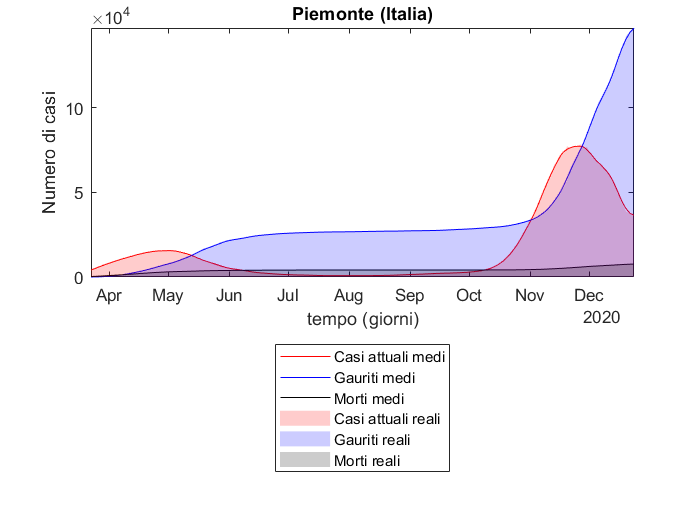

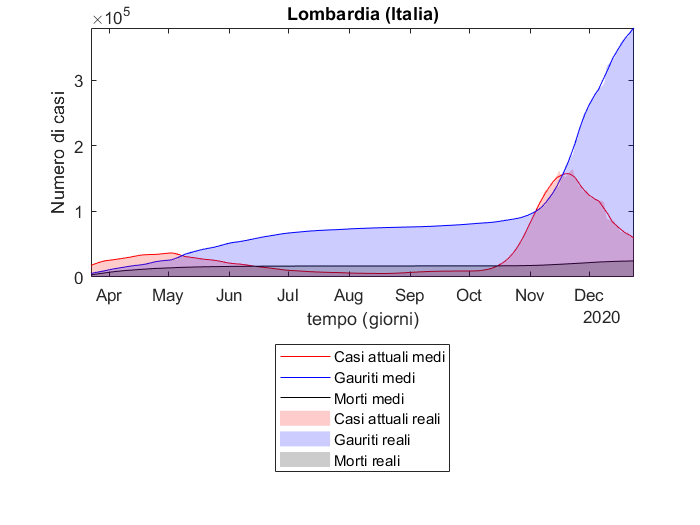

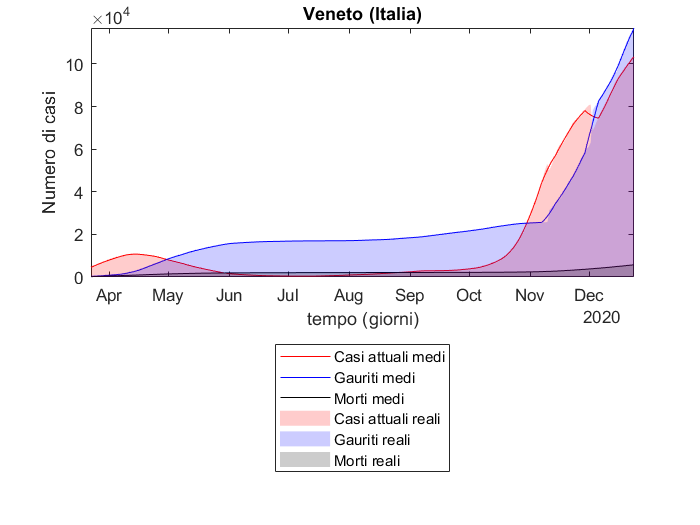

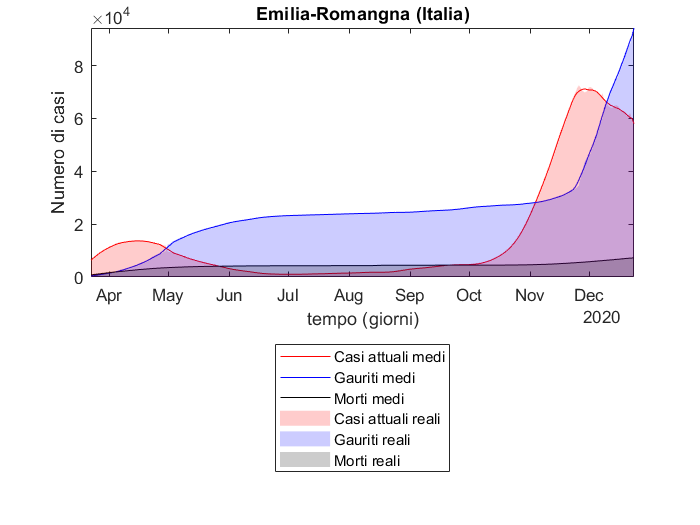

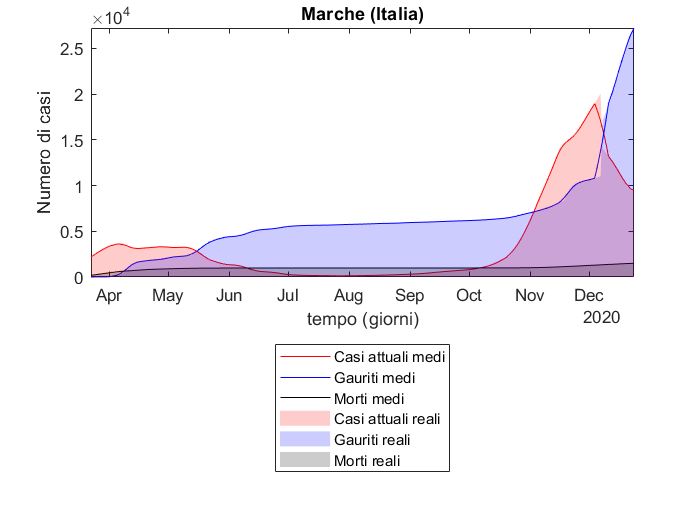

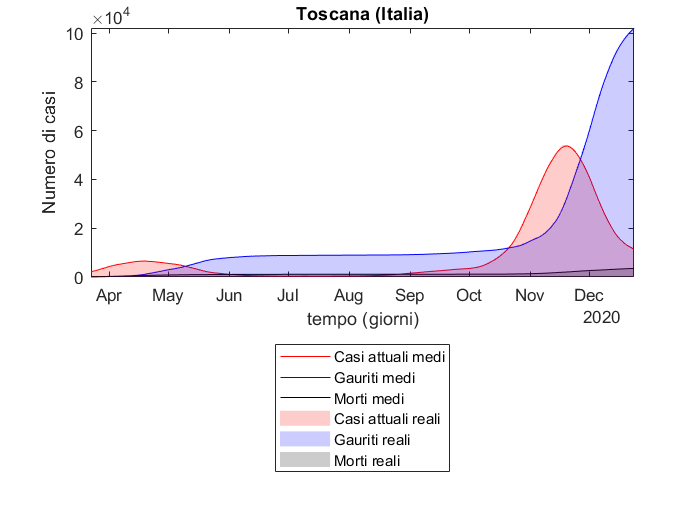

for indR=1:numRegioni
    figure
    semilogy(time(periodoAnalisi),Qmedia(periodoAnalisi,indR),'r',time(periodoAnalisi),Rmedia(periodoAnalisi,indR),'b',time(periodoAnalisi),Dmedia(periodoAnalisi,indR),'k');
    Y=[Q(periodoAnalisi,indR)';R(periodoAnalisi,indR)';D(periodoAnalisi,indR)'];
    hold on
    a=area(time(periodoAnalisi),Q(periodoAnalisi,indR));
    a.FaceAlpha=0.2;
    a.FaceColor='r';
    a.EdgeColor='none';
    a=area(time(periodoAnalisi),R(periodoAnalisi,indR));
    a.FaceAlpha=0.2;
    a.FaceColor='b';
    a.EdgeColor='none';
    a=area(time(periodoAnalisi),D(periodoAnalisi,indR));
    a.FaceAlpha=0.2;
    a.FaceColor='k';
    a.EdgeColor='none';
    ylabel('Numero di casi')
    xlabel('tempo (giorni)')
    title([regioni{indR},' (Italia)']);
    leg = {'Casi attuali medi','Gauriti medi','Morti medi','Casi attuali reali','Gauriti reali','Morti reali'};
    legend(leg{:},'location','southoutside')
    set(gcf,'color','w')
    axis tight
    set(gca,'yscale','lin')
    hold off
end

## ***Periodo 1: 22-03-2020 / 26-04-2020***

Cominciamo fittando i modelli SQRD, SIQRDP e SEIQRDP nel periodo che va dal 22-03-2020 al 26-04-2020.  In quest'arco temporale, essendo stato proclamato lockdown totale, il termine diffusivo è stato settato a 0.

time = unique(datetime(datestr(datenum(dataset{1}.data,'yyyy-mm-DDThh:MM:ss'))));
% If the number of confirmed Confirmed cases is small, it is difficult to know whether
% the quarantine has been rigorously applied or not. In addition, this
% suggests that the number of infectious is much larger than the number of
% confirmed cases
tStart = datetime(2020,03,22);
tEnd = datetime(2020,04,26);
indT = find(time>=tStart & time <=tEnd);

Per poter fittare modello è necessario definire le condizioni iniziali relative ai parametri

dataItalia = readtable("dati-regioni-xlsx/italia.xlsx");
timeItalia = unique(datetime(datestr(datenum(dataItalia.data,'yyyy-mm-DDThh:MM:ss'))));
x0=[1.0*ones(1,6)]; %beta
load alpha.mat
load omega.mat
%x0=[x0  0.4 0.7 0.4 0.8 0.5 0.5]; %alpha
%x0=[x0  0.1 0.5 0.3 0.2 0.5 0.5]; %omega
x0=[x0  alpha(1,:)]; %alpha valori reali
x0=[x0  omega(1,:)]; %omega valori reali
x0=[x0 1/5*ones(1,6)]; %lambda -> periodo medio di incubazione è 5 giorni.
x0=[x0 0.5*ones(1,6)]; %delta
x0=[x0 1/11*ones(1,6)]; %gammaR
% x0=[x0 dataItalia.deceduti(end)/(dataItalia.totale_casi(end)*numel(timeItalia))*ones(1,6)]; %gammaD

e relative alle ODE del sistema che definisce il modello. Le condizioni iniziali dipenderanno dalla regione in considerazione.  In particolare:

- I valori iniziali di $\beta$,$\lambda$, $\delta$, $E_0$, $P_0$ e $I_0$ sono stati presi dal sito [https://it.mathworks.com/matlabcentral/fileexchange/74545-generalized-seir-epidemic-model-fitting-and-computation](https://it.mathworks.com/matlabcentral/fileexchange/74545-generalized-seir-epidemic-model-fitting-and-computation) di cui il codice segue l'impostazione e sono identici per ogni regione;

- $Q_0,R_0,D_0$ sono i valori al giorno iniziale repereiti sul bollettino nazionale per ogni regione;

- $S_0 = N-\left(E_0+I_0+Q_0+R_0+D_0+P_0\right)$;

- Il valore inziale di $\omega
$ e $\alpha$ sono stati settati al valore definiti mediante tuning sia per il modello SEIQRDP sia per il SIQRDP, dipendono dalla regione e sono reperibili al nostro indirizzo git hub [https://github.com/gioanat/progettoMB](https://github.com/gioanat/progettoMB);  

- Il numero di abitanti $N_j $ di ciascuna regione è stato preso dal sito dell'ISTAT [http://dati.istat.it/Index.aspx?DataSetCode=DCIS_POPRES1#](http://dati.istat.it/Index.aspx?DataSetCode=DCIS_POPRES1#); 

- Il tasso di guarigione $\gamma_R$ iniziale viene settato a 1/11 in ogni regione, ovvero l'inverso del tempo medio (in giorni) della permanenza dei sintomi secondo [https://www.humanitas.it/news/27211-covid-19-quali-sono-i-tempi-di-incubazione](https://www.humanitas.it/news/27211-covid-19-quali-sono-i-tempi-di-incubazione);

- il valore iniziale del tasso di morte $\left(\gamma_D\right)_j$ è stato valutato come rapporto tra la variazione dei deceduti rispetto al giorno precedente e gli attuali positivi della regione $j$-esima.

% tasso di morte
rateD=[];
rateDmedia=[];
for indR=1:6
    rateD(:,indR) = (diff(D(:,indR))./diff(datenum(time-time(1))))./Q(2:end,indR);
    rateDmedia(:,indR) = (diff(Dmedia(:,indR))./diff(datenum(time-time(1))))./Qmedia(2:end,indR);
    %rateD(:,indR) = cumsum(D(:,indR))./(cumsum(Tot(:,indR)).*datenum(time-time(1)));
    %rateDmedia(:,indR) = cumsum(Dmedia(:,indR))./(cumsum(Totmedia(:,indR)).*datenum(time-time(1)));
end
format short
rateD=rateD(periodoAnalisi(1),:)

rateD =     0.0071    0.0169    0.0046    0.0105    0.0081    0.0078


rateDmedia=rateDmedia(periodoAnalisi(1),:)

rateDmedia =     0.0086    0.0204    0.0049    0.0131    0.0119    0.0073


%rateD=rateD(periodoAnalisi,:);
%rateD(1,:)
%rateDmedia=rateDmedia(periodoAnalisi,:);
%rateDmedia(1,:)

popolazione=[4.311e6 10.028e6 4.879e6 4.464e6 1.513e6 3.693e6]; % dati istat

L=zeros(6,6);
indexPeriod=1;
flag=0;
% Initial conditions
dt = 1/24; % time step
temp=time(indT);
timeA=datetime(temp(1), 'Locale', 'en_US'):dt:datetime(temp(end), 'Locale', 'en_US');
N = numel(timeA);
t = [0:N-1].*dt;

firstdate=find(time>=tStart & time<=tStart+datenum(1));
x0 = [x0 rateD(1,:)]; %gammaD
I0 = 0.2*Q(firstdate,:); % Initial number of infectious cases. Unknown but unlikely to be zero.
E0 = Q(firstdate,:); % Initial number of exposed cases. Unknown but unlikely to be zero.
Q0 = Q(firstdate,:);
R0 = R(firstdate,:);
D0 = D(firstdate,:);
P0 = zeros(1,6);
S0 = popolazione-E0-I0-Q(firstdate,:)-R(firstdate,:)-D(firstdate,:)-P0;

[SEIQRDP_onNetwork{indexPeriod}.parametriR,SEIQRDP_onNetwork{indexPeriod}.resnormR,SEIQRDP_onNetwork{indexPeriod}.residualR] = fittingSEIQRDP_onNetwork(Q(indT,:),R(indT,:),D(indT,:),popolazione,S0,P0,E0,I0,Q0,R0,D0,L,time(indT),x0,flag,'Display','off','dt',0.1);
SEIQRDP{indexPeriod}.YR = simulatedSEIQRDP_onNetwork(popolazione,S0,P0,E0,I0,Q0,R0,D0,Q(indT,:),R(indT,:),D(indT,:),L,SEIQRDP_onNetwork{indexPeriod}.parametriR,N,t,flag);
%plotSimulated(timeA,squeeze(SEIQRDP{indexPeriod}.YR(5,:,:)),squeeze(SEIQRDP{indexPeriod}.YR(6,:,:)),squeeze(SEIQRDP{indexPeriod}.YR(7,:,:)),time(indT),Tot(indT,:),Q(indT,:),R(indT,:),D(indT,:),'Dati reali: SEIQRDP on Network -',regioni)
x0(7:18)=[alpha(3,:) omega(3,:)];
%x0(7:18)=[0.1 1 1 0.5 0.5 0.5 0.8 0.9 0.5 0.7 0.5 0.5];
[SIQRDP_onNetwork{indexPeriod}.parametriR,SIQRDP_onNetwork{indexPeriod}.resnormR,SIQRDP_onNetwork{indexPeriod}.residualR] = fittingSIQRDP_onNetwork(Q(indT,:),R(indT,:),D(indT,:),popolazione,S0,P0,I0,Q0,R0,D0,L,time(indT),x0([1:18 25:end]),flag,'Display','off','dt',0.1);
SIQRDP{indexPeriod}.YR= simulatedSIQRDP_onNetwork(popolazione,S0,P0,I0,Q0,R0,D0,Q(indT,:),R(indT,:),D(indT,:),L,SIQRDP_onNetwork{indexPeriod}.parametriR,N,t,flag);
%plotSimulated(timeA,squeeze(SIQRDP{indexPeriod}.YR(4,:,:)),squeeze(SIQRDP{indexPeriod}.YR(5,:,:)),squeeze(SIQRDP{indexPeriod}.YR(6,:,:)),time(indT),Tot(indT,:),Q(indT,:),R(indT,:),D(indT,:),'Dati reali: SIQRDP on Network -',regioni)

[SQRD_onNetwork{indexPeriod}.parametriR,SQRD_onNetwork{indexPeriod}.resnormR,SQRD_onNetwork{indexPeriod}.residualR] = fittingSQRD_onNetwork(Q(indT,:),R(indT,:),D(indT,:),popolazione,S0,Q0,R0,D0,L,time(indT),x0([1:6 31:end]),flag,'Display','off','dt',0.1);
SQRD{indexPeriod}.YR= simulatedSQRD_onNetwork(popolazione,S0,Q0,R0,D0,Q(indT,:),R(indT,:),D(indT,:),L,SQRD_onNetwork{indexPeriod}.parametriR,N,t,flag);
%plotSimulated(timeA,squeeze(SQRD{indexPeriod}.YR(2,:,:)),squeeze(SQRD{indexPeriod}.YR(3,:,:)),squeeze(SQRD{indexPeriod}.YR(4,:,:)),time(indT),Tot(indT,:),Q(indT,:),R(indT,:),D(indT,:),'Dati reali: SQRD on Network -',regioni)

x0(7:18)=[alpha(2,:) omega(2,:)];
%x0(7:18)=[0.4 0.7 0.4 0.8 0.5 0.5 0.1 0.5 0.3 0.2 0.5 0.5];
x0(37:42)=rateDmedia(1,:);
I0 = 0.2*Qmedia(firstdate,:); % Initial number of infectious cases. Unknown but unlikely to be zero.
E0 = Qmedia(firstdate,:); % Initial number of exposed cases. Unknown but unlikely to be zero.
P0 = zeros(1,6);
Q0 = Qmedia(firstdate,:);
R0 = Rmedia(firstdate,:);
D0 = Dmedia(firstdate,:);
S0 = popolazione-E0-I0-Qmedia(firstdate,:)-Rmedia(firstdate,:)-Dmedia(firstdate,:)-P0;
[SEIQRDP_onNetwork{indexPeriod}.parametriM,SEIQRDP_onNetwork{indexPeriod}.resnormM,SEIQRDP_onNetwork{indexPeriod}.residualM] = fittingSEIQRDP_onNetwork(Qmedia(indT,:),Rmedia(indT,:),Dmedia(indT,:),popolazione,S0,P0,E0,I0,Q0,R0,D0,L,time(indT),x0,flag,'Display','off','dt',0.1);
SEIQRDP{indexPeriod}.YM = simulatedSEIQRDP_onNetwork(popolazione,S0,P0,E0,I0,Q0,R0,D0,Qmedia(indT,:),Rmedia(indT,:),Dmedia(indT,:),L,SEIQRDP_onNetwork{indexPeriod}.parametriM,N,t,flag);
%plotSimulated(timeA,squeeze(SEIQRDP{indexPeriod}.YM(5,:,:)),squeeze(SEIQRDP{indexPeriod}.YM(6,:,:)),squeeze(SEIQRDP{indexPeriod}.YM(7,:,:)),time(indT),Totmedia(indT,:),Qmedia(indT,:),Rmedia(indT,:),Dmedia(indT,:),'Dati in media mobile: SEIQRDP on Network -',regioni)

%x0(7:18)=[0.1 1 1 0.5 0.5 0.5 0.8 0.9 0.5 0.7 0.5 0.5];
x0(7:18)=[alpha(4,:) omega(4,:)];
[SIQRDP_onNetwork{indexPeriod}.parametriM,SIQRDP_onNetwork{indexPeriod}.resnormM,SIQRDP_onNetwork{indexPeriod}.residualM] = fittingSIQRDP_onNetwork(Qmedia(indT,:),Rmedia(indT,:),Dmedia(indT,:),popolazione,S0,P0,I0,Q0,R0,D0,L,time(indT),x0([1:18 25:end]),flag,'Display','off','dt',0.1);
SIQRDP{indexPeriod}.YM= simulatedSIQRDP_onNetwork(popolazione,S0,P0,I0,Q0,R0,D0,Qmedia(indT,:),Rmedia(indT,:),Dmedia(indT,:),L,SIQRDP_onNetwork{indexPeriod}.parametriM,N,t,flag);
%plotSimulated(timeA,squeeze(SIQRDP{indexPeriod}.YM(4,:,:)),squeeze(SIQRDP{indexPeriod}.YM(5,:,:)),squeeze(SIQRDP{indexPeriod}.YM(6,:,:)),time(indT),Totmedia(indT,:),Qmedia(indT,:),Rmedia(indT,:),Dmedia(indT,:),'Dati in media mobile: SIQRDP on Network -',regioni)

[SQRD_onNetwork{indexPeriod}.parametriM,SQRD_onNetwork{indexPeriod}.resnormM,SQRD_onNetwork{indexPeriod}.residualM] = fittingSQRD_onNetwork(Qmedia(indT,:),Rmedia(indT,:),Dmedia(indT,:),popolazione,S0,Q0,R0,D0,L,time(indT),x0([1:6 31:end]),flag,'Display','off','dt',0.1);
SQRD{indexPeriod}.YM= simulatedSQRD_onNetwork(popolazione,S0,Q0,R0,D0,Qmedia(indT,:),Rmedia(indT,:),Dmedia(indT,:),L,SQRD_onNetwork{indexPeriod}.parametriM,N,t,flag);
%plotSimulated(timeA,squeeze(SQRD{indexPeriod}.YM(2,:,:)),squeeze(SQRD{indexPeriod}.YM(3,:,:)),squeeze(SQRD{indexPeriod}.YM(4,:,:)),time(indT),Totmedia(indT,:),Qmedia(indT,:),Rmedia(indT,:),Dmedia(indT,:),'Dati in media mobile: SQRD on Network -',regioni)

metodi={'SEIQRDP','SIQRDP','SQRD'};
cnames = {'Metodo','Norma residui ^2 (reali)','Norma residui ^2 (mediati)'};
table_erroriMedi_onNetwork{indexPeriod}=table(metodi',[SEIQRDP_onNetwork{indexPeriod}.resnormR SIQRDP_onNetwork{indexPeriod}.resnormR SQRD_onNetwork{indexPeriod}.resnormR]',[SEIQRDP_onNetwork{indexPeriod}.resnormM,SIQRDP_onNetwork{indexPeriod}.resnormM, SQRD_onNetwork{indexPeriod}.resnormM]','VariableNames',cnames);
table_erroriMedi_onNetwork{indexPeriod}

ans = 3×3 table
      Metodo       Norma residui ^2 (reali)    Norma residui ^2 (mediati)
    ___________    ________________________    __________________________

    {'SEIQRDP'}           1.2095e+08                   1.5486e+08        
    {'SIQRDP' }           1.2493e+08                   1.2043e+08        
    {'SQRD'   }           8.1253e+08                   8.1402e+08        


Osserviamo meglio la differenza nel fittaggio di dati mediati e reali.

for indR=1:6
   errQR(indR)=mean(abs(SEIQRDP_onNetwork{indexPeriod}.residualR(1:length(indT),indR)));
   errQM(indR)=mean(abs(SEIQRDP_onNetwork{indexPeriod}.residualM(1:length(indT),indR)));
   errRR(indR)=mean(abs(SEIQRDP_onNetwork{indexPeriod}.residualR(length(indT)+2:2*length(indT),indR)));
   errRM(indR)=mean(abs(SEIQRDP_onNetwork{indexPeriod}.residualM(length(indT)+2:2*length(indT),indR)));
   errDR(indR)=mean(abs(SEIQRDP_onNetwork{indexPeriod}.residualR(2*length(indT)+2:3*length(indT),indR)));
   errDM(indR)=mean(abs(SEIQRDP_onNetwork{indexPeriod}.residualM(2*length(indT)+2:3*length(indT),indR)));
end
cnames = {'Nome regione','Media |residui| su Q','Media |residui| su Qmedia','Media |residui| su R','Media |residui| su Rmedia','Media |residui| su D','Media |residui| su Dmedia'};
format short
table_erroriMedi_SEIQRDP_onNetwork{indexPeriod}=table(regioni',errQR',errQM',errRR',errRM',errDR',errDM','VariableNames',cnames);
table_erroriMedi_SEIQRDP_onNetwork{indexPeriod}

ans = 6×7 table
       Nome regione        Media |residui| su Q    Media |residui| su Qmedia    Media |residui| su R    Media |residui| su Rmedia    Media |residui| su D    Media |residui| su Dmedia
    ___________________    ____________________    _________________________    ____________________    _________________________    ____________________    _________________________

    {'Piemonte'       }           99.769                    86.968                      327.1                    325.79                     101.48                    123.95          
    {'Lombardia'      }           539.75                    645.36                     796.98                    906.64                     931.64                    961.92          
    {'Veneto'

for indR=1:6
   errQR(indR)=mean(abs(SIQRDP_onNetwork{indexPeriod}.residualR(1:length(indT),indR)));
   errQM(indR)=mean(abs(SIQRDP_onNetwork{indexPeriod}.residualM(1:length(indT),indR)));
   errRR(indR)=mean(abs(SIQRDP_onNetwork{indexPeriod}.residualR(length(indT)+2:2*length(indT),indR)));
   errRM(indR)=mean(abs(SIQRDP_onNetwork{indexPeriod}.residualM(length(indT)+2:2*length(indT),indR)));
   errDR(indR)=mean(abs(SIQRDP_onNetwork{indexPeriod}.residualR(2*length(indT)+2:3*length(indT),indR)));
   errDM(indR)=mean(abs(SIQRDP_onNetwork{indexPeriod}.residualM(2*length(indT)+2:3*length(indT),indR)));
end
cnames = {'Nome regione','Media |residui| su Q','Media |residui| su Qmedia','Media |residui| su R','Media |residui| su Rmedia','Media |residui| su D','Media |residui| su Dmedia'};
format short
table_erroriMedi_SIQRDP_onNetwork{indexPeriod}=table(regioni',errQR',errQM',errRR',errRM',errDR',errDM','VariableNames',cnames);
table_erroriMedi_SIQRDP_onNetwork{indexPeriod}

ans = 6×7 table
       Nome regione        Media |residui| su Q    Media |residui| su Qmedia    Media |residui| su R    Media |residui| su Rmedia    Media |residui| su D    Media |residui| su Dmedia
    ___________________    ____________________    _________________________    ____________________    _________________________    ____________________    _________________________

    {'Piemonte'       }           98.181                     68.67                     328.09                    311.44                     101.23                    100.07          
    {'Lombardia'      }            561.4                    477.82                     814.38                    931.23                     941.71                    978.75          
    {'Veneto'

for indR=1:6
   errQR(indR)=mean(abs(SQRD_onNetwork{indexPeriod}.residualR(1:length(indT),indR)));
   errQM(indR)=mean(abs(SQRD_onNetwork{indexPeriod}.residualM(1:length(indT),indR)));
   errRR(indR)=mean(abs(SQRD_onNetwork{indexPeriod}.residualR(length(indT)+2:2*length(indT),indR)));
   errRM(indR)=mean(abs(SQRD_onNetwork{indexPeriod}.residualM(length(indT)+2:2*length(indT),indR)));
   errDR(indR)=mean(abs(SQRD_onNetwork{indexPeriod}.residualR(2*length(indT)+2:3*length(indT),indR)));
   errDM(indR)=mean(abs(SQRD_onNetwork{indexPeriod}.residualM(2*length(indT)+2:3*length(indT),indR)));
end
cnames = {'Nome regione','Media |residui| su Q','Media |residui| su Qmedia','Media |residui| su R','Media |residui| su Rmedia','Media |residui| su D','Media |residui| su Dmedia'};
format short
table_erroriMedi_SQRD_onNetwork{indexPeriod}=table(regioni',errQR',errQM',errRR',errRM',errDR',errDM','VariableNames',cnames);
table_erroriMedi_SQRD_onNetwork{indexPeriod}

ans = 6×7 table
       Nome regione        Media |residui| su Q    Media |residui| su Qmedia    Media |residui| su R    Media |residui| su Rmedia    Media |residui| su D    Media |residui| su Dmedia
    ___________________    ____________________    _________________________    ____________________    _________________________    ____________________    _________________________

    {'Piemonte'       }             1549                    1547.4                     258.94                    239.45                     142.74                    141.17          
    {'Lombardia'      }           2310.6                    2333.4                     922.58                    1049.3                     1029.2                    1066.9          
    {'Veneto'

I parametri del modelli fittati sui dati in media mobile:

cnames = {'Nome regione','beta','alpha','omega','lambda','delta','gammaR','gammaD'};
tableSEIQRDP_onNetwork{indexPeriod}=table(regioni',SEIQRDP_onNetwork{indexPeriod}.parametriM(1:6)',SEIQRDP_onNetwork{indexPeriod}.parametriM(7:12)',SEIQRDP_onNetwork{indexPeriod}.parametriM(13:18)',SEIQRDP_onNetwork{indexPeriod}.parametriM(19:24)',SEIQRDP_onNetwork{indexPeriod}.parametriM(25:30)',SEIQRDP_onNetwork{indexPeriod}.parametriM(31:36)',SEIQRDP_onNetwork{indexPeriod}.parametriM(37:42)','VariableNames',cnames);
tableSEIQRDP_onNetwork{indexPeriod}

ans = 6×8 table
       Nome regione         beta       alpha      omega       lambda      delta      gammaR      gammaD  
    ___________________    _______    _______    ________    ________    _______    ________    _________

    {'Piemonte'       }    0.89105    0.18168     0.20704     0.14095    0.50145    0.015518    0.0082768
    {'Lombardia'      }    0.77843    0.50278     0.52555    0.086121    0.46736    0.019798     0.011995
    {'Veneto'         }    0.84918    0.21712    0.098267     0.12712    0.49971    0.017322     0.005841
    {'Emilia-Romangna'}     0.8376    0.27273     0.17737      0.1222    0.55548    0.017697    0.0080811
    {'Marche'         }     0.8166          1      0.3727    0.085144    0.

cnames = {'Nome regione','beta','alpha','omega','delta','gammaR','gammaD'};
tableSIQRDP_onNetwork{indexPeriod}=table(regioni',SIQRDP_onNetwork{indexPeriod}.parametriM(1:6)',SIQRDP_onNetwork{indexPeriod}.parametriM(7:12)',SIQRDP_onNetwork{indexPeriod}.parametriM(13:18)',SIQRDP_onNetwork{indexPeriod}.parametriM(19:24)',SIQRDP_onNetwork{indexPeriod}.parametriM(25:30)',SIQRDP_onNetwork{indexPeriod}.parametriM(31:36)','VariableNames',cnames);
tableSIQRDP_onNetwork{indexPeriod}

ans = 6×7 table
       Nome regione         beta       alpha       omega       delta      gammaR      gammaD  
    ___________________    _______    ________    ________    _______    ________    _________

    {'Piemonte'       }    0.69967     0.11953     0.34686    0.52275    0.014978    0.0075247
    {'Lombardia'      }    0.50794     0.25758     0.99996    0.40833    0.020017     0.012157
    {'Veneto'         }      0.545    0.085861    0.065282    0.33548    0.016502    0.0039133
    {'Emilia-Romangna'}    0.64025     0.11047     0.24865     0.4939    0.017036    0.0070724
    {'Marche'         }    0.87352     0.83874     0.54157    0.40511    0.017844    0.0072407
    {'Toscana'        }    0.82097     0.25226     0.36645    0.52804    0.00875

cnames = {'Nome regione','beta','gammaR','gammaD'};
tableSQRD_onNetwork{indexPeriod}=table(regioni',SQRD_onNetwork{indexPeriod}.parametriM(1:6)',SQRD_onNetwork{indexPeriod}.parametriM(7:12)',SQRD_onNetwork{indexPeriod}.parametriM(13:18)','VariableNames',cnames);
tableSQRD_onNetwork{indexPeriod}

ans = 6×4 table
       Nome regione          beta       gammaR      gammaD  
    ___________________    ________    ________    _________

    {'Piemonte'       }    0.071252    0.017655    0.0088097
    {'Lombardia'      }    0.058607    0.021739     0.013181
    {'Veneto'         }    0.055214    0.019832     0.004606
    {'Emilia-Romangna'}    0.056887    0.020451    0.0083897
    {'Marche'         }    0.045895    0.020734    0.0083847
    {'Toscana'        }    0.056152     0.01093    0.0050712


## ***Periodo 2: 27-04-2020 / 11-06-2020***

In quest'arco temporale, sono stati concessi maggiori spostamenti all'interno delle regioni ed è stata introdotta la possibilità di spostarsi tra regioni differenti anche per fare rientro nel proprio comune di residenza e/o domicilio.

Le condizioni iniziale per il problema di ottimizzazione relative ai parametri delle singole regioni sono date dai relativi parametri del periodo precedentemente analizzato.

Per quanto riguarda, invece, le condizioni iniziali per i parametri $\epsilon_S$ ed $\epsilon_I$ essi sono ottenuti mediante tuning.

Per quanto riguarda la costruzione della matrice $L$, la sua entrata $(i,j)$ è stata settata a un valore costante che rappresenta il flusso unitario giornaliero che si dirige da $j$ a $i$ tramite il tratto autostradale preso come riferimento. Tali dati sono stati reperiti al link [https://www.aiscat.it/pubblicazioni/downloads/trim_1-2_2019.pdf](https://www.aiscat.it/pubblicazioni/downloads/trim_1-2_2019.pdf)  (non più esistente a causa del rifacimento del sito AISCAT ma comunque reperibili nella nostra repository GitHub) ed essi rappresentano valori medi giornalieri relativi al 2 trimestre 2019 per il tratto autostradale relativo (associazione 1 veicolo-1 persona) e sono poi stati moltiplicati per 0.35, in quanto come emerge da [https://www.aiscat.it/pubblicazioni/downloads/AISCAT-mensile_05-2020.pdf](https://www.aiscat.it/pubblicazioni/downloads/AISCAT-mensile_05-2020.pdf)  (non più esistente a causa del rifacimento del sito AISCAT ma comunque reperibili nella nostra repository git hub), nel mese di maggio 2020 vi è stata una riduzione media del 65% rispetto lo stesso mese dell'anno precedente.

tStart = datetime(2020,04,27);
tEnd = datetime(2020,06,11);
indT = find(time>=tStart & time <=tEnd);
dt = 1/24; % time step
temp=time(indT);
timeA=datetime(temp(1), 'Locale', 'en_US'):dt:datetime(temp(end), 'Locale', 'en_US');
N = numel(timeA);
t = [0:N-1].*dt;

L=0.35*46*[0 117e03/popolazione(2) 0 108e03/popolazione(4) 0 0;
    117e03/popolazione(1) 0 302e03/popolazione(3) 300e03/popolazione(4) 0 0;
    0 302e03/popolazione(2) 0 136e03/popolazione(4) 0 0;
    108e03/popolazione(1) 300e03/popolazione(2) 136e03/popolazione(3) 0 311e03/popolazione(5)  116e03/popolazione(6);
    0 0 0 311e03/popolazione(4) 0 0;
    0 0 0 116e03/popolazione(4) 0 0];
Ldiag=diag(sum(L,1));
L=L-Ldiag;
indexPeriod=2;
flag=1; % diffusion yes
% Initial conditions

firstdate=find(time>=tStart & time<=tStart+datenum(1));
load epsilonI.mat
load epsilonS.mat
x0=[SEIQRDP_onNetwork{indexPeriod-1}.parametriR epsilonS(1) epsilonI(1)]; 
%x0=[SEIQRDP_onNetwork{indexPeriod-1}.parametriR 0.8 0.2]; 

I0 = squeeze(SEIQRDP{indexPeriod-1}.YR(4,:,end)); 
E0 = squeeze(SEIQRDP{indexPeriod-1}.YR(3,:,end)); 
P0 = squeeze(SEIQRDP{indexPeriod-1}.YR(2,:,end));
S0 = squeeze(SEIQRDP{indexPeriod-1}.YR(1,:,end));
Q0 = squeeze(SEIQRDP{indexPeriod-1}.YR(5,:,end));
R0 = squeeze(SEIQRDP{indexPeriod-1}.YR(6,:,end));
D0 = squeeze(SEIQRDP{indexPeriod-1}.YR(7,:,end));
[SEIQRDP_onNetwork{indexPeriod}.parametriR,SEIQRDP_onNetwork{indexPeriod}.resnormR,SEIQRDP_onNetwork{indexPeriod}.residualR] = fittingSEIQRDP_onNetwork(Q(indT,:),R(indT,:),D(indT,:),popolazione,S0,P0,E0,I0,Q0,R0,D0,L,time(indT),x0,flag,'Display','off','dt',0.1);
SEIQRDP{indexPeriod}.YR = simulatedSEIQRDP_onNetwork(popolazione,S0,P0,E0,I0,Q0,R0,D0,Q(indT,:),R(indT,:),D(indT,:),L,SEIQRDP_onNetwork{indexPeriod}.parametriR,N,t,flag);
%plotSimulated(timeA,squeeze(SEIQRDP{indexPeriod}.YR(5,:,:)),squeeze(SEIQRDP{indexPeriod}.YR(6,:,:)),squeeze(SEIQRDP{indexPeriod}.YR(7,:,:)),time(indT),Tot(indT,:),Q(indT,:),R(indT,:),D(indT,:),'Dati reali: SEIQRDP on Network -',regioni)

I0 = squeeze(SIQRDP{indexPeriod-1}.YR(3,:,end)); % Initial number of infectious cases. Unknown but unlikely to be zero.
P0 = squeeze(SIQRDP{indexPeriod-1}.YR(2,:,end));
S0 = squeeze(SIQRDP{indexPeriod-1}.YR(1,:,end));
Q0 = squeeze(SIQRDP{indexPeriod-1}.YR(4,:,end));
R0 = squeeze(SIQRDP{indexPeriod-1}.YR(5,:,end));
D0 = squeeze(SIQRDP{indexPeriod-1}.YR(6,:,end));

x0=[SIQRDP_onNetwork{indexPeriod-1}.parametriR epsilonS(3) epsilonI(3)]; 
%x0=[SIQRDP_onNetwork{indexPeriod-1}.parametriR 0.1 0.001]; %% DA MODIFICARE
[SIQRDP_onNetwork{indexPeriod}.parametriR,SIQRDP_onNetwork{indexPeriod}.resnormR,SIQRDP_onNetwork{indexPeriod}.residualR] = fittingSIQRDP_onNetwork(Q(indT,:),R(indT,:),D(indT,:),popolazione,S0,P0,I0,Q0,R0,D0,L,time(indT),x0,flag,'Display','off','dt',0.1);
SIQRDP{indexPeriod}.YR= simulatedSIQRDP_onNetwork(popolazione,S0,P0,I0,Q0,R0,D0,Q(indT,:),R(indT,:),D(indT,:),L,SIQRDP_onNetwork{indexPeriod}.parametriR,N,t,flag);
%plotSimulated(timeA,squeeze(SIQRDP{indexPeriod}.YR(4,:,:)),squeeze(SIQRDP{indexPeriod}.YR(5,:,:)),squeeze(SIQRDP{indexPeriod}.YR(6,:,:)),time(indT),Tot(indT,:),Q(indT,:),R(indT,:),D(indT,:),'Dati reali: SIQRDP on Network -',regioni)

S0 = squeeze(SQRD{indexPeriod-1}.YR(1,:,end));
Q0 = squeeze(SQRD{indexPeriod-1}.YR(2,:,end));
R0 = squeeze(SQRD{indexPeriod-1}.YR(3,:,end));
D0 = squeeze(SQRD{indexPeriod-1}.YR(4,:,end));

x0=[SQRD_onNetwork{indexPeriod-1}.parametriR epsilonS(5)];
%x0=[SQRD_onNetwork{indexPeriod-1}.parametriR 0.1];
[SQRD_onNetwork{indexPeriod}.parametriR,SQRD_onNetwork{indexPeriod}.resnormR,SQRD_onNetwork{indexPeriod}.residualR] = fittingSQRD_onNetwork(Q(indT,:),R(indT,:),D(indT,:),popolazione,S0,Q0,R0,D0,L,time(indT),x0,flag,'Display','off','dt',0.1);
SQRD{indexPeriod}.YR= simulatedSQRD_onNetwork(popolazione,S0,Q0,R0,I0,Q(indT,:),R(indT,:),D(indT,:),L,SQRD_onNetwork{indexPeriod}.parametriR,N,t,flag);
%plotSimulated(timeA,squeeze(SQRD{indexPeriod}.YR(2,:,:)),squeeze(SQRD{indexPeriod}.YR(3,:,:)),squeeze(SQRD{indexPeriod}.YR(4,:,:)),time(indT),Tot(indT,:),Q(indT,:),R(indT,:),D(indT,:),'Dati reali: SQRD on Network -',regioni)

S0 = squeeze(SEIQRDP{indexPeriod-1}.YM(1,:,end));
P0 = squeeze(SEIQRDP{indexPeriod-1}.YM(2,:,end));
E0 = squeeze(SEIQRDP{indexPeriod-1}.YM(3,:,end));
I0 = squeeze(SEIQRDP{indexPeriod-1}.YM(4,:,end));
Q0 = squeeze(SEIQRDP{indexPeriod-1}.YM(5,:,end));
R0 = squeeze(SEIQRDP{indexPeriod-1}.YM(6,:,end));
D0 = squeeze(SEIQRDP{indexPeriod-1}.YM(7,:,end));
x0=[SEIQRDP_onNetwork{indexPeriod-1}.parametriM epsilonS(2) epsilonI(2)]; %% DA MODIFICARE
%x0=[SEIQRDP_onNetwork{indexPeriod-1}.parametriM 0.8 0.2]; %% DA MODIFICARE
%x0=[SEIQRDP_onNetwork{indexPeriod-1}.parametriM];
[SEIQRDP_onNetwork{indexPeriod}.parametriM,SEIQRDP_onNetwork{indexPeriod}.resnormM,SEIQRDP_onNetwork{indexPeriod}.residualM] = fittingSEIQRDP_onNetwork(Qmedia(indT,:),Rmedia(indT,:),Dmedia(indT,:),popolazione,S0,P0,E0,I0,Q0,R0,D0,L,time(indT),x0,flag,'Display','off','dt',0.1);
SEIQRDP{indexPeriod}.YM = simulatedSEIQRDP_onNetwork(popolazione,S0,P0,E0,I0,Q0,R0,D0,Qmedia(indT,:),Rmedia(indT,:),Dmedia(indT,:),L,SEIQRDP_onNetwork{indexPeriod}.parametriM,N,t,flag);
%plotSimulated(timeA,squeeze(SEIQRDP{indexPeriod}.YM(5,:,:)),squeeze(SEIQRDP{indexPeriod}.YM(6,:,:)),squeeze(SEIQRDP{indexPeriod}.YM(7,:,:)),time(indT),Totmedia(indT,:),Qmedia(indT,:),Rmedia(indT,:),Dmedia(indT,:),'Dati in media mobile: SEIQRDP on Network -',regioni)

x0=[SIQRDP_onNetwork{indexPeriod-1}.parametriM epsilonS(4) epsilonI(4)]; %% DA MODIFICARE
%x0=[SIQRDP_onNetwork{indexPeriod-1}.parametriM 0.1 0.001]; %% DA MODIFICARE
S0 = squeeze(SIQRDP{indexPeriod-1}.YM(1,:,end));
P0 = squeeze(SIQRDP{indexPeriod-1}.YM(2,:,end));
I0 = squeeze(SIQRDP{indexPeriod-1}.YM(3,:,end));
Q0 = squeeze(SIQRDP{indexPeriod-1}.YM(4,:,end));
R0 = squeeze(SIQRDP{indexPeriod-1}.YM(5,:,end));
D0 = squeeze(SIQRDP{indexPeriod-1}.YM(6,:,end));

[SIQRDP_onNetwork{indexPeriod}.parametriM,SIQRDP_onNetwork{indexPeriod}.resnormM,SIQRDP_onNetwork{indexPeriod}.residualM] = fittingSIQRDP_onNetwork(Qmedia(indT,:),Rmedia(indT,:),Dmedia(indT,:),popolazione,S0,P0,I0,Q0,R0,D0,L,time(indT),x0,flag,'Display','off','dt',0.1);
SIQRDP{indexPeriod}.YM= simulatedSIQRDP_onNetwork(popolazione,S0,P0,I0,Q0,R0,D0,Qmedia(indT,:),Rmedia(indT,:),Dmedia(indT,:),L,SIQRDP_onNetwork{indexPeriod}.parametriM,N,t,flag);
%plotSimulated(timeA,squeeze(SIQRDP{indexPeriod}.YM(4,:,:)),squeeze(SIQRDP{indexPeriod}.YM(5,:,:)),squeeze(SIQRDP{indexPeriod}.YM(6,:,:)),time(indT),Totmedia(indT,:),Qmedia(indT,:),Rmedia(indT,:),Dmedia(indT,:),'Dati in media mobile: SIQRDP on Network -',regioni)

%x0=[SQRD_onNetwork{indexPeriod-1}.parametriM 0.1];
x0=[SQRD_onNetwork{indexPeriod-1}.parametriM epsilonS(6)];
S0 = squeeze(SQRD{indexPeriod-1}.YM(1,:,end));
Q0 = squeeze(SQRD{indexPeriod-1}.YM(2,:,end));
R0 = squeeze(SQRD{indexPeriod-1}.YM(3,:,end));
D0 = squeeze(SQRD{indexPeriod-1}.YM(4 ,:,end));
[SQRD_onNetwork{indexPeriod}.parametriM,SQRD_onNetwork{indexPeriod}.resnormM,SQRD_onNetwork{indexPeriod}.residualM] = fittingSQRD_onNetwork(Qmedia(indT,:),Rmedia(indT,:),Dmedia(indT,:),popolazione,S0,Q0,R0,D0,L,time(indT),x0,flag,'Display','off','dt',0.1);
SQRD{indexPeriod}.YM= simulatedSQRD_onNetwork(popolazione,S0,Q0,R0,D0,Qmedia(indT,:),Rmedia(indT,:),Dmedia(indT,:),L,SQRD_onNetwork{indexPeriod}.parametriM,N,t,flag);
%plotSimulated(timeA,squeeze(SQRD{indexPeriod}.YM(2,:,:)),squeeze(SQRD{indexPeriod}.YM(3,:,:)),squeeze(SQRD{indexPeriod}.YM(4,:,:)),time(indT),Totmedia(indT,:),Qmedia(indT,:),Rmedia(indT,:),Dmedia(indT,:),'Dati in media mobile: SQRD on Network -',regioni)


metodi={'SEIQRDP','SIQRDP','SQRD'};
cnames = {'Metodo','Norma residui ^2 (reali)','Norma residui ^2 (mediati)'};
table_erroriMedi_onNetwork{indexPeriod}=table(metodi',[SEIQRDP_onNetwork{indexPeriod}.resnormR SIQRDP_onNetwork{indexPeriod}.resnormR SQRD_onNetwork{indexPeriod}.resnormR]',[SEIQRDP_onNetwork{indexPeriod}.resnormM,SIQRDP_onNetwork{indexPeriod}.resnormM, SQRD_onNetwork{indexPeriod}.resnormM]','VariableNames',cnames);
table_erroriMedi_onNetwork{indexPeriod}

ans = 3×3 table
      Metodo       Norma residui ^2 (reali)    Norma residui ^2 (mediati)
    ___________    ________________________    __________________________

    {'SEIQRDP'}           3.0805e+08                   2.5838e+08        
    {'SIQRDP' }           3.0833e+08                   2.4293e+08        
    {'SQRD'   }           6.2335e+08                   5.5873e+08        


Osserviamo meglio la differenza nel fittaggio di dati mediati e reali.

for indR=1:6
   errQR(indR)=mean(abs(SEIQRDP_onNetwork{indexPeriod}.residualR(1:length(indT),indR)));
   errQM(indR)=mean(abs(SEIQRDP_onNetwork{indexPeriod}.residualM(1:length(indT),indR)));
   errRR(indR)=mean(abs(SEIQRDP_onNetwork{indexPeriod}.residualR(length(indT)+2:2*length(indT),indR)));
   errRM(indR)=mean(abs(SEIQRDP_onNetwork{indexPeriod}.residualM(length(indT)+2:2*length(indT),indR)));
   errDR(indR)=mean(abs(SEIQRDP_onNetwork{indexPeriod}.residualR(2*length(indT)+2:3*length(indT),indR)));
   errDM(indR)=mean(abs(SEIQRDP_onNetwork{indexPeriod}.residualM(2*length(indT)+2:3*length(indT),indR)));
end
cnames = {'Nome regione','Media |residui| su Q','Media |residui| su Qmedia','Media |residui| su R','Media |residui| su Rmedia','Media |residui| su D','Media |residui| su Dmedia'};
format short
table_erroriMedi_SEIQRDP_onNetwork{indexPeriod}=table(regioni',errQR',errQM',errRR',errRM',errDR',errDM','VariableNames',cnames);
table_erroriMedi_SEIQRDP_onNetwork{indexPeriod}

ans = 6×7 table
       Nome regione        Media |residui| su Q    Media |residui| su Qmedia    Media |residui| su R    Media |residui| su Rmedia    Media |residui| su D    Media |residui| su Dmedia
    ___________________    ____________________    _________________________    ____________________    _________________________    ____________________    _________________________

    {'Piemonte'       }           310.42                    354.74                     751.77                    749.28                     48.452                    117.07          
    {'Lombardia'      }           765.42                    647.51                     964.27                    758.96                     414.36                    390.63          
    {'Veneto'

for indR=1:6
   errQR(indR)=mean(abs(SIQRDP_onNetwork{indexPeriod}.residualR(1:length(indT),indR)));
   errQM(indR)=mean(abs(SIQRDP_onNetwork{indexPeriod}.residualM(1:length(indT),indR)));
   errRR(indR)=mean(abs(SIQRDP_onNetwork{indexPeriod}.residualR(length(indT)+2:2*length(indT),indR)));
   errRM(indR)=mean(abs(SIQRDP_onNetwork{indexPeriod}.residualM(length(indT)+2:2*length(indT),indR)));
   errDR(indR)=mean(abs(SIQRDP_onNetwork{indexPeriod}.residualR(2*length(indT)+2:3*length(indT),indR)));
   errDM(indR)=mean(abs(SIQRDP_onNetwork{indexPeriod}.residualM(2*length(indT)+2:3*length(indT),indR)));
end
cnames = {'Nome regione','Media |residui| su Q','Media |residui| su Qmedia','Media |residui| su R','Media |residui| su Rmedia','Media |residui| su D','Media |residui| su Dmedia'};
format short
table_erroriMedi_SIQRDP_onNetwork{indexPeriod}=table(regioni',errQR',errQM',errRR',errRM',errDR',errDM','VariableNames',cnames);
table_erroriMedi_SIQRDP_onNetwork{indexPeriod}

ans = 6×7 table
       Nome regione        Media |residui| su Q    Media |residui| su Qmedia    Media |residui| su R    Media |residui| su Rmedia    Media |residui| su D    Media |residui| su Dmedia
    ___________________    ____________________    _________________________    ____________________    _________________________    ____________________    _________________________

    {'Piemonte'       }           384.47                    455.05                     741.63                    714.58                     46.891                    51.889          
    {'Lombardia'      }           754.91                    541.56                     974.84                       854                      418.7                    434.14          
    {'Veneto'

for indR=1:6
   errQR(indR)=mean(abs(SQRD_onNetwork{indexPeriod}.residualR(1:length(indT),indR)));
   errQM(indR)=mean(abs(SQRD_onNetwork{indexPeriod}.residualM(1:length(indT),indR)));
   errRR(indR)=mean(abs(SQRD_onNetwork{indexPeriod}.residualR(length(indT)+2:2*length(indT),indR)));
   errRM(indR)=mean(abs(SQRD_onNetwork{indexPeriod}.residualM(length(indT)+2:2*length(indT),indR)));
   errDR(indR)=mean(abs(SQRD_onNetwork{indexPeriod}.residualR(2*length(indT)+2:3*length(indT),indR)));
   errDM(indR)=mean(abs(SQRD_onNetwork{indexPeriod}.residualM(2*length(indT)+2:3*length(indT),indR)));
end
cnames = {'Nome regione','Media |residui| su Q','Media |residui| su Qmedia','Media |residui| su R','Media |residui| su Rmedia','Media |residui| su D','Media |residui| su Dmedia'};
format short
table_erroriMedi_SQRD_onNetwork{indexPeriod}=table(regioni',errQR',errQM',errRR',errRM',errDR',errDM','VariableNames',cnames);
table_erroriMedi_SQRD_onNetwork{indexPeriod}

ans = 6×7 table
       Nome regione        Media |residui| su Q    Media |residui| su Qmedia    Media |residui| su R    Media |residui| su Rmedia    Media |residui| su D    Media |residui| su Dmedia
    ___________________    ____________________    _________________________    ____________________    _________________________    ____________________    _________________________

    {'Piemonte'       }           918.72                    903.93                     865.96                    857.65                     96.987                    94.107          
    {'Lombardia'      }           860.42                    583.88                     1227.2                    1190.4                     559.04                    569.84          
    {'Veneto'

I parametri del modelli fittati sui dati in media mobile:

cnames = {'Nome regione','beta','alpha','omega','lambda','delta','gammaR','gammaD'};
tableSEIQRDP_onNetwork{indexPeriod}=table(regioni',SEIQRDP_onNetwork{indexPeriod}.parametriM(1:6)',SEIQRDP_onNetwork{indexPeriod}.parametriM(7:12)',SEIQRDP_onNetwork{indexPeriod}.parametriM(13:18)',SEIQRDP_onNetwork{indexPeriod}.parametriM(19:24)',SEIQRDP_onNetwork{indexPeriod}.parametriM(25:30)',SEIQRDP_onNetwork{indexPeriod}.parametriM(31:36)',SEIQRDP_onNetwork{indexPeriod}.parametriM(37:42)','VariableNames',cnames);
tableSEIQRDP_onNetwork{indexPeriod}

ans = 6×8 table
       Nome regione          beta       alpha       omega         lambda       delta       gammaR       gammaD  
    ___________________    ________    _______    __________    __________    ________    ________    __________

    {'Piemonte'       }     0.66005    0.39891     0.0017622       0.32899     0.32448    0.039098     0.0014068
    {'Lombardia'      }     0.43998    0.71184        0.3088      0.057542     0.93091    0.025843    0.00090325
    {'Veneto'         }     0.11007    0.76401      0.037169      0.082225     0.25244    0.058564     6.098e-05
    {'Emilia-Romangna'}      0.7591    0.30069         0.445       0.03602      0.4789    0.057433    0.00022107
    {'Marche'         }     0.355

fprintf('epsilon S: %f, epsilonI: %f',SEIQRDP_onNetwork{indexPeriod}.parametriM(43),SEIQRDP_onNetwork{indexPeriod}.parametriM(44))

epsilon S: 0.555818, epsilonI: 0.062424

cnames = {'Nome regione','beta','alpha','omega','delta','gammaR','gammaD'};
tableSIQRDP_onNetwork{indexPeriod}=table(regioni',SIQRDP_onNetwork{indexPeriod}.parametriM(1:6)',SIQRDP_onNetwork{indexPeriod}.parametriM(7:12)',SIQRDP_onNetwork{indexPeriod}.parametriM(13:18)',SIQRDP_onNetwork{indexPeriod}.parametriM(19:24)',SIQRDP_onNetwork{indexPeriod}.parametriM(25:30)',SIQRDP_onNetwork{indexPeriod}.parametriM(31:36)','VariableNames',cnames);
tableSIQRDP_onNetwork{indexPeriod}

ans = 6×7 table
       Nome regione         beta       alpha       omega       delta      gammaR       gammaD  
    ___________________    _______    ________    ________    _______    ________    __________

    {'Piemonte'       }     1.0584     0.27574     0.20322    0.59533    0.039826     0.0023005
    {'Lombardia'      }    0.50485     0.24573     0.98242    0.54985     0.02545    0.00074932
    {'Veneto'         }    0.60715     0.12409    0.053051    0.12624     0.06366     0.0031682
    {'Emilia-Romangna'}    0.52298    0.097014      0.2938    0.45293     0.05976     0.0018946
    {'Marche'         }     1.1976     0.98503     0.30973    0.63939    0.028331     0.0010142
    {'Toscana'        }     1.0984     0.38611     0.21617     0.6563    

fprintf('epsilon S: %f, epsilonI: %f',SIQRDP_onNetwork{indexPeriod}.parametriM(37),SIQRDP_onNetwork{indexPeriod}.parametriM(38))

epsilon S: 0.592091, epsilonI: 0.121428

cnames = {'Nome regione','beta','gammaR','gammaD'};
tableSQRD_onNetwork{indexPeriod}=table(regioni',SQRD_onNetwork{indexPeriod}.parametriM(1:6)',SQRD_onNetwork{indexPeriod}.parametriM(7:12)',SQRD_onNetwork{indexPeriod}.parametriM(13:18)','VariableNames',cnames);
tableSQRD_onNetwork{indexPeriod}

ans = 6×4 table
       Nome regione           beta        gammaR       gammaD  
    ___________________    __________    ________    __________

    {'Piemonte'       }     0.0079147    0.038107     0.0016472
    {'Lombardia'      }     0.0078192    0.024501    0.00031045
    {'Veneto'         }    2.3507e-09    0.052704     0.0047234
    {'Emilia-Romangna'}    1.4089e-08    0.050947     0.0025406
    {'Marche'         }    1.0287e-09    0.024515    6.9351e-05
    {'Toscana'        }    9.6382e-09     0.04739     0.0035299


fprintf('epsilon S: %f',SQRD_onNetwork{indexPeriod}.parametriM(19))

epsilon S: 0.000026

## ***Periodo 3: 12-06-2020 / 06-08-2020***

In questo periodo la mobilità sia intra che inter regione ha ripreso dei ritmi molto vicini alla "normalità", motivo per cui nella costruzione della matrice $L
$ i valori di flusso unitario giornaliero sono stati settati pari al 85% ( [https://2021.aiscat.it/wp-content/uploads/2021/01/NEW_AISCAT-mensile-LUGLIO-2020.pdf](https://2021.aiscat.it/wp-content/uploads/2021/01/NEW_AISCAT-mensile-LUGLIO-2020.pdf) ) dell'analogo valore del 2019 di cui si dispone e reperibile al link [https://www.aiscat.it/pubblicazioni/downloads/trim_3-4_2019.pdf.](https://www.aiscat.it/pubblicazioni/downloads/trim_3-4_2019.pdf.) 

tStart = datetime(2020,06,12);
tEnd = datetime(2020,08,06);
indT = find(time>=tStart & time <=tEnd);
dt = 1/24; % time step
temp=time(indT);
timeA=datetime(temp(1), 'Locale', 'en_US'):dt:datetime(temp(end), 'Locale', 'en_US');
N = numel(timeA);
t = [0:N-1].*dt;

L=0.85*56*[0 115e03/popolazione(2) 0 107e03/popolazione(4) 0 0;
    115e03/popolazione(1) 0 308e03/popolazione(3) 303e03/popolazione(4) 0 0;
    0 308e03/popolazione(2) 0 136e03/popolazione(4) 0 0;
    107e03/popolazione(1) 303e03/popolazione(2) 136e03/popolazione(3) 0 324e03/popolazione(5)  117e03/popolazione(6);
    0 0 0 324e03/popolazione(4) 0 0;
    0 0 0 117e03/popolazione(4) 0 0];
Ldiag=diag(sum(L,1));
L=L-Ldiag;
flag=1; % diffusion yes
indexPeriod=3;

S0 = squeeze(SEIQRDP{indexPeriod-1}.YR(1,:,end));
P0 = squeeze(SEIQRDP{indexPeriod-1}.YR(2,:,end));
E0 = squeeze(SEIQRDP{indexPeriod-1}.YR(3,:,end));
I0 = squeeze(SEIQRDP{indexPeriod-1}.YR(4,:,end));
Q0 = squeeze(SEIQRDP{indexPeriod-1}.YR(5,:,end));
R0 = squeeze(SEIQRDP{indexPeriod-1}.YR(6,:,end));
D0 = squeeze(SEIQRDP{indexPeriod-1}.YR(7,:,end));
x0=SEIQRDP_onNetwork{indexPeriod-1}.parametriR;

[SEIQRDP_onNetwork{indexPeriod}.parametriR,SEIQRDP_onNetwork{indexPeriod}.resnormR,SEIQRDP_onNetwork{indexPeriod}.residualR] = fittingSEIQRDP_onNetwork(Q(indT,:),R(indT,:),D(indT,:),popolazione,S0,P0,E0,I0,Q0,R0,D0,L,time(indT),x0,flag,'Display','off','dt',0.1);
SEIQRDP{indexPeriod}.YR = simulatedSEIQRDP_onNetwork(popolazione,S0,P0,E0,I0,Q0,R0,D0,Q(indT,:),R(indT,:),D(indT,:),L,SEIQRDP_onNetwork{indexPeriod}.parametriR,N,t,flag);
%plotSimulated(timeA,squeeze(SEIQRDP{indexPeriod}.YR(5,:,:)),squeeze(SEIQRDP{indexPeriod}.YR(6,:,:)),squeeze(SEIQRDP{indexPeriod}.YR(7,:,:)),time(indT),Tot(indT,:),Q(indT,:),R(indT,:),D(indT,:),'Dati reali: SEIQRDP on Network -',regioni)

x0 = SIQRDP_onNetwork{indexPeriod-1}.parametriR;
S0 = squeeze(SIQRDP{indexPeriod-1}.YR(1,:,end));
P0 = squeeze(SIQRDP{indexPeriod-1}.YR(2,:,end));
I0 = squeeze(SIQRDP{indexPeriod-1}.YR(3,:,end));
Q0 = squeeze(SIQRDP{indexPeriod-1}.YR(4,:,end));
R0 = squeeze(SIQRDP{indexPeriod-1}.YR(5,:,end));
D0 = squeeze(SIQRDP{indexPeriod-1}.YR(6,:,end));
[SIQRDP_onNetwork{indexPeriod}.parametriR,SIQRDP_onNetwork{indexPeriod}.resnormR,SIQRDP_onNetwork{indexPeriod}.residualR] = fittingSIQRDP_onNetwork(Q(indT,:),R(indT,:),D(indT,:),popolazione,S0,P0,I0,Q0,R0,D0,L,time(indT),x0,flag,'Display','off','dt',0.1);
SIQRDP{indexPeriod}.YR= simulatedSIQRDP_onNetwork(popolazione,S0,P0,I0,Q0,R0,D0,Q(indT,:),R(indT,:),D(indT,:),L,SIQRDP_onNetwork{indexPeriod}.parametriR,N,t,flag);
%plotSimulated(timeA,squeeze(SIQRDP{indexPeriod}.YR(4,:,:)),squeeze(SIQRDP{indexPeriod}.YR(5,:,:)),squeeze(SIQRDP{indexPeriod}.YR(6,:,:)),time(indT),Tot(indT,:),Q(indT,:),R(indT,:),D(indT,:),'Dati reali: SIQRDP on Network -',regioni)

S0 = squeeze(SQRD{indexPeriod-1}.YR(1,:,end));
Q0 = squeeze(SQRD{indexPeriod-1}.YR(2,:,end));
R0 = squeeze(SQRD{indexPeriod-1}.YR(3,:,end));
D0 = squeeze(SQRD{indexPeriod-1}.YR(4,:,end));
x0=SQRD_onNetwork{indexPeriod-1}.parametriR;
[SQRD_onNetwork{indexPeriod}.parametriR,SQRD_onNetwork{indexPeriod}.resnormR,SQRD_onNetwork{indexPeriod}.residualR] = fittingSQRD_onNetwork(Q(indT,:),R(indT,:),D(indT,:),popolazione,S0,Q0,R0,D0,L,time(indT),x0,flag,'Display','off','dt',0.1);
SQRD{indexPeriod}.YR= simulatedSQRD_onNetwork(popolazione,S0,Q0,R0,D0,Q(indT,:),R(indT,:),D(indT,:),L,SQRD_onNetwork{indexPeriod}.parametriR,N,t,flag);
%plotSimulated(timeA,squeeze(SQRD{indexPeriod}.YR(2,:,:)),squeeze(SQRD{indexPeriod}.YR(3,:,:)),squeeze(SQRD{indexPeriod}.YR(4,:,:)),time(indT),Tot(indT,:),Q(indT,:),R(indT,:),D(indT,:),'Dati reali: SQRD on Network -',regioni)

S0 = squeeze(SEIQRDP{indexPeriod-1}.YM(1,:,end));
P0 = squeeze(SEIQRDP{indexPeriod-1}.YM(2,:,end));
E0 = squeeze(SEIQRDP{indexPeriod-1}.YM(3,:,end));
I0 = squeeze(SEIQRDP{indexPeriod-1}.YM(4,:,end));
Q0 = squeeze(SEIQRDP{indexPeriod-1}.YM(5,:,end));
R0 = squeeze(SEIQRDP{indexPeriod-1}.YM(6,:,end));
D0 = squeeze(SEIQRDP{indexPeriod-1}.YM(7,:,end));
x0 = SEIQRDP_onNetwork{indexPeriod-1}.parametriM;
[SEIQRDP_onNetwork{indexPeriod}.parametriM,SEIQRDP_onNetwork{indexPeriod}.resnormM,SEIQRDP_onNetwork{indexPeriod}.residualM] = fittingSEIQRDP_onNetwork(Qmedia(indT,:),Rmedia(indT,:),Dmedia(indT,:),popolazione,S0,P0,E0,I0,Q0,R0,D0,L,time(indT),x0,flag,'Display','off','dt',0.1);
SEIQRDP{indexPeriod}.YM = simulatedSEIQRDP_onNetwork(popolazione,S0,P0,E0,I0,Q0,R0,D0,Qmedia(indT,:),Rmedia(indT,:),Dmedia(indT,:),L,SEIQRDP_onNetwork{indexPeriod}.parametriM,N,t,flag);
%plotSimulated(timeA,squeeze(SEIQRDP{indexPeriod}.YM(5,:,:)),squeeze(SEIQRDP{indexPeriod}.YM(6,:,:)),squeeze(SEIQRDP{indexPeriod}.YM(7,:,:)),time(indT),Totmedia(indT,:),Qmedia(indT,:),Rmedia(indT,:),Dmedia(indT,:),'Dati in media mobile: SEIQRDP on Network -',regioni)

x0 = SIQRDP_onNetwork{indexPeriod-1}.parametriM;
S0 = squeeze(SIQRDP{indexPeriod-1}.YM(1,:,end));
P0 = squeeze(SIQRDP{indexPeriod-1}.YM(2,:,end));
I0 = squeeze(SIQRDP{indexPeriod-1}.YM(3,:,end));
Q0 = squeeze(SIQRDP{indexPeriod-1}.YM(4,:,end));
R0 = squeeze(SIQRDP{indexPeriod-1}.YM(5,:,end));
D0 = squeeze(SIQRDP{indexPeriod-1}.YM(6,:,end));
[SIQRDP_onNetwork{indexPeriod}.parametriM,SIQRDP_onNetwork{indexPeriod}.resnormM,SIQRDP_onNetwork{indexPeriod}.residualM] = fittingSIQRDP_onNetwork(Qmedia(indT,:),Rmedia(indT,:),Dmedia(indT,:),popolazione,S0,P0,I0,Q0,R0,D0,L,time(indT),x0,flag,'Display','off','dt',0.1);
SIQRDP{indexPeriod}.YM= simulatedSIQRDP_onNetwork(popolazione,S0,P0,I0,Q0,R0,D0,Qmedia(indT,:),Rmedia(indT,:),Dmedia(indT,:),L,SIQRDP_onNetwork{indexPeriod}.parametriM,N,t,flag);
%plotSimulated(timeA,squeeze(SIQRDP{indexPeriod}.YM(4,:,:)),squeeze(SIQRDP{indexPeriod}.YM(5,:,:)),squeeze(SIQRDP{indexPeriod}.YM(6,:,:)),time(indT),Totmedia(indT,:),Qmedia(indT,:),Rmedia(indT,:),Dmedia(indT,:),'Dati in media mobile: SIQRDP on Network -',regioni)

x0 = SQRD_onNetwork{indexPeriod-1}.parametriM;
S0 = squeeze(SQRD{indexPeriod-1}.YM(1,:,end));
Q0 = squeeze(SQRD{indexPeriod-1}.YM(2,:,end));
R0 = squeeze(SQRD{indexPeriod-1}.YM(3,:,end));
D0 = squeeze(SQRD{indexPeriod-1}.YM(4,:,end));
[SQRD_onNetwork{indexPeriod}.parametriM,SQRD_onNetwork{indexPeriod}.resnormM,SQRD_onNetwork{indexPeriod}.residualM] = fittingSQRD_onNetwork(Qmedia(indT,:),Rmedia(indT,:),Dmedia(indT,:),popolazione,S0,Q0,R0,D0,L,time(indT),x0,flag,'Display','off','dt',0.1);
SQRD{indexPeriod}.YM= simulatedSQRD_onNetwork(popolazione,S0,Q0,R0,D0,Qmedia(indT,:),Rmedia(indT,:),Dmedia(indT,:),L,SQRD_onNetwork{indexPeriod}.parametriM,N,t,flag);
%plotSimulated(timeA,squeeze(SQRD{indexPeriod}.YM(2,:,:)),squeeze(SQRD{indexPeriod}.YM(3,:,:)),squeeze(SQRD{indexPeriod}.YM(4,:,:)),time(indT),Totmedia(indT,:),Qmedia(indT,:),Rmedia(indT,:),Dmedia(indT,:),'Dati in media mobile: SQRD on Network -',regioni)

metodi={'SEIQRDP','SIQRDP','SQRD'};
cnames = {'Metodo','Norma residui ^2 (reali)','Norma residui ^2 (mediati)'};
table_erroriMedi_onNetwork{indexPeriod}=table(metodi',[SEIQRDP_onNetwork{indexPeriod}.resnormR SIQRDP_onNetwork{indexPeriod}.resnormR SQRD_onNetwork{indexPeriod}.resnormR]',[SEIQRDP_onNetwork{indexPeriod}.resnormM,SIQRDP_onNetwork{indexPeriod}.resnormM, SQRD_onNetwork{indexPeriod}.resnormM]','VariableNames',cnames);
table_erroriMedi_onNetwork{indexPeriod}

ans = 3×3 table
      Metodo       Norma residui ^2 (reali)    Norma residui ^2 (mediati)
    ___________    ________________________    __________________________

    {'SEIQRDP'}           1.3567e+08                   1.3838e+08        
    {'SIQRDP' }           1.5149e+08                   1.5017e+08        
    {'SQRD'   }           1.9353e+09                    2.156e+08        


Osserviamo meglio la differenza nel fittaggio di dati mediati e reali.

for indR=1:6
   errQR(indR)=mean(abs(SEIQRDP_onNetwork{indexPeriod}.residualR(1:length(indT),indR)));
   errQM(indR)=mean(abs(SEIQRDP_onNetwork{indexPeriod}.residualM(1:length(indT),indR)));
   errRR(indR)=mean(abs(SEIQRDP_onNetwork{indexPeriod}.residualR(length(indT)+2:2*length(indT),indR)));
   errRM(indR)=mean(abs(SEIQRDP_onNetwork{indexPeriod}.residualM(length(indT)+2:2*length(indT),indR)));
   errDR(indR)=mean(abs(SEIQRDP_onNetwork{indexPeriod}.residualR(2*length(indT)+2:3*length(indT),indR)));
   errDM(indR)=mean(abs(SEIQRDP_onNetwork{indexPeriod}.residualM(2*length(indT)+2:3*length(indT),indR)));
end
cnames = {'Nome regione','Media |residui| su Q','Media |residui| su Qmedia','Media |residui| su R','Media |residui| su Rmedia','Media |residui| su D','Media |residui| su Dmedia'};
format short
table_erroriMedi_SEIQRDP_onNetwork{indexPeriod}=table(regioni',errQR',errQM',errRR',errRM',errDR',errDM','VariableNames',cnames);
table_erroriMedi_SEIQRDP_onNetwork{indexPeriod}

ans = 6×7 table
       Nome regione        Media |residui| su Q    Media |residui| su Qmedia    Media |residui| su R    Media |residui| su Rmedia    Media |residui| su D    Media |residui| su Dmedia
    ___________________    ____________________    _________________________    ____________________    _________________________    ____________________    _________________________

    {'Piemonte'       }           283.02                    324.57                      324.8                    320.59                     13.464                    39.246          
    {'Lombardia'      }           403.49                    397.71                       1098                      1059                     117.57                     101.1          
    {'Veneto'

for indR=1:6
   errQR(indR)=mean(abs(SIQRDP_onNetwork{indexPeriod}.residualR(1:length(indT),indR)));
   errQM(indR)=mean(abs(SIQRDP_onNetwork{indexPeriod}.residualM(1:length(indT),indR)));
   errRR(indR)=mean(abs(SIQRDP_onNetwork{indexPeriod}.residualR(length(indT)+2:2*length(indT),indR)));
   errRM(indR)=mean(abs(SIQRDP_onNetwork{indexPeriod}.residualM(length(indT)+2:2*length(indT),indR)));
   errDR(indR)=mean(abs(SIQRDP_onNetwork{indexPeriod}.residualR(2*length(indT)+2:3*length(indT),indR)));
   errDM(indR)=mean(abs(SIQRDP_onNetwork{indexPeriod}.residualM(2*length(indT)+2:3*length(indT),indR)));
end
cnames = {'Nome regione','Media |residui| su Q','Media |residui| su Qmedia','Media |residui| su R','Media |residui| su Rmedia','Media |residui| su D','Media |residui| su Dmedia'};
format short
table_erroriMedi_SIQRDP_onNetwork{indexPeriod}=table(regioni',errQR',errQM',errRR',errRM',errDR',errDM','VariableNames',cnames);
table_erroriMedi_SIQRDP_onNetwork{indexPeriod}

ans = 6×7 table
       Nome regione        Media |residui| su Q    Media |residui| su Qmedia    Media |residui| su R    Media |residui| su Rmedia    Media |residui| su D    Media |residui| su Dmedia
    ___________________    ____________________    _________________________    ____________________    _________________________    ____________________    _________________________

    {'Piemonte'       }           327.74                    350.66                      326.9                    325.28                     59.695                    88.989          
    {'Lombardia'      }           360.88                    411.85                     1186.8                    1172.7                     120.63                    131.03          
    {'Veneto'

for indR=1:6
   errQR(indR)=mean(abs(SQRD_onNetwork{indexPeriod}.residualR(1:length(indT),indR)));
   errQM(indR)=mean(abs(SQRD_onNetwork{indexPeriod}.residualM(1:length(indT),indR)));
   errRR(indR)=mean(abs(SQRD_onNetwork{indexPeriod}.residualR(length(indT)+2:2*length(indT),indR)));
   errRM(indR)=mean(abs(SQRD_onNetwork{indexPeriod}.residualM(length(indT)+2:2*length(indT),indR)));
   errDR(indR)=mean(abs(SQRD_onNetwork{indexPeriod}.residualR(2*length(indT)+2:3*length(indT),indR)));
   errDM(indR)=mean(abs(SQRD_onNetwork{indexPeriod}.residualM(2*length(indT)+2:3*length(indT),indR)));
end
cnames = {'Nome regione','Media |residui| su Q','Media |residui| su Qmedia','Media |residui| su R','Media |residui| su Rmedia','Media |residui| su D','Media |residui| su Dmedia'};
format short
table_erroriMedi_SQRD_onNetwork{indexPeriod}=table(regioni',errQR',errQM',errRR',errRM',errDR',errDM','VariableNames',cnames);
table_erroriMedi_SQRD_onNetwork{indexPeriod}

ans = 6×7 table
       Nome regione        Media |residui| su Q    Media |residui| su Qmedia    Media |residui| su R    Media |residui| su Rmedia    Media |residui| su D    Media |residui| su Dmedia
    ___________________    ____________________    _________________________    ____________________    _________________________    ____________________    _________________________

    {'Piemonte'       }           607.97                    518.22                      169.5                    242.95                     428.56                    25.192          
    {'Lombardia'      }           1344.4                    868.08                     858.61                    1129.2                     3918.4                    176.67          
    {'Veneto'

I parametri del modelli fittati sui dati in media mobile:

cnames = {'Nome regione','beta','alpha','omega','lambda','delta','gammaR','gammaD'};
tableSEIQRDP_onNetwork{indexPeriod}=table(regioni',SEIQRDP_onNetwork{indexPeriod}.parametriM(1:6)',SEIQRDP_onNetwork{indexPeriod}.parametriM(7:12)',SEIQRDP_onNetwork{indexPeriod}.parametriM(13:18)',SEIQRDP_onNetwork{indexPeriod}.parametriM(19:24)',SEIQRDP_onNetwork{indexPeriod}.parametriM(25:30)',SEIQRDP_onNetwork{indexPeriod}.parametriM(31:36)',SEIQRDP_onNetwork{indexPeriod}.parametriM(37:42)','VariableNames',cnames);
tableSEIQRDP_onNetwork{indexPeriod}

ans = 6×8 table
       Nome regione         beta       alpha      omega      lambda       delta        gammaR       gammaD  
    ___________________    _______    _______    _______    ________    __________    ________    __________

    {'Piemonte'       }    0.51996    0.45101    0.23851     0.15815       0.28076    0.073407     0.0049269
    {'Lombardia'      }    0.42107    0.66012    0.32253     0.18166       0.99967    0.039026     0.0016547
    {'Veneto'         }    0.34612    0.61627    0.26361     0.06884       0.10885    0.028156     0.0043107
    {'Emilia-Romangna'}    0.67897     0.1821     0.9992     0.02221       0.13791     0.02916     0.0033948
    {'Marche'         }      0.938    0.56034    0.26752 

fprintf('epsilon S: %f, epsilonI: %f',SEIQRDP_onNetwork{indexPeriod}.parametriM(43),SEIQRDP_onNetwork{indexPeriod}.parametriM(44))

epsilon S: 0.318155, epsilonI: 0.189197

cnames = {'Nome regione','beta','alpha','omega','delta','gammaR','gammaD'};
tableSIQRDP_onNetwork{indexPeriod}=table(regioni',SIQRDP_onNetwork{indexPeriod}.parametriM(1:6)',SIQRDP_onNetwork{indexPeriod}.parametriM(7:12)',SIQRDP_onNetwork{indexPeriod}.parametriM(13:18)',SIQRDP_onNetwork{indexPeriod}.parametriM(19:24)',SIQRDP_onNetwork{indexPeriod}.parametriM(25:30)',SIQRDP_onNetwork{indexPeriod}.parametriM(31:36)','VariableNames',cnames);
tableSIQRDP_onNetwork{indexPeriod}

ans = 6×7 table
       Nome regione          beta       alpha      omega        delta        gammaR      gammaD  
    ___________________    ________    _______    ________    __________    ________    _________

    {'Piemonte'       }     0.53541    0.44446     0.16775       0.39697    0.064939    0.0033411
    {'Lombardia'      }      1.1404    0.29771     0.92422       0.79676    0.040277     0.001877
    {'Veneto'         }     0.66834    0.09271    0.090996      0.042947    0.018586    0.0074731
    {'Emilia-Romangna'}     0.43519    0.23418     0.33868       0.59953    0.030567    0.0036206
    {'Marche'         }    0.028679    0.99854     0.10049    0.00057157    0.063991    0.0025994
    {'Toscana'        }     0.13694    0.61463    0.025815 

fprintf('epsilon S: %f, epsilonI: %f',SIQRDP_onNetwork{indexPeriod}.parametriM(37),SIQRDP_onNetwork{indexPeriod}.parametriM(38))

epsilon S: 0.989224, epsilonI: 0.131405

cnames = {'Nome regione','beta','gammaR','gammaD'};
tableSQRD_onNetwork{indexPeriod}=table(regioni',SQRD_onNetwork{indexPeriod}.parametriM(1:6)',SQRD_onNetwork{indexPeriod}.parametriM(7:12)',SQRD_onNetwork{indexPeriod}.parametriM(13:18)','VariableNames',cnames);
tableSQRD_onNetwork{indexPeriod}

ans = 6×4 table
       Nome regione           beta        gammaR       gammaD  
    ___________________    __________    ________    __________

    {'Piemonte'       }    5.2364e-05    0.065779     0.0039063
    {'Lombardia'      }      0.012802    0.038645     0.0021982
    {'Veneto'         }    4.7923e-14    0.015022    2.6653e-07
    {'Emilia-Romangna'}      0.025212    0.031532    8.5514e-09
    {'Marche'         }    1.2359e-13    0.079627     0.0016518
    {'Toscana'        }    7.3311e-14    0.021586     3.885e-07


fprintf('epsilon S: %f',SQRD_onNetwork{indexPeriod}.parametriM(19))

epsilon S: 0.464448

## ***Periodo 4: 07-08-2020 / 30-09-2020***

 La mobilità nazionale ha ripreso i suoi ritmi regolari (-6% circa [https://www.stradeanas.it/sites/default/files/Edizione\%20speciale\%20Osservatorio\%20Dati\%20consolidati\%20Agosto\%202020.pdf](https://www.stradeanas.it/sites/default/files/Edizione\%20speciale\%20Osservatorio\%20Dati\%20consolidati\%20Agosto\%202020.pdf) e [https://www.stradeanas.it/sites/default/files/SMI4\%20-\%20Sintesi\%20Osservatorio\%20Settembre\%202020.pdf](https://www.stradeanas.it/sites/default/files/SMI4\%20-\%20Sintesi\%20Osservatorio\%20Settembre\%202020.pdf)). Inoltre, nel mese di agosto si assistette a un progressivo aumento del numero dei passeggeri dei voli internazionali\footnote{La variazione rispetto all'anno 2019 è calata dal -97.4% nel mese di giugno a -76.5% nel mese di agosto ( [https://assaeroporti.com/statistiche_202008/](https://assaeroporti.com/statistiche_202008/))  e un contemporaneo aumento del numero di contagi in paesi esteri come Malta ( [https://www.google.com/search?q=covid+malta\&rlz=1C1VDKB_itIT930IT930\&sxsrf=ALeKk01I2sr1ygldChq8nc9-8Vp9z2SL6Q:1614422604989\&source=lnms\&sa=X\&ved=0ahUKEwijtIzv8InvAhXEyqQKHTJHBBQQ_AUIDigA\&biw=1536\&bih=754\&dpr=1.25](https://www.google.com/search?q=covid+malta\&rlz=1C1VDKB_itIT930IT930\&sxsrf=ALeKk01I2sr1ygldChq8nc9-8Vp9z2SL6Q:1614422604989\&source=lnms\&sa=X\&ved=0ahUKEwijtIzv8InvAhXEyqQKHTJHBBQQ_AUIDigA\&biw=1536\&bih=754\&dpr=1.25))  che spinse il governo a redigere il Comunicato n° 246 ( [http://www.salute.gov.it/portale/news/p3_2_4_1_1.jsp?lingua=italiano&menu=salastampa&p=null&id=5632](http://www.salute.gov.it/portale/news/p3_2_4_1_1.jsp?lingua=italiano&menu=salastampa&p=null&id=5632) ), in cui si richiedeva tampone obbligatorio per chi arriva da Croazia, Grecia, Malta e Spagna. Inoltre, il turismo nazionale era in netto aumento rispetto ai mesi precedenti ( [https://www.istat.it/it/files/2020/12/REPORT_TURISMO_2020.pdf](https://www.istat.it/it/files/2020/12/REPORT_TURISMO_2020.pdf) ) e, nonostante l'invito al distanziamento sociale, numerose furono le segnalazioni di irregolarità verificatesi in luoghi di ritrovamento sociale che spinse il governo a richiudere le discoteche e a obbligare all'uso della mascherina tra le 18:00 e le 06:00 sull'intero territorio nazionale con l'Ordinanza del 16 agosto 2020 ( [https://www.gazzettaufficiale.it/eli/id/2020/08/17/20A04564/sg](https://www.gazzettaufficiale.it/eli/id/2020/08/17/20A04564/sg) ). Le entrate della matrice $L
$ sono definite tramite i dati AISCAT relativi al 3 trimestre 2019, disponibili su GitHub.

tStart = datetime(2020,08,07);
tEnd = datetime(2020,09,30);
indT = find(time>=tStart & time <=tEnd);
dt = 1/24; % time step
temp=time(indT);
timeA=datetime(temp(1), 'Locale', 'en_US'):dt:datetime(temp(end), 'Locale', 'en_US');
N = numel(timeA);
t = [0:N-1].*dt;
L=0.95*54*[0 115e03/popolazione(2) 0 107e03/popolazione(4) 0 0;
    115e03/popolazione(1) 0 308e03/popolazione(3) 303e03/popolazione(4) 0 0;
    0 308e03/popolazione(2) 0 136e03/popolazione(4) 0 0;
    107e03/popolazione(1) 303e03/popolazione(2) 136e03/popolazione(3) 0 324e03/popolazione(5)  117e03/popolazione(6);
    0 0 0 324e03/popolazione(4) 0 0;
    0 0 0 117e03/popolazione(4) 0 0];
Ldiag=diag(sum(L,1));
L=L-Ldiag;
% Initial conditions
flag=1; % diffusion yes
% Initial conditions
indexPeriod=4;

S0 = squeeze(SEIQRDP{indexPeriod-1}.YR(1,:,end));
P0 = squeeze(SEIQRDP{indexPeriod-1}.YR(2,:,end));
E0 = squeeze(SEIQRDP{indexPeriod-1}.YR(3,:,end));
I0 = squeeze(SEIQRDP{indexPeriod-1}.YR(4,:,end));
Q0 = squeeze(SEIQRDP{indexPeriod-1}.YR(5,:,end));
R0 = squeeze(SEIQRDP{indexPeriod-1}.YR(6,:,end));
D0 = squeeze(SEIQRDP{indexPeriod-1}.YR(7,:,end));
x0=SEIQRDP_onNetwork{indexPeriod-1}.parametriR;

[SEIQRDP_onNetwork{indexPeriod}.parametriR,SEIQRDP_onNetwork{indexPeriod}.resnormR,SEIQRDP_onNetwork{indexPeriod}.residualR] = fittingSEIQRDP_onNetwork(Q(indT,:),R(indT,:),D(indT,:),popolazione,S0,P0,E0,I0,Q0,R0,D0,L,time(indT),x0,flag,'Display','off','dt',0.1);
SEIQRDP{indexPeriod}.YR = simulatedSEIQRDP_onNetwork(popolazione,S0,P0,E0,I0,Q0,R0,D0,Q(indT,:),R(indT,:),D(indT,:),L,SEIQRDP_onNetwork{indexPeriod}.parametriR,N,t,flag);
%plotSimulated(timeA,squeeze(SEIQRDP{indexPeriod}.YR(5,:,:)),squeeze(SEIQRDP{indexPeriod}.YR(6,:,:)),squeeze(SEIQRDP{indexPeriod}.YR(7,:,:)),time(indT),Tot(indT,:),Q(indT,:),R(indT,:),D(indT,:),'Dati reali: SEIQRDP on Network -',regioni)

x0 = SIQRDP_onNetwork{indexPeriod-1}.parametriR;
S0 = squeeze(SIQRDP{indexPeriod-1}.YR(1,:,end));
P0 = squeeze(SIQRDP{indexPeriod-1}.YR(2,:,end));
I0 = squeeze(SIQRDP{indexPeriod-1}.YR(3,:,end));
Q0 = squeeze(SIQRDP{indexPeriod-1}.YR(4,:,end));
R0 = squeeze(SIQRDP{indexPeriod-1}.YR(5,:,end));
D0 = squeeze(SIQRDP{indexPeriod-1}.YR(6,:,end));
[SIQRDP_onNetwork{indexPeriod}.parametriR,SIQRDP_onNetwork{indexPeriod}.resnormR,SIQRDP_onNetwork{indexPeriod}.residualR] = fittingSIQRDP_onNetwork(Q(indT,:),R(indT,:),D(indT,:),popolazione,S0,P0,I0,Q0,R0,D0,L,time(indT),x0,flag,'Display','off','dt',0.1);
SIQRDP{indexPeriod}.YR= simulatedSIQRDP_onNetwork(popolazione,S0,P0,I0,Q0,R0,D0,Q(indT,:),R(indT,:),D(indT,:),L,SIQRDP_onNetwork{indexPeriod}.parametriR,N,t,flag);
%plotSimulated(timeA,squeeze(SIQRDP{indexPeriod}.YR(4,:,:)),squeeze(SIQRDP{indexPeriod}.YR(5,:,:)),squeeze(SIQRDP{indexPeriod}.YR(6,:,:)),time(indT),Tot(indT,:),Q(indT,:),R(indT,:),D(indT,:),'Dati reali: SIQRDP on Network -',regioni)

S0 = squeeze(SQRD{indexPeriod-1}.YR(1,:,end));
Q0 = squeeze(SQRD{indexPeriod-1}.YR(2,:,end));
R0 = squeeze(SQRD{indexPeriod-1}.YR(3,:,end));
D0 = squeeze(SQRD{indexPeriod-1}.YR(4,:,end));
x0=SQRD_onNetwork{indexPeriod-1}.parametriR;
[SQRD_onNetwork{indexPeriod}.parametriR,SQRD_onNetwork{indexPeriod}.resnormR,SQRD_onNetwork{indexPeriod}.residualR] = fittingSQRD_onNetwork(Q(indT,:),R(indT,:),D(indT,:),popolazione,S0,Q0,R0,D0,L,time(indT),x0,flag,'Display','off','dt',0.1);
SQRD{indexPeriod}.YR= simulatedSQRD_onNetwork(popolazione,S0,Q0,R0,D0,Q(indT,:),R(indT,:),D(indT,:),L,SQRD_onNetwork{indexPeriod}.parametriR,N,t,flag);
%plotSimulated(timeA,squeeze(SQRD{indexPeriod}.YR(2,:,:)),squeeze(SQRD{indexPeriod}.YR(3,:,:)),squeeze(SQRD{indexPeriod}.YR(4,:,:)),time(indT),Tot(indT,:),Q(indT,:),R(indT,:),D(indT,:),'Dati reali: SQRD on Network -',regioni)

S0 = squeeze(SEIQRDP{indexPeriod-1}.YM(1,:,end));
P0 = squeeze(SEIQRDP{indexPeriod-1}.YM(2,:,end));
E0 = squeeze(SEIQRDP{indexPeriod-1}.YM(3,:,end));
I0 = squeeze(SEIQRDP{indexPeriod-1}.YM(4,:,end));
Q0 = squeeze(SEIQRDP{indexPeriod-1}.YM(5,:,end));
R0 = squeeze(SEIQRDP{indexPeriod-1}.YM(6,:,end));
D0 = squeeze(SEIQRDP{indexPeriod-1}.YM(7,:,end));
x0 = SEIQRDP_onNetwork{indexPeriod-1}.parametriM;
[SEIQRDP_onNetwork{indexPeriod}.parametriM,SEIQRDP_onNetwork{indexPeriod}.resnormM,SEIQRDP_onNetwork{indexPeriod}.residualM] = fittingSEIQRDP_onNetwork(Qmedia(indT,:),Rmedia(indT,:),Dmedia(indT,:),popolazione,S0,P0,E0,I0,Q0,R0,D0,L,time(indT),x0,flag,'Display','off','dt',0.1);
SEIQRDP{indexPeriod}.YM = simulatedSEIQRDP_onNetwork(popolazione,S0,P0,E0,I0,Q0,R0,D0,Qmedia(indT,:),Rmedia(indT,:),Dmedia(indT,:),L,SEIQRDP_onNetwork{indexPeriod}.parametriM,N,t,flag);
%plotSimulated(timeA,squeeze(SEIQRDP{indexPeriod}.YM(5,:,:)),squeeze(SEIQRDP{indexPeriod}.YM(6,:,:)),squeeze(SEIQRDP{indexPeriod}.YM(7,:,:)),time(indT),Totmedia(indT,:),Qmedia(indT,:),Rmedia(indT,:),Dmedia(indT,:),'Dati in media mobile: SEIQRDP on Network -',regioni)

x0 = SIQRDP_onNetwork{indexPeriod-1}.parametriM;
S0 = squeeze(SIQRDP{indexPeriod-1}.YM(1,:,end));
P0 = squeeze(SIQRDP{indexPeriod-1}.YM(2,:,end));
I0 = squeeze(SIQRDP{indexPeriod-1}.YM(3,:,end));
Q0 = squeeze(SIQRDP{indexPeriod-1}.YM(4,:,end));
R0 = squeeze(SIQRDP{indexPeriod-1}.YM(5,:,end));
D0 = squeeze(SIQRDP{indexPeriod-1}.YM(6,:,end));
[SIQRDP_onNetwork{indexPeriod}.parametriM,SIQRDP_onNetwork{indexPeriod}.resnormM,SIQRDP_onNetwork{indexPeriod}.residualM] = fittingSIQRDP_onNetwork(Qmedia(indT,:),Rmedia(indT,:),Dmedia(indT,:),popolazione,S0,P0,I0,Q0,R0,D0,L,time(indT),x0,flag,'Display','off','dt',0.1);
SIQRDP{indexPeriod}.YM= simulatedSIQRDP_onNetwork(popolazione,S0,P0,I0,Q0,R0,D0,Qmedia(indT,:),Rmedia(indT,:),Dmedia(indT,:),L,SIQRDP_onNetwork{indexPeriod}.parametriM,N,t,flag);
%plotSimulated(timeA,squeeze(SIQRDP{indexPeriod}.YM(4,:,:)),squeeze(SIQRDP{indexPeriod}.YM(5,:,:)),squeeze(SIQRDP{indexPeriod}.YM(6,:,:)),time(indT),Totmedia(indT,:),Qmedia(indT,:),Rmedia(indT,:),Dmedia(indT,:),'Dati in media mobile: SIQRDP on Network -',regioni)

x0 = SQRD_onNetwork{indexPeriod-1}.parametriM;
S0 = squeeze(SQRD{indexPeriod-1}.YM(1,:,end));
Q0 = squeeze(SQRD{indexPeriod-1}.YM(2,:,end));
R0 = squeeze(SQRD{indexPeriod-1}.YM(3,:,end));
D0 = squeeze(SQRD{indexPeriod-1}.YM(4,:,end));
[SQRD_onNetwork{indexPeriod}.parametriM,SQRD_onNetwork{indexPeriod}.resnormM,SQRD_onNetwork{indexPeriod}.residualM] = fittingSQRD_onNetwork(Qmedia(indT,:),Rmedia(indT,:),Dmedia(indT,:),popolazione,S0,Q0,R0,D0,L,time(indT),x0,flag,'Display','off','dt',0.1);
SQRD{indexPeriod}.YM= simulatedSQRD_onNetwork(popolazione,S0,Q0,R0,D0,Qmedia(indT,:),Rmedia(indT,:),Dmedia(indT,:),L,SQRD_onNetwork{indexPeriod}.parametriM,N,t,flag);
%plotSimulated(timeA,squeeze(SQRD{indexPeriod}.YM(2,:,:)),squeeze(SQRD{indexPeriod}.YM(3,:,:)),squeeze(SQRD{indexPeriod}.YM(4,:,:)),time(indT),Totmedia(indT,:),Qmedia(indT,:),Rmedia(indT,:),Dmedia(indT,:),'Dati in media mobile: SQRD on Network -',regioni)

metodi={'SEIQRDP','SIQRDP','SQRD'};
cnames = {'Metodo','Norma residui ^2 (reali)','Norma residui ^2 (mediati)'};
table_erroriMedi_onNetwork{indexPeriod}=table(metodi',[SEIQRDP_onNetwork{indexPeriod}.resnormR SIQRDP_onNetwork{indexPeriod}.resnormR SQRD_onNetwork{indexPeriod}.resnormR]',[SEIQRDP_onNetwork{indexPeriod}.resnormM,SIQRDP_onNetwork{indexPeriod}.resnormM, SQRD_onNetwork{indexPeriod}.resnormM]','VariableNames',cnames);
table_erroriMedi_onNetwork{indexPeriod}

ans = 3×3 table
      Metodo       Norma residui ^2 (reali)    Norma residui ^2 (mediati)
    ___________    ________________________    __________________________

    {'SEIQRDP'}           6.6324e+07                   5.3516e+07        
    {'SIQRDP' }           8.9403e+07                   8.8956e+07        
    {'SQRD'   }           1.5825e+09                   1.5847e+08        


Osserviamo meglio la differenza nel fittaggio di dati mediati e reali.

for indR=1:6
   errQR(indR)=mean(abs(SEIQRDP_onNetwork{indexPeriod}.residualR(1:length(indT),indR)));
   errQM(indR)=mean(abs(SEIQRDP_onNetwork{indexPeriod}.residualM(1:length(indT),indR)));
   errRR(indR)=mean(abs(SEIQRDP_onNetwork{indexPeriod}.residualR(length(indT)+2:2*length(indT),indR)));
   errRM(indR)=mean(abs(SEIQRDP_onNetwork{indexPeriod}.residualM(length(indT)+2:2*length(indT),indR)));
   errDR(indR)=mean(abs(SEIQRDP_onNetwork{indexPeriod}.residualR(2*length(indT)+2:3*length(indT),indR)));
   errDM(indR)=mean(abs(SEIQRDP_onNetwork{indexPeriod}.residualM(2*length(indT)+2:3*length(indT),indR)));
end
cnames = {'Nome regione','Media |residui| su Q','Media |residui| su Qmedia','Media |residui| su R','Media |residui| su Rmedia','Media |residui| su D','Media |residui| su Dmedia'};
format short
table_erroriMedi_SEIQRDP_onNetwork{indexPeriod}=table(regioni',errQR',errQM',errRR',errRM',errDR',errDM','VariableNames',cnames);
table_erroriMedi_SEIQRDP_onNetwork{indexPeriod}

ans = 6×7 table
       Nome regione        Media |residui| su Q    Media |residui| su Qmedia    Media |residui| su R    Media |residui| su Rmedia    Media |residui| su D    Media |residui| su Dmedia
    ___________________    ____________________    _________________________    ____________________    _________________________    ____________________    _________________________

    {'Piemonte'       }           107.67                     49.05                     300.64                    214.08                     24.026                      60.6          
    {'Lombardia'      }           401.95                    339.59                      701.7                    630.06                     130.88                    97.376          
    {'Veneto'

for indR=1:6
   errQR(indR)=mean(abs(SIQRDP_onNetwork{indexPeriod}.residualR(1:length(indT),indR)));
   errQM(indR)=mean(abs(SIQRDP_onNetwork{indexPeriod}.residualM(1:length(indT),indR)));
   errRR(indR)=mean(abs(SIQRDP_onNetwork{indexPeriod}.residualR(length(indT)+2:2*length(indT),indR)));
   errRM(indR)=mean(abs(SIQRDP_onNetwork{indexPeriod}.residualM(length(indT)+2:2*length(indT),indR)));
   errDR(indR)=mean(abs(SIQRDP_onNetwork{indexPeriod}.residualR(2*length(indT)+2:3*length(indT),indR)));
   errDM(indR)=mean(abs(SIQRDP_onNetwork{indexPeriod}.residualM(2*length(indT)+2:3*length(indT),indR)));
end
cnames = {'Nome regione','Media |residui| su Q','Media |residui| su Qmedia','Media |residui| su R','Media |residui| su Rmedia','Media |residui| su D','Media |residui| su Dmedia'};
format short
table_erroriMedi_SIQRDP_onNetwork{indexPeriod}=table(regioni',errQR',errQM',errRR',errRM',errDR',errDM','VariableNames',cnames);
table_erroriMedi_SIQRDP_onNetwork{indexPeriod}

ans = 6×7 table
       Nome regione        Media |residui| su Q    Media |residui| su Qmedia    Media |residui| su R    Media |residui| su Rmedia    Media |residui| su D    Media |residui| su Dmedia
    ___________________    ____________________    _________________________    ____________________    _________________________    ____________________    _________________________

    {'Piemonte'       }           190.09                    165.27                     188.33                     184.9                      68.67                    101.14          
    {'Lombardia'      }           491.37                    555.45                     751.34                    783.56                      128.8                    119.86          
    {'Veneto'

for indR=1:6
   errQR(indR)=mean(abs(SQRD_onNetwork{indexPeriod}.residualR(1:length(indT),indR)));
   errQM(indR)=mean(abs(SQRD_onNetwork{indexPeriod}.residualM(1:length(indT),indR)));
   errRR(indR)=mean(abs(SQRD_onNetwork{indexPeriod}.residualR(length(indT)+2:2*length(indT),indR)));
   errRM(indR)=mean(abs(SQRD_onNetwork{indexPeriod}.residualM(length(indT)+2:2*length(indT),indR)));
   errDR(indR)=mean(abs(SQRD_onNetwork{indexPeriod}.residualR(2*length(indT)+2:3*length(indT),indR)));
   errDM(indR)=mean(abs(SQRD_onNetwork{indexPeriod}.residualM(2*length(indT)+2:3*length(indT),indR)));
end
cnames = {'Nome regione','Media |residui| su Q','Media |residui| su Qmedia','Media |residui| su R','Media |residui| su Rmedia','Media |residui| su D','Media |residui| su Dmedia'};
format short
table_erroriMedi_SQRD_onNetwork{indexPeriod}=table(regioni',errQR',errQM',errRR',errRM',errDR',errDM','VariableNames',cnames);
table_erroriMedi_SQRD_onNetwork{indexPeriod}

ans = 6×7 table
       Nome regione        Media |residui| su Q    Media |residui| su Qmedia    Media |residui| su R    Media |residui| su Rmedia    Media |residui| su D    Media |residui| su Dmedia
    ___________________    ____________________    _________________________    ____________________    _________________________    ____________________    _________________________

    {'Piemonte'       }           855.05                    701.82                     256.11                     94.43                     286.33                    14.944          
    {'Lombardia'      }           1377.1                    706.18                     103.36                    422.93                     3812.6                    142.42          
    {'Veneto'

I parametri del modelli fittati sui dati in media mobile:

cnames = {'Nome regione','beta','alpha','omega','lambda','delta','gammaR','gammaD'};
tableSEIQRDP_onNetwork{indexPeriod}=table(regioni',SEIQRDP_onNetwork{indexPeriod}.parametriM(1:6)',SEIQRDP_onNetwork{indexPeriod}.parametriM(7:12)',SEIQRDP_onNetwork{indexPeriod}.parametriM(13:18)',SEIQRDP_onNetwork{indexPeriod}.parametriM(19:24)',SEIQRDP_onNetwork{indexPeriod}.parametriM(25:30)',SEIQRDP_onNetwork{indexPeriod}.parametriM(31:36)',SEIQRDP_onNetwork{indexPeriod}.parametriM(37:42)','VariableNames',cnames);
tableSEIQRDP_onNetwork{indexPeriod}

ans = 6×8 table
       Nome regione         beta       alpha      omega       lambda       delta       gammaR        gammaD  
    ___________________    _______    _______    _______    __________    ________    _________    __________

    {'Piemonte'       }     0.1272    0.50565     0.2545      0.011454     0.26035    0.0084787    2.0798e-05
    {'Lombardia'      }    0.35786     0.4883    0.51499        0.3451     0.16506    0.0098619    1.7987e-06
    {'Veneto'         }    0.68246    0.71749    0.20046       0.99986     0.99009     0.033776    0.00020724
    {'Emilia-Romangna'}    0.16643    0.47409    0.79793    0.00012793     0.12339    0.0089518    0.00056908
    {'Marche'         }    0.33147    0.66727    0.

fprintf('epsilon S: %f, epsilonI: %f',SEIQRDP_onNetwork{indexPeriod}.parametriM(43),SEIQRDP_onNetwork{indexPeriod}.parametriM(44))

epsilon S: 0.744350, epsilonI: 0.055616

cnames = {'Nome regione','beta','alpha','omega','delta','gammaR','gammaD'};
tableSIQRDP_onNetwork{indexPeriod}=table(regioni',SIQRDP_onNetwork{indexPeriod}.parametriM(1:6)',SIQRDP_onNetwork{indexPeriod}.parametriM(7:12)',SIQRDP_onNetwork{indexPeriod}.parametriM(13:18)',SIQRDP_onNetwork{indexPeriod}.parametriM(19:24)',SIQRDP_onNetwork{indexPeriod}.parametriM(25:30)',SIQRDP_onNetwork{indexPeriod}.parametriM(31:36)','VariableNames',cnames);
tableSIQRDP_onNetwork{indexPeriod}

ans = 6×7 table
       Nome regione         beta       alpha       omega      delta      gammaR        gammaD  
    ___________________    _______    ________    _______    _______    _________    __________

    {'Piemonte'       }      0.897     0.23753    0.34881    0.54303     0.010052    1.0515e-06
    {'Lombardia'      }     0.4171     0.51068    0.71638    0.64521    0.0085912    3.8338e-05
    {'Veneto'         }     1.0896    0.097008    0.10401    0.39318     0.034039    9.3243e-05
    {'Emilia-Romangna'}    0.78895    0.056978    0.49169    0.51583     0.008935    0.00086854
    {'Marche'         }    0.47249     0.59245     0.3507    0.28458     0.010367    6.3386e-06
    {'Toscana'        }     4.5821      0.6042     0.1141    0.71113    0

fprintf('epsilon S: %f, epsilonI: %f',SIQRDP_onNetwork{indexPeriod}.parametriM(37),SIQRDP_onNetwork{indexPeriod}.parametriM(38))

epsilon S: 0.413788, epsilonI: 0.064707

cnames = {'Nome regione','beta','gammaR','gammaD'};
tableSQRD_onNetwork{indexPeriod}=table(regioni',SQRD_onNetwork{indexPeriod}.parametriM(1:6)',SQRD_onNetwork{indexPeriod}.parametriM(7:12)',SQRD_onNetwork{indexPeriod}.parametriM(13:18)','VariableNames',cnames);
tableSQRD_onNetwork{indexPeriod}

ans = 6×4 table
       Nome regione          beta       gammaR       gammaD  
    ___________________    ________    ________    __________

    {'Piemonte'       }    0.098657    0.030288    8.2901e-07
    {'Lombardia'      }    0.031254    0.012447    3.5901e-13
    {'Veneto'         }    0.097517    0.053094     1.481e-13
    {'Emilia-Romangna'}    0.042004    0.010387     2.035e-10
    {'Marche'         }     0.11616    0.036023    2.2204e-14
    {'Toscana'        }    0.064002    0.011284    2.2205e-14


fprintf('epsilon S: %f',SQRD_onNetwork{indexPeriod}.parametriM(19))

epsilon S: 1.000000

## ***Periodo 5: 01-10-2020 / 03-11-2020***

Come cita [https://www.stradeanas.it/sites/default/files/SMI4%20-%20Sintesi%20Osservatorio%20Ottobre%202020.pdf](https://www.stradeanas.it/sites/default/files/SMI4%20-%20Sintesi%20Osservatorio%20Ottobre%202020.pdf) 

*Le diminuzioni stagionali del mese di Ottobre rispetto a Settembre, generalmente attestatesi tra il -3% ed il -5% negli anni precedenti, hanno raggiunto quest’anno il -9,5% in ambito Italia. Dopo la pausa estiva aumenta la diminuzione del traffico rispetto lo stesso mese del 2019, con un -14% sull’intera rete monitorata ed un picco del -19% su quella del Centro.*

tStart = datetime(2020,10,01);
tEnd = datetime(2020,11,03);
indT = find(time>=tStart & time <=tEnd);
dt = 1/24; % time step
temp=time(indT);
timeA=datetime(temp(1), 'Locale', 'en_US'):dt:datetime(temp(end), 'Locale', 'en_US');
N = numel(timeA);
t = [0:N-1].*dt;

L=0.85*34*[0 118e03/popolazione(2) 0 104e03/popolazione(4) 0 0;
    118e03/popolazione(1) 0 286e03/popolazione(3) 283e03/popolazione(4) 0 0;
    0 286e03/popolazione(2) 0 129e03/popolazione(4) 0 0;
    104e03/popolazione(1) 283e03/popolazione(2) 129e03/popolazione(3) 0 286e03/popolazione(5)  109e03/popolazione(6);
    0 0 0 286e03/popolazione(4) 0 0;
    0 0 0 109e03/popolazione(4) 0 0];
Ldiag=diag(sum(L,1));
L=L-Ldiag;
% Initial conditions
flag=1; % diffusion yes
% Initial conditions

indexPeriod=5;
S0 = squeeze(SEIQRDP{indexPeriod-1}.YR(1,:,end));
P0 = squeeze(SEIQRDP{indexPeriod-1}.YR(2,:,end));
E0 = squeeze(SEIQRDP{indexPeriod-1}.YR(3,:,end));
I0 = squeeze(SEIQRDP{indexPeriod-1}.YR(4,:,end));
Q0 = squeeze(SEIQRDP{indexPeriod-1}.YR(5,:,end));
R0 = squeeze(SEIQRDP{indexPeriod-1}.YR(6,:,end));
D0 = squeeze(SEIQRDP{indexPeriod-1}.YR(7,:,end));
x0=SEIQRDP_onNetwork{indexPeriod-1}.parametriR;

[SEIQRDP_onNetwork{indexPeriod}.parametriR,SEIQRDP_onNetwork{indexPeriod}.resnormR,SEIQRDP_onNetwork{indexPeriod}.residualR] = fittingSEIQRDP_onNetwork(Q(indT,:),R(indT,:),D(indT,:),popolazione,S0,P0,E0,I0,Q0,R0,D0,L,time(indT),x0,flag,'Display','off','dt',0.1);
SEIQRDP{indexPeriod}.YR = simulatedSEIQRDP_onNetwork(popolazione,S0,P0,E0,I0,Q0,R0,D0,Q(indT,:),R(indT,:),D(indT,:),L,SEIQRDP_onNetwork{indexPeriod}.parametriR,N,t,flag);
%plotSimulated(timeA,squeeze(SEIQRDP{indexPeriod}.YR(5,:,:)),squeeze(SEIQRDP{indexPeriod}.YR(6,:,:)),squeeze(SEIQRDP{indexPeriod}.YR(7,:,:)),time(indT),Tot(indT,:),Q(indT,:),R(indT,:),D(indT,:),'Dati reali: SEIQRDP on Network -',regioni)

x0 = SIQRDP_onNetwork{indexPeriod-1}.parametriR;
S0 = squeeze(SIQRDP{indexPeriod-1}.YR(1,:,end));
P0 = squeeze(SIQRDP{indexPeriod-1}.YR(2,:,end));
I0 = squeeze(SIQRDP{indexPeriod-1}.YR(3,:,end));
Q0 = squeeze(SIQRDP{indexPeriod-1}.YR(4,:,end));
R0 = squeeze(SIQRDP{indexPeriod-1}.YR(5,:,end));
D0 = squeeze(SIQRDP{indexPeriod-1}.YR(6,:,end));
[SIQRDP_onNetwork{indexPeriod}.parametriR,SIQRDP_onNetwork{indexPeriod}.resnormR,SIQRDP_onNetwork{indexPeriod}.residualR] = fittingSIQRDP_onNetwork(Q(indT,:),R(indT,:),D(indT,:),popolazione,S0,P0,I0,Q0,R0,D0,L,time(indT),x0,flag,'Display','off','dt',0.1);
SIQRDP{indexPeriod}.YR= simulatedSIQRDP_onNetwork(popolazione,S0,P0,I0,Q0,R0,D0,Q(indT,:),R(indT,:),D(indT,:),L,SIQRDP_onNetwork{indexPeriod}.parametriR,N,t,flag);
%plotSimulated(timeA,squeeze(SIQRDP{indexPeriod}.YR(4,:,:)),squeeze(SIQRDP{indexPeriod}.YR(5,:,:)),squeeze(SIQRDP{indexPeriod}.YR(6,:,:)),time(indT),Tot(indT,:),Q(indT,:),R(indT,:),D(indT,:),'Dati reali: SIQRDP on Network -',regioni)

S0 = squeeze(SQRD{indexPeriod-1}.YR(1,:,end));
Q0 = squeeze(SQRD{indexPeriod-1}.YR(2,:,end));
R0 = squeeze(SQRD{indexPeriod-1}.YR(3,:,end));
D0 = squeeze(SQRD{indexPeriod-1}.YR(4,:,end));
x0=SQRD_onNetwork{indexPeriod-1}.parametriR;
[SQRD_onNetwork{indexPeriod}.parametriR,SQRD_onNetwork{indexPeriod}.resnormR,SQRD_onNetwork{indexPeriod}.residualR] = fittingSQRD_onNetwork(Q(indT,:),R(indT,:),D(indT,:),popolazione,S0,Q0,R0,D0,L,time(indT),x0,flag,'Display','off','dt',0.1);
SQRD{indexPeriod}.YR= simulatedSQRD_onNetwork(popolazione,S0,Q0,R0,D0,Q(indT,:),R(indT,:),D(indT,:),L,SQRD_onNetwork{indexPeriod}.parametriR,N,t,flag);
%plotSimulated(timeA,squeeze(SQRD{indexPeriod}.YR(2,:,:)),squeeze(SQRD{indexPeriod}.YR(3,:,:)),squeeze(SQRD{indexPeriod}.YR(4,:,:)),time(indT),Tot(indT,:),Q(indT,:),R(indT,:),D(indT,:),'Dati reali: SQRD on Network -',regioni)

S0 = squeeze(SEIQRDP{indexPeriod-1}.YM(1,:,end));
P0 = squeeze(SEIQRDP{indexPeriod-1}.YM(2,:,end));
E0 = squeeze(SEIQRDP{indexPeriod-1}.YM(3,:,end));
I0 = squeeze(SEIQRDP{indexPeriod-1}.YM(4,:,end));
Q0 = squeeze(SEIQRDP{indexPeriod-1}.YM(5,:,end));
R0 = squeeze(SEIQRDP{indexPeriod-1}.YM(6,:,end));
D0 = squeeze(SEIQRDP{indexPeriod-1}.YM(7,:,end));
x0 = SEIQRDP_onNetwork{indexPeriod-1}.parametriM;
[SEIQRDP_onNetwork{indexPeriod}.parametriM,SEIQRDP_onNetwork{indexPeriod}.resnormM,SEIQRDP_onNetwork{indexPeriod}.residualM] = fittingSEIQRDP_onNetwork(Qmedia(indT,:),Rmedia(indT,:),Dmedia(indT,:),popolazione,S0,P0,E0,I0,Q0,R0,D0,L,time(indT),x0,flag,'Display','off','dt',0.1);
SEIQRDP{indexPeriod}.YM = simulatedSEIQRDP_onNetwork(popolazione,S0,P0,E0,I0,Q0,R0,D0,Qmedia(indT,:),Rmedia(indT,:),Dmedia(indT,:),L,SEIQRDP_onNetwork{indexPeriod}.parametriM,N,t,flag);
%plotSimulated(timeA,squeeze(SEIQRDP{indexPeriod}.YM(5,:,:)),squeeze(SEIQRDP{indexPeriod}.YM(6,:,:)),squeeze(SEIQRDP{indexPeriod}.YM(7,:,:)),time(indT),Totmedia(indT,:),Qmedia(indT,:),Rmedia(indT,:),Dmedia(indT,:),'Dati in media mobile: SEIQRDP on Network -',regioni)

x0 = SIQRDP_onNetwork{indexPeriod-1}.parametriM;
S0 = squeeze(SIQRDP{indexPeriod-1}.YM(1,:,end));
P0 = squeeze(SIQRDP{indexPeriod-1}.YM(2,:,end));
I0 = squeeze(SIQRDP{indexPeriod-1}.YM(3,:,end));
Q0 = squeeze(SIQRDP{indexPeriod-1}.YM(4,:,end));
R0 = squeeze(SIQRDP{indexPeriod-1}.YM(5,:,end));
D0 = squeeze(SIQRDP{indexPeriod-1}.YM(6,:,end));
[SIQRDP_onNetwork{indexPeriod}.parametriM,SIQRDP_onNetwork{indexPeriod}.resnormM,SIQRDP_onNetwork{indexPeriod}.residualM] = fittingSIQRDP_onNetwork(Qmedia(indT,:),Rmedia(indT,:),Dmedia(indT,:),popolazione,S0,P0,I0,Q0,R0,D0,L,time(indT),x0,flag,'Display','off','dt',0.1);
SIQRDP{indexPeriod}.YM= simulatedSIQRDP_onNetwork(popolazione,S0,P0,I0,Q0,R0,D0,Qmedia(indT,:),Rmedia(indT,:),Dmedia(indT,:),L,SIQRDP_onNetwork{indexPeriod}.parametriM,N,t,flag);
%plotSimulated(timeA,squeeze(SIQRDP{indexPeriod}.YM(4,:,:)),squeeze(SIQRDP{indexPeriod}.YM(5,:,:)),squeeze(SIQRDP{indexPeriod}.YM(6,:,:)),time(indT),Totmedia(indT,:),Qmedia(indT,:),Rmedia(indT,:),Dmedia(indT,:),'Dati in media mobile: SIQRDP on Network -',regioni)

x0 = SQRD_onNetwork{indexPeriod-1}.parametriM;
S0 = squeeze(SQRD{indexPeriod-1}.YM(1,:,end));
Q0 = squeeze(SQRD{indexPeriod-1}.YM(2,:,end));
R0 = squeeze(SQRD{indexPeriod-1}.YM(3,:,end));
D0 = squeeze(SQRD{indexPeriod-1}.YM(4,:,end));
[SQRD_onNetwork{indexPeriod}.parametriM,SQRD_onNetwork{indexPeriod}.resnormM,SQRD_onNetwork{indexPeriod}.residualM] = fittingSQRD_onNetwork(Qmedia(indT,:),Rmedia(indT,:),Dmedia(indT,:),popolazione,S0,Q0,R0,D0,L,time(indT),x0,flag,'Display','off','dt',0.1);
SQRD{indexPeriod}.YM= simulatedSQRD_onNetwork(popolazione,S0,Q0,R0,D0,Qmedia(indT,:),Rmedia(indT,:),Dmedia(indT,:),L,SQRD_onNetwork{indexPeriod}.parametriM,N,t,flag);
%plotSimulated(timeA,squeeze(SQRD{indexPeriod}.YM(2,:,:)),squeeze(SQRD{indexPeriod}.YM(3,:,:)),squeeze(SQRD{indexPeriod}.YM(4,:,:)),time(indT),Totmedia(indT,:),Qmedia(indT,:),Rmedia(indT,:),Dmedia(indT,:),'Dati in media mobile: SQRD on Network -',regioni)
metodi={'SEIQRDP','SIQRDP','SQRD'};
cnames = {'Metodo','Norma residui ^2 (reali)','Norma residui ^2 (mediati)'};
table_erroriMedi_onNetwork{indexPeriod}=table(metodi',[SEIQRDP_onNetwork{indexPeriod}.resnormR SIQRDP_onNetwork{indexPeriod}.resnormR SQRD_onNetwork{indexPeriod}.resnormR]',[SEIQRDP_onNetwork{indexPeriod}.resnormM,SIQRDP_onNetwork{indexPeriod}.resnormM, SQRD_onNetwork{indexPeriod}.resnormM]','VariableNames',cnames);
table_erroriMedi_onNetwork{indexPeriod}

ans = 3×3 table
      Metodo       Norma residui ^2 (reali)    Norma residui ^2 (mediati)
    ___________    ________________________    __________________________

    {'SEIQRDP'}            2.713e+08                   1.8235e+08        
    {'SIQRDP' }           2.5081e+08                   1.8435e+08        
    {'SQRD'   }           3.6655e+09                   2.0294e+09        


Osserviamo meglio la differenza nel fittaggio di dati mediati e reali.

for indR=1:6
   errQR(indR)=mean(abs(SEIQRDP_onNetwork{indexPeriod}.residualR(1:length(indT),indR)));
   errQM(indR)=mean(abs(SEIQRDP_onNetwork{indexPeriod}.residualM(1:length(indT),indR)));
   errRR(indR)=mean(abs(SEIQRDP_onNetwork{indexPeriod}.residualR(length(indT)+2:2*length(indT),indR)));
   errRM(indR)=mean(abs(SEIQRDP_onNetwork{indexPeriod}.residualM(length(indT)+2:2*length(indT),indR)));
   errDR(indR)=mean(abs(SEIQRDP_onNetwork{indexPeriod}.residualR(2*length(indT)+2:3*length(indT),indR)));
   errDM(indR)=mean(abs(SEIQRDP_onNetwork{indexPeriod}.residualM(2*length(indT)+2:3*length(indT),indR)));
end
cnames = {'Nome regione','Media |residui| su Q','Media |residui| su Qmedia','Media |residui| su R','Media |residui| su Rmedia','Media |residui| su D','Media |residui| su Dmedia'};
format short
table_erroriMedi_SEIQRDP_onNetwork{indexPeriod}=table(regioni',errQR',errQM',errRR',errRM',errDR',errDM','VariableNames',cnames);
table_erroriMedi_SEIQRDP_onNetwork{indexPeriod}

ans = 6×7 table
       Nome regione        Media |residui| su Q    Media |residui| su Qmedia    Media |residui| su R    Media |residui| su Rmedia    Media |residui| su D    Media |residui| su Dmedia
    ___________________    ____________________    _________________________    ____________________    _________________________    ____________________    _________________________

    {'Piemonte'       }           679.59                     410.9                     452.15                    422.04                     87.149                    48.108          
    {'Lombardia'      }             1362                    911.71                     1440.9                    1413.4                     274.06                    70.373          
    {'Veneto'

for indR=1:6
   errQR(indR)=mean(abs(SIQRDP_onNetwork{indexPeriod}.residualR(1:length(indT),indR)));
   errQM(indR)=mean(abs(SIQRDP_onNetwork{indexPeriod}.residualM(1:length(indT),indR)));
   errRR(indR)=mean(abs(SIQRDP_onNetwork{indexPeriod}.residualR(length(indT)+2:2*length(indT),indR)));
   errRM(indR)=mean(abs(SIQRDP_onNetwork{indexPeriod}.residualM(length(indT)+2:2*length(indT),indR)));
   errDR(indR)=mean(abs(SIQRDP_onNetwork{indexPeriod}.residualR(2*length(indT)+2:3*length(indT),indR)));
   errDM(indR)=mean(abs(SIQRDP_onNetwork{indexPeriod}.residualM(2*length(indT)+2:3*length(indT),indR)));
end
cnames = {'Nome regione','Media |residui| su Q','Media |residui| su Qmedia','Media |residui| su R','Media |residui| su Rmedia','Media |residui| su D','Media |residui| su Dmedia'};
format short
table_erroriMedi_SIQRDP_onNetwork{indexPeriod}=table(regioni',errQR',errQM',errRR',errRM',errDR',errDM','VariableNames',cnames);
table_erroriMedi_SIQRDP_onNetwork{indexPeriod}

ans = 6×7 table
       Nome regione        Media |residui| su Q    Media |residui| su Qmedia    Media |residui| su R    Media |residui| su Rmedia    Media |residui| su D    Media |residui| su Dmedia
    ___________________    ____________________    _________________________    ____________________    _________________________    ____________________    _________________________

    {'Piemonte'       }           757.79                    424.82                     417.35                     373.8                     55.956                    62.569          
    {'Lombardia'      }             1072                    642.21                       1467                    1540.9                      116.8                    58.711          
    {'Veneto'

for indR=1:6
   errQR(indR)=mean(abs(SQRD_onNetwork{indexPeriod}.residualR(2:length(indT),indR)));
   errQM(indR)=mean(abs(SQRD_onNetwork{indexPeriod}.residualM(2:length(indT),indR)));
   errRR(indR)=mean(abs(SQRD_onNetwork{indexPeriod}.residualR(length(indT)+2:2*length(indT),indR)));
   errRM(indR)=mean(abs(SQRD_onNetwork{indexPeriod}.residualM(length(indT)+2:2*length(indT),indR)));
   errDR(indR)=mean(abs(SQRD_onNetwork{indexPeriod}.residualR(2*length(indT)+2:3*length(indT),indR)));
   errDM(indR)=mean(abs(SQRD_onNetwork{indexPeriod}.residualM(2*length(indT)+2:3*length(indT),indR)));
end
cnames = {'Nome regione','Media |residui| su Q','Media |residui| su Qmedia','Media |residui| su R','Media |residui| su Rmedia','Media |residui| su D','Media |residui| su Dmedia'};
format short
table_erroriMedi_SQRD_onNetwork{indexPeriod}=table(regioni',errQR',errQM',errRR',errRM',errDR',errDM','VariableNames',cnames);
table_erroriMedi_SQRD_onNetwork{indexPeriod}

ans = 6×7 table
       Nome regione        Media |residui| su Q    Media |residui| su Qmedia    Media |residui| su R    Media |residui| su Rmedia    Media |residui| su D    Media |residui| su Dmedia
    ___________________    ____________________    _________________________    ____________________    _________________________    ____________________    _________________________

    {'Piemonte'       }           1992.3                    1717.8                      253.2                    76.673                     203.98                    14.656          
    {'Lombardia'      }           7342.2                    6194.3                      543.1                    810.08                     3548.6                    76.885          
    {'Veneto'

I parametri del modelli fittati sui dati in media mobile:

cnames = {'Nome regione','beta','alpha','omega','lambda','delta','gammaR','gammaD'};
tableSEIQRDP_onNetwork{indexPeriod}=table(regioni',SEIQRDP_onNetwork{indexPeriod}.parametriM(1:6)',SEIQRDP_onNetwork{indexPeriod}.parametriM(7:12)',SEIQRDP_onNetwork{indexPeriod}.parametriM(13:18)',SEIQRDP_onNetwork{indexPeriod}.parametriM(19:24)',SEIQRDP_onNetwork{indexPeriod}.parametriM(25:30)',SEIQRDP_onNetwork{indexPeriod}.parametriM(31:36)',SEIQRDP_onNetwork{indexPeriod}.parametriM(37:42)','VariableNames',cnames);
tableSEIQRDP_onNetwork{indexPeriod}

ans = 6×8 table
       Nome regione         beta       alpha      omega     lambda      delta       gammaR        gammaD  
    ___________________    _______    _______    _______    _______    ________    _________    __________

    {'Piemonte'       }    0.56948    0.29887    0.62771    0.76297     0.48088     0.017137    0.00055407
    {'Lombardia'      }    0.54456     0.3406    0.65289    0.53243     0.23089      0.02083    0.00075262
    {'Veneto'         }    0.46878    0.77425    0.16921    0.99993     0.76166     0.015404    0.00085169
    {'Emilia-Romangna'}    0.41466    0.28245      0.929     0.3391    0.038957    0.0087466    0.00063598
    {'Marche'         }    0.36686    0.64332    0.25456    0.33233  

fprintf('epsilon S: %f, epsilonI: %f',SEIQRDP_onNetwork{indexPeriod}.parametriM(43),SEIQRDP_onNetwork{indexPeriod}.parametriM(44))

epsilon S: 0.066585, epsilonI: 0.045507

cnames = {'Nome regione','beta','alpha','omega','delta','gammaR','gammaD'};
tableSIQRDP_onNetwork{indexPeriod}=table(regioni',SIQRDP_onNetwork{indexPeriod}.parametriM(1:6)',SIQRDP_onNetwork{indexPeriod}.parametriM(7:12)',SIQRDP_onNetwork{indexPeriod}.parametriM(13:18)',SIQRDP_onNetwork{indexPeriod}.parametriM(19:24)',SIQRDP_onNetwork{indexPeriod}.parametriM(25:30)',SIQRDP_onNetwork{indexPeriod}.parametriM(31:36)','VariableNames',cnames);
tableSIQRDP_onNetwork{indexPeriod}

ans = 6×7 table
       Nome regione         beta       alpha      omega       delta      gammaR        gammaD  
    ___________________    _______    _______    ________    _______    _________    __________

    {'Piemonte'       }     2.0919     0.3754     0.21439    0.70024     0.016735    0.00025374
    {'Lombardia'      }     1.1122    0.38283      0.7913    0.62732     0.021181    0.00060854
    {'Veneto'         }     1.3173    0.16376    0.093306    0.37991     0.015312    0.00044041
    {'Emilia-Romangna'}    0.93558    0.13324     0.15172    0.34888    0.0085885    0.00041616
    {'Marche'         }    0.34209    0.23127      0.7429    0.65042     0.013963    3.1028e-14
    {'Toscana'        }     4.8987    0.63596     0.13191    0.75285     

fprintf('epsilon S: %f, epsilonI: %f',SIQRDP_onNetwork{indexPeriod}.parametriM(37),SIQRDP_onNetwork{indexPeriod}.parametriM(38))

epsilon S: 0.101073, epsilonI: 0.082871

cnames = {'Nome regione','beta','gammaR','gammaD'};
tableSQRD_onNetwork{indexPeriod}=table(regioni',SQRD_onNetwork{indexPeriod}.parametriM(1:6)',SQRD_onNetwork{indexPeriod}.parametriM(7:12)',SQRD_onNetwork{indexPeriod}.parametriM(13:18)','VariableNames',cnames);
tableSQRD_onNetwork{indexPeriod}

ans = 6×4 table
       Nome regione          beta       gammaR        gammaD  
    ___________________    ________    _________    __________

    {'Piemonte'       }    0.083759     0.012373    0.00047539
    {'Lombardia'      }    0.082808     0.016482    0.00040172
    {'Veneto'         }    0.068063    0.0098977    2.5659e-14
    {'Emilia-Romangna'}    0.049903     0.006851    3.5458e-05
    {'Marche'         }    0.062646    0.0075158    1.0167e-10
    {'Toscana'        }    0.072603     0.012058    2.4047e-14


fprintf('epsilon S: %f',SQRD_onNetwork{indexPeriod}.parametriM(19))

epsilon S: 1.000000

## ***Periodo 6: 04-11-2020 / 14-11-2020***

In questo arco temporale, in cui vi è la suddivisione dell'Italia in zone rosse, arancioni e gialle a seconda dei dati della singola regione, supponiamo per costruire la matrice L che ci sia

- 85% della mobilità rispetto al 2019 in uscita ed entrata in zone gialle. Infatti, in questo periodo la mobilità nel centro Italia si è ridotta in media del 30% circa rispetto il mese di novembre del 2019 ( [https://www.stradeanas.it/sites/default/files/SMI4%20-%20Sintesi%20Osservatorio%20Novembre%202020.pdf](https://www.stradeanas.it/sites/default/files/SMI4%20-%20Sintesi%20Osservatorio%20Novembre%202020.pdf) ) e mediamente ci sono state 2 regioni gialle su 4 nel mese di novembre. Invece, al nord Italia, mediamente ci sono state 7 zone rosse su 9 (contando separatamente le provicince autonome di Bolzano e di Trento) con un calo medio del 35%.

- 55% della mobilità rispetto al 2019 in uscita ed entrata da zone rosse e zone arancioni in relazione al fatto che nel periodo da maggio a giugno la mobilità era il 35% rispetto al 2019, ma in questo periodo è possibile effettuare spostamenti per ulteriori motivazioni, come quelle legate a ragioni di studio. 

tStart = datetime(2020,11,04);
tEnd = datetime(2020,11,14);
indT = find(time>=tStart & time <=tEnd);
dt = 1/24; % time step
temp=time(indT);
timeA=datetime(temp(1), 'Locale', 'en_US'):dt:datetime(temp(end), 'Locale', 'en_US');
N = numel(timeA);
t = [0:N-1].*dt;

L=11*[0 0.55*118e03/popolazione(2) 0 0.55*104e03/popolazione(4) 0 0;
    0.55*118e03/popolazione(1) 0 0.55*286e03/popolazione(3) 0.55*283e03/popolazione(4) 0 0;
    0 0.55*286e03/popolazione(2) 0 0.85*129e03/popolazione(4) 0 0;
    0.55*104e03/popolazione(1) 0.55*283e03/popolazione(2) 0.85*129e03/popolazione(3) 0 0.85*286e03/popolazione(5)  0.85*109e03/popolazione(6);
    0 0 0 0.85*286e03/popolazione(4) 0 0;
    0 0 0 0.85*109e03/popolazione(4) 0 0];
Ldiag=diag(sum(L,1));
L=L-Ldiag;
% Initial conditions
flag=1; % diffusion yes
% Initial conditions
indexPeriod=6;
S0 = squeeze(SEIQRDP{indexPeriod-1}.YR(1,:,end));
P0 = squeeze(SEIQRDP{indexPeriod-1}.YR(2,:,end));
E0 = squeeze(SEIQRDP{indexPeriod-1}.YR(3,:,end));
I0 = squeeze(SEIQRDP{indexPeriod-1}.YR(4,:,end));
Q0 = squeeze(SEIQRDP{indexPeriod-1}.YR(5,:,end));
R0 = squeeze(SEIQRDP{indexPeriod-1}.YR(6,:,end));
D0 = squeeze(SEIQRDP{indexPeriod-1}.YR(7,:,end));
x0=SEIQRDP_onNetwork{indexPeriod-1}.parametriR;

[SEIQRDP_onNetwork{indexPeriod}.parametriR,SEIQRDP_onNetwork{indexPeriod}.resnormR,SEIQRDP_onNetwork{indexPeriod}.residualR] = fittingSEIQRDP_onNetwork(Q(indT,:),R(indT,:),D(indT,:),popolazione,S0,P0,E0,I0,Q0,R0,D0,L,time(indT),x0,flag,'Display','off','dt',0.1);
SEIQRDP{indexPeriod}.YR = simulatedSEIQRDP_onNetwork(popolazione,S0,P0,E0,I0,Q0,R0,D0,Q(indT,:),R(indT,:),D(indT,:),L,SEIQRDP_onNetwork{indexPeriod}.parametriR,N,t,flag);
%plotSimulated(timeA,squeeze(SEIQRDP{indexPeriod}.YR(5,:,:)),squeeze(SEIQRDP{indexPeriod}.YR(6,:,:)),squeeze(SEIQRDP{indexPeriod}.YR(7,:,:)),time(indT),Tot(indT,:),Q(indT,:),R(indT,:),D(indT,:),'Dati reali: SEIQRDP on Network -',regioni)

x0 = SIQRDP_onNetwork{indexPeriod-1}.parametriR;
S0 = squeeze(SIQRDP{indexPeriod-1}.YR(1,:,end));
P0 = squeeze(SIQRDP{indexPeriod-1}.YR(2,:,end));
I0 = squeeze(SIQRDP{indexPeriod-1}.YR(3,:,end));
Q0 = squeeze(SIQRDP{indexPeriod-1}.YR(4,:,end));
R0 = squeeze(SIQRDP{indexPeriod-1}.YR(5,:,end));
D0 = squeeze(SIQRDP{indexPeriod-1}.YR(6,:,end));
[SIQRDP_onNetwork{indexPeriod}.parametriR,SIQRDP_onNetwork{indexPeriod}.resnormR,SIQRDP_onNetwork{indexPeriod}.residualR] = fittingSIQRDP_onNetwork(Q(indT,:),R(indT,:),D(indT,:),popolazione,S0,P0,I0,Q0,R0,D0,L,time(indT),x0,flag,'Display','off','dt',0.1);
SIQRDP{indexPeriod}.YR= simulatedSIQRDP_onNetwork(popolazione,S0,P0,I0,Q0,R0,D0,Q(indT,:),R(indT,:),D(indT,:),L,SIQRDP_onNetwork{indexPeriod}.parametriR,N,t,flag);
%plotSimulated(timeA,squeeze(SIQRDP{indexPeriod}.YR(4,:,:)),squeeze(SIQRDP{indexPeriod}.YR(5,:,:)),squeeze(SIQRDP{indexPeriod}.YR(6,:,:)),time(indT),Tot(indT,:),Q(indT,:),R(indT,:),D(indT,:),'Dati reali: SIQRDP on Network -',regioni)

S0 = squeeze(SQRD{indexPeriod-1}.YR(1,:,end));
Q0 = squeeze(SQRD{indexPeriod-1}.YR(2,:,end));
R0 = squeeze(SQRD{indexPeriod-1}.YR(3,:,end));
D0 = squeeze(SQRD{indexPeriod-1}.YR(4,:,end));
x0=SQRD_onNetwork{indexPeriod-1}.parametriR;
[SQRD_onNetwork{indexPeriod}.parametriR,SQRD_onNetwork{indexPeriod}.resnormR,SQRD_onNetwork{indexPeriod}.residualR] = fittingSQRD_onNetwork(Q(indT,:),R(indT,:),D(indT,:),popolazione,S0,Q0,R0,D0,L,time(indT),x0,flag,'Display','off','dt',0.1);
SQRD{indexPeriod}.YR= simulatedSQRD_onNetwork(popolazione,S0,Q0,R0,D0,Q(indT,:),R(indT,:),D(indT,:),L,SQRD_onNetwork{indexPeriod}.parametriR,N,t,flag);
%plotSimulated(timeA,squeeze(SQRD{indexPeriod}.YR(2,:,:)),squeeze(SQRD{indexPeriod}.YR(3,:,:)),squeeze(SQRD{indexPeriod}.YR(4,:,:)),time(indT),Tot(indT,:),Q(indT,:),R(indT,:),D(indT,:),'Dati reali: SQRD on Network -',regioni)

S0 = squeeze(SEIQRDP{indexPeriod-1}.YM(1,:,end));
P0 = squeeze(SEIQRDP{indexPeriod-1}.YM(2,:,end));
E0 = squeeze(SEIQRDP{indexPeriod-1}.YM(3,:,end));
I0 = squeeze(SEIQRDP{indexPeriod-1}.YM(4,:,end));
Q0 = squeeze(SEIQRDP{indexPeriod-1}.YM(5,:,end));
R0 = squeeze(SEIQRDP{indexPeriod-1}.YM(6,:,end));
D0 = squeeze(SEIQRDP{indexPeriod-1}.YM(7,:,end));
x0 = SEIQRDP_onNetwork{indexPeriod-1}.parametriM;
[SEIQRDP_onNetwork{indexPeriod}.parametriM,SEIQRDP_onNetwork{indexPeriod}.resnormM,SEIQRDP_onNetwork{indexPeriod}.residualM] = fittingSEIQRDP_onNetwork(Qmedia(indT,:),Rmedia(indT,:),Dmedia(indT,:),popolazione,S0,P0,E0,I0,Q0,R0,D0,L,time(indT),x0,flag,'Display','off','dt',0.1);
SEIQRDP{indexPeriod}.YM = simulatedSEIQRDP_onNetwork(popolazione,S0,P0,E0,I0,Q0,R0,D0,Qmedia(indT,:),Rmedia(indT,:),Dmedia(indT,:),L,SEIQRDP_onNetwork{indexPeriod}.parametriM,N,t,flag);
%plotSimulated(timeA,squeeze(SEIQRDP{indexPeriod}.YM(5,:,:)),squeeze(SEIQRDP{indexPeriod}.YM(6,:,:)),squeeze(SEIQRDP{indexPeriod}.YM(7,:,:)),time(indT),Totmedia(indT,:),Qmedia(indT,:),Rmedia(indT,:),Dmedia(indT,:),'Dati in media mobile: SEIQRDP on Network -',regioni)

x0 = SIQRDP_onNetwork{indexPeriod-1}.parametriM;
S0 = squeeze(SIQRDP{indexPeriod-1}.YM(1,:,end));
P0 = squeeze(SIQRDP{indexPeriod-1}.YM(2,:,end));
I0 = squeeze(SIQRDP{indexPeriod-1}.YM(3,:,end));
Q0 = squeeze(SIQRDP{indexPeriod-1}.YM(4,:,end));
R0 = squeeze(SIQRDP{indexPeriod-1}.YM(5,:,end));
D0 = squeeze(SIQRDP{indexPeriod-1}.YM(6,:,end));
[SIQRDP_onNetwork{indexPeriod}.parametriM,SIQRDP_onNetwork{indexPeriod}.resnormM,SIQRDP_onNetwork{indexPeriod}.residualM] = fittingSIQRDP_onNetwork(Qmedia(indT,:),Rmedia(indT,:),Dmedia(indT,:),popolazione,S0,P0,I0,Q0,R0,D0,L,time(indT),x0,flag,'Display','off','dt',0.1);
SIQRDP{indexPeriod}.YM= simulatedSIQRDP_onNetwork(popolazione,S0,P0,I0,Q0,R0,D0,Qmedia(indT,:),Rmedia(indT,:),Dmedia(indT,:),L,SIQRDP_onNetwork{indexPeriod}.parametriM,N,t,flag);
%plotSimulated(timeA,squeeze(SIQRDP{indexPeriod}.YM(4,:,:)),squeeze(SIQRDP{indexPeriod}.YM(5,:,:)),squeeze(SIQRDP{indexPeriod}.YM(6,:,:)),time(indT),Totmedia(indT,:),Qmedia(indT,:),Rmedia(indT,:),Dmedia(indT,:),'Dati in media mobile: SIQRDP on Network -',regioni)

x0 = SQRD_onNetwork{indexPeriod-1}.parametriM;
S0 = squeeze(SQRD{indexPeriod-1}.YM(1,:,end));
Q0 = squeeze(SQRD{indexPeriod-1}.YM(2,:,end));
R0 = squeeze(SQRD{indexPeriod-1}.YM(3,:,end));
D0 = squeeze(SQRD{indexPeriod-1}.YM(4,:,end));
[SQRD_onNetwork{indexPeriod}.parametriM,SQRD_onNetwork{indexPeriod}.resnormM,SQRD_onNetwork{indexPeriod}.residualM] = fittingSQRD_onNetwork(Qmedia(indT,:),Rmedia(indT,:),Dmedia(indT,:),popolazione,S0,Q0,R0,D0,L,time(indT),x0,flag,'Display','off','dt',0.1);
SQRD{indexPeriod}.YM= simulatedSQRD_onNetwork(popolazione,S0,Q0,R0,D0,Qmedia(indT,:),Rmedia(indT,:),Dmedia(indT,:),L,SQRD_onNetwork{indexPeriod}.parametriM,N,t,flag);
%plotSimulated(timeA,squeeze(SQRD{indexPeriod}.YM(2,:,:)),squeeze(SQRD{indexPeriod}.YM(3,:,:)),squeeze(SQRD{indexPeriod}.YM(4,:,:)),time(indT),Totmedia(indT,:),Qmedia(indT,:),Rmedia(indT,:),Dmedia(indT,:),'Dati in media mobile: SQRD on Network -',regioni)
metodi={'SEIQRDP','SIQRDP','SQRD'};
cnames = {'Metodo','Norma residui ^2 (reali)','Norma residui ^2 (mediati)'};
table_erroriMedi_onNetwork{indexPeriod}=table(metodi',[SEIQRDP_onNetwork{indexPeriod}.resnormR SIQRDP_onNetwork{indexPeriod}.resnormR SQRD_onNetwork{indexPeriod}.resnormR]',[SEIQRDP_onNetwork{indexPeriod}.resnormM,SIQRDP_onNetwork{indexPeriod}.resnormM, SQRD_onNetwork{indexPeriod}.resnormM]','VariableNames',cnames);
table_erroriMedi_onNetwork{indexPeriod}

ans = 3×3 table
      Metodo       Norma residui ^2 (reali)    Norma residui ^2 (mediati)
    ___________    ________________________    __________________________

    {'SEIQRDP'}           2.9123e+08                   2.1014e+08        
    {'SIQRDP' }             2.43e+08                   2.2014e+08        
    {'SQRD'   }           4.3441e+09                   3.2767e+09        


Osserviamo meglio la differenza nel fittaggio di dati mediati e reali.

for indR=1:6
   errQR(indR)=mean(abs(SEIQRDP_onNetwork{indexPeriod}.residualR(1:length(indT),indR)));
   errQM(indR)=mean(abs(SEIQRDP_onNetwork{indexPeriod}.residualM(1:length(indT),indR)));
   errRR(indR)=mean(abs(SEIQRDP_onNetwork{indexPeriod}.residualR(length(indT)+2:2*length(indT),indR)));
   errRM(indR)=mean(abs(SEIQRDP_onNetwork{indexPeriod}.residualM(length(indT)+2:2*length(indT),indR)));
   errDR(indR)=mean(abs(SEIQRDP_onNetwork{indexPeriod}.residualR(2*length(indT)+2:3*length(indT),indR)));
   errDM(indR)=mean(abs(SEIQRDP_onNetwork{indexPeriod}.residualM(2*length(indT)+2:3*length(indT),indR)));
end
cnames = {'Nome regione','Media |residui| su Q','Media |residui| su Qmedia','Media |residui| su R','Media |residui| su Rmedia','Media |residui| su D','Media |residui| su Dmedia'};
format short
table_erroriMedi_SEIQRDP_onNetwork{indexPeriod}=table(regioni',errQR',errQM',errRR',errRM',errDR',errDM','VariableNames',cnames);
table_erroriMedi_SEIQRDP_onNetwork{indexPeriod}

ans = 6×7 table
       Nome regione        Media |residui| su Q    Media |residui| su Qmedia    Media |residui| su R    Media |residui| su Rmedia    Media |residui| su D    Media |residui| su Dmedia
    ___________________    ____________________    _________________________    ____________________    _________________________    ____________________    _________________________

    {'Piemonte'       }           981.25                     618.3                     262.14                    165.01                     112.49                    17.552          
    {'Lombardia'      }           3127.5                    1817.6                     1611.5                    411.45                     214.05                    66.761          
    {'Veneto'

for indR=1:6
   errQR(indR)=mean(abs(SIQRDP_onNetwork{indexPeriod}.residualR(1:length(indT),indR)));
   errQM(indR)=mean(abs(SIQRDP_onNetwork{indexPeriod}.residualM(1:length(indT),indR)));
   errRR(indR)=mean(abs(SIQRDP_onNetwork{indexPeriod}.residualR(length(indT)+2:2*length(indT),indR)));
   errRM(indR)=mean(abs(SIQRDP_onNetwork{indexPeriod}.residualM(length(indT)+2:2*length(indT),indR)));
   errDR(indR)=mean(abs(SIQRDP_onNetwork{indexPeriod}.residualR(2*length(indT)+2:3*length(indT),indR)));
   errDM(indR)=mean(abs(SIQRDP_onNetwork{indexPeriod}.residualM(2*length(indT)+2:3*length(indT),indR)));
end
cnames = {'Nome regione','Media |residui| su Q','Media |residui| su Qmedia','Media |residui| su R','Media |residui| su Rmedia','Media |residui| su D','Media |residui| su Dmedia'};
format short
table_erroriMedi_SIQRDP_onNetwork{indexPeriod}=table(regioni',errQR',errQM',errRR',errRM',errDR',errDM','VariableNames',cnames);
table_erroriMedi_SIQRDP_onNetwork{indexPeriod}

ans = 6×7 table
       Nome regione        Media |residui| su Q    Media |residui| su Qmedia    Media |residui| su R    Media |residui| su Rmedia    Media |residui| su D    Media |residui| su Dmedia
    ___________________    ____________________    _________________________    ____________________    _________________________    ____________________    _________________________

    {'Piemonte'       }           516.32                    739.37                     309.93                    157.72                     93.005                    52.596          
    {'Lombardia'      }           2720.8                    2155.4                     1665.8                    471.61                     91.971                    119.18          
    {'Veneto'

for indR=1:6
   errQR(indR)=mean(abs(SQRD_onNetwork{indexPeriod}.residualR(1:length(indT),indR)));
   errQM(indR)=mean(abs(SQRD_onNetwork{indexPeriod}.residualM(1:length(indT),indR)));
   errRR(indR)=mean(abs(SQRD_onNetwork{indexPeriod}.residualR(length(indT)+2:2*length(indT),indR)));
   errRM(indR)=mean(abs(SQRD_onNetwork{indexPeriod}.residualM(length(indT)+2:2*length(indT),indR)));
   errDR(indR)=mean(abs(SQRD_onNetwork{indexPeriod}.residualR(2*length(indT)+2:3*length(indT),indR)));
   errDM(indR)=mean(abs(SQRD_onNetwork{indexPeriod}.residualM(2*length(indT)+2:3*length(indT),indR)));
end
cnames = {'Nome regione','Media |residui| su Q','Media |residui| su Qmedia','Media |residui| su R','Media |residui| su Rmedia','Media |residui| su D','Media |residui| su Dmedia'};
format short
table_erroriMedi_SQRD_onNetwork{indexPeriod}=table(regioni',errQR',errQM',errRR',errRM',errDR',errDM','VariableNames',cnames);
table_erroriMedi_SQRD_onNetwork{indexPeriod}

ans = 6×7 table
       Nome regione        Media |residui| su Q    Media |residui| su Qmedia    Media |residui| su R    Media |residui| su Rmedia    Media |residui| su D    Media |residui| su Dmedia
    ___________________    ____________________    _________________________    ____________________    _________________________    ____________________    _________________________

    {'Piemonte'       }           4707.4                      4252                     570.77                    440.19                     19.173                    45.701          
    {'Lombardia'      }            14209                     12900                     1601.1                    1035.6                     2208.7                    194.81          
    {'Veneto'

I parametri del modelli fittati sui dati in media mobile:

cnames = {'Nome regione','beta','alpha','omega','lambda','delta','gammaR','gammaD'};
tableSEIQRDP_onNetwork{indexPeriod}=table(regioni',SEIQRDP_onNetwork{indexPeriod}.parametriM(1:6)',SEIQRDP_onNetwork{indexPeriod}.parametriM(7:12)',SEIQRDP_onNetwork{indexPeriod}.parametriM(13:18)',SEIQRDP_onNetwork{indexPeriod}.parametriM(19:24)',SEIQRDP_onNetwork{indexPeriod}.parametriM(25:30)',SEIQRDP_onNetwork{indexPeriod}.parametriM(31:36)',SEIQRDP_onNetwork{indexPeriod}.parametriM(37:42)','VariableNames',cnames);
tableSEIQRDP_onNetwork{indexPeriod}

ans = 6×8 table
       Nome regione          beta       alpha       omega        lambda      delta       gammaR        gammaD  
    ___________________    ________    _______    __________    ________    ________    _________    __________

    {'Piemonte'       }     0.62399    0.16487        0.7828     0.46079      0.7486     0.021086     0.0010222
    {'Lombardia'      }     0.44366    0.43379       0.60502     0.14879     0.31074     0.028114     0.0012126
    {'Veneto'         }     0.85713     0.9965    9.5116e-10           1     0.98456     0.011711    0.00091883
    {'Emilia-Romangna'}     0.30597     0.5195       0.60821    0.035702    0.069641    0.0020749    0.00062314
    {'Marche'         }       0.355    

fprintf('epsilon S: %f, epsilonI: %f',SEIQRDP_onNetwork{indexPeriod}.parametriM(43),SEIQRDP_onNetwork{indexPeriod}.parametriM(44))

epsilon S: 0.007918, epsilonI: 0.224778

cnames = {'Nome regione','beta','alpha','omega','delta','gammaR','gammaD'};
tableSIQRDP_onNetwork{indexPeriod}=table(regioni',SIQRDP_onNetwork{indexPeriod}.parametriM(1:6)',SIQRDP_onNetwork{indexPeriod}.parametriM(7:12)',SIQRDP_onNetwork{indexPeriod}.parametriM(13:18)',SIQRDP_onNetwork{indexPeriod}.parametriM(19:24)',SIQRDP_onNetwork{indexPeriod}.parametriM(25:30)',SIQRDP_onNetwork{indexPeriod}.parametriM(31:36)','VariableNames',cnames);
tableSIQRDP_onNetwork{indexPeriod}

ans = 6×7 table
       Nome regione         beta      alpha       omega      delta      gammaR        gammaD  
    ___________________    ______    ________    _______    _______    _________    __________

    {'Piemonte'       }    2.4406     0.27116    0.17531          1     0.021331     0.0012368
    {'Lombardia'      }    0.9869      0.1337    0.81777    0.86171      0.02818     0.0013811
    {'Veneto'         }    1.1617     0.13818    0.36074    0.95627     0.011345    0.00079415
    {'Emilia-Romangna'}    0.7518    0.039187    0.36046    0.60598    0.0021975    0.00082892
    {'Marche'         }    0.6592    0.076175    0.78555    0.99994    0.0069207    4.3377e-14
    {'Toscana'        }    3.5939      0.5685    0.17834    0.89089     0.017863

fprintf('epsilon S: %f, epsilonI: %f',SIQRDP_onNetwork{indexPeriod}.parametriM(37),SIQRDP_onNetwork{indexPeriod}.parametriM(38))

epsilon S: 0.396191, epsilonI: 0.176322

cnames = {'Nome regione','beta','gammaR','gammaD'};
tableSQRD_onNetwork{indexPeriod}=table(regioni',SQRD_onNetwork{indexPeriod}.parametriM(1:6)',SQRD_onNetwork{indexPeriod}.parametriM(7:12)',SQRD_onNetwork{indexPeriod}.parametriM(13:18)','VariableNames',cnames);
tableSQRD_onNetwork{indexPeriod}

ans = 6×4 table
       Nome regione          beta       gammaR        gammaD  
    ___________________    ________    _________    __________

    {'Piemonte'       }     0.10641     0.025894     0.0013782
    {'Lombardia'      }      0.1111     0.034205     0.0016975
    {'Veneto'         }     0.10547     0.016597     0.0010772
    {'Emilia-Romangna'}     0.10251    0.0040697     0.0014987
    {'Marche'         }     0.10435      0.01207    0.00039521
    {'Toscana'        }    0.089716     0.020801     0.0012485


fprintf('epsilon S: %f',SQRD_onNetwork{indexPeriod}.parametriM(19))

epsilon S: 0.000009

## ***Periodo 7: 15-11-2020 / 05-12-2020***

Rispetto al periodo precedente cambia solamente l'associazione tra regione e livello di gravità assegnata  e quindi i coefficienti per cui vengono moltiplicate le entrate della matrice $L$.

tStart = datetime(2020,11,15);
tEnd = datetime(2020,12,05);
indT = find(time>=tStart & time <=tEnd);
dt = 1/24; % time step
temp=time(indT);
timeA=datetime(temp(1), 'Locale', 'en_US'):dt:datetime(temp(end), 'Locale', 'en_US');
N = numel(timeA);
t = [0:N-1].*dt;

L=21*[0 0.55*118e03/popolazione(2) 0 0.55*104e03/popolazione(4) 0 0;
    0.55*118e03/popolazione(1) 0 0.55*286e03/popolazione(3) 0.55*283e03/popolazione(4) 0 0;
    0 0.55*286e03/popolazione(2) 0 0.55*129e03/popolazione(4) 0 0;
    0.55*104e03/popolazione(1) 0.55*283e03/popolazione(2) 0.55*129e03/popolazione(3) 0 0.55*286e03/popolazione(5)  0.55*109e03/popolazione(6);
    0 0 0 0.55*286e03/popolazione(4) 0 0;
    0 0 0 0.55*109e03/popolazione(4) 0 0];
Ldiag=diag(sum(L,1));
L=L-Ldiag;
% Initial conditions
flag=1; % diffusion yes
% Initial conditions

indexPeriod=7;
S0 = squeeze(SEIQRDP{indexPeriod-1}.YR(1,:,end));
P0 = squeeze(SEIQRDP{indexPeriod-1}.YR(2,:,end));
E0 = squeeze(SEIQRDP{indexPeriod-1}.YR(3,:,end));
I0 = squeeze(SEIQRDP{indexPeriod-1}.YR(4,:,end));
Q0 = squeeze(SEIQRDP{indexPeriod-1}.YR(5,:,end));
R0 = squeeze(SEIQRDP{indexPeriod-1}.YR(6,:,end));
D0 = squeeze(SEIQRDP{indexPeriod-1}.YR(7,:,end));
x0=SEIQRDP_onNetwork{indexPeriod-1}.parametriR;

[SEIQRDP_onNetwork{indexPeriod}.parametriR,SEIQRDP_onNetwork{indexPeriod}.resnormR,SEIQRDP_onNetwork{indexPeriod}.residualR] = fittingSEIQRDP_onNetwork(Q(indT,:),R(indT,:),D(indT,:),popolazione,S0,P0,E0,I0,Q0,R0,D0,L,time(indT),x0,flag,'Display','off','dt',0.1);
SEIQRDP{indexPeriod}.YR = simulatedSEIQRDP_onNetwork(popolazione,S0,P0,E0,I0,Q0,R0,D0,Q(indT,:),R(indT,:),D(indT,:),L,SEIQRDP_onNetwork{indexPeriod}.parametriR,N,t,flag);
%plotSimulated(timeA,squeeze(SEIQRDP{indexPeriod}.YR(5,:,:)),squeeze(SEIQRDP{indexPeriod}.YR(6,:,:)),squeeze(SEIQRDP{indexPeriod}.YR(7,:,:)),time(indT),Tot(indT,:),Q(indT,:),R(indT,:),D(indT,:),'Dati reali: SEIQRDP on Network -',regioni)

x0 = SIQRDP_onNetwork{indexPeriod-1}.parametriR;
S0 = squeeze(SIQRDP{indexPeriod-1}.YR(1,:,end));
P0 = squeeze(SIQRDP{indexPeriod-1}.YR(2,:,end));
I0 = squeeze(SIQRDP{indexPeriod-1}.YR(3,:,end));
Q0 = squeeze(SIQRDP{indexPeriod-1}.YR(4,:,end));
R0 = squeeze(SIQRDP{indexPeriod-1}.YR(5,:,end));
D0 = squeeze(SIQRDP{indexPeriod-1}.YR(6,:,end));
[SIQRDP_onNetwork{indexPeriod}.parametriR,SIQRDP_onNetwork{indexPeriod}.resnormR,SIQRDP_onNetwork{indexPeriod}.residualR] = fittingSIQRDP_onNetwork(Q(indT,:),R(indT,:),D(indT,:),popolazione,S0,P0,I0,Q0,R0,D0,L,time(indT),x0,flag,'Display','off','dt',0.1);
SIQRDP{indexPeriod}.YR= simulatedSIQRDP_onNetwork(popolazione,S0,P0,I0,Q0,R0,D0,Q(indT,:),R(indT,:),D(indT,:),L,SIQRDP_onNetwork{indexPeriod}.parametriR,N,t,flag);
%plotSimulated(timeA,squeeze(SIQRDP{indexPeriod}.YR(4,:,:)),squeeze(SIQRDP{indexPeriod}.YR(5,:,:)),squeeze(SIQRDP{indexPeriod}.YR(6,:,:)),time(indT),Tot(indT,:),Q(indT,:),R(indT,:),D(indT,:),'Dati reali: SIQRDP on Network -',regioni)

S0 = squeeze(SQRD{indexPeriod-1}.YR(1,:,end));
Q0 = squeeze(SQRD{indexPeriod-1}.YR(2,:,end));
R0 = squeeze(SQRD{indexPeriod-1}.YR(3,:,end));
D0 = squeeze(SQRD{indexPeriod-1}.YR(4,:,end));
x0 = SQRD_onNetwork{indexPeriod-1}.parametriR;
[SQRD_onNetwork{indexPeriod}.parametriR,SQRD_onNetwork{indexPeriod}.resnormR,SQRD_onNetwork{indexPeriod}.residualR] = fittingSQRD_onNetwork(Q(indT,:),R(indT,:),D(indT,:),popolazione,S0,Q0,R0,D0,L,time(indT),x0,flag,'Display','off','dt',0.1);
SQRD{indexPeriod}.YR= simulatedSQRD_onNetwork(popolazione,S0,Q0,R0,D0,Q(indT,:),R(indT,:),D(indT,:),L,SQRD_onNetwork{indexPeriod}.parametriR,N,t,flag);
%plotSimulated(timeA,squeeze(SQRD{indexPeriod}.YR(2,:,:)),squeeze(SQRD{indexPeriod}.YR(3,:,:)),squeeze(SQRD{indexPeriod}.YR(4,:,:)),time(indT),Tot(indT,:),Q(indT,:),R(indT,:),D(indT,:),'Dati reali: SQRD on Network -',regioni)

S0 = squeeze(SEIQRDP{indexPeriod-1}.YM(1,:,end));
P0 = squeeze(SEIQRDP{indexPeriod-1}.YM(2,:,end));
E0 = squeeze(SEIQRDP{indexPeriod-1}.YM(3,:,end));
I0 = squeeze(SEIQRDP{indexPeriod-1}.YM(4,:,end));
Q0 = squeeze(SEIQRDP{indexPeriod-1}.YM(5,:,end));
R0 = squeeze(SEIQRDP{indexPeriod-1}.YM(6,:,end));
D0 = squeeze(SEIQRDP{indexPeriod-1}.YM(7,:,end));
x0 = SEIQRDP_onNetwork{indexPeriod-1}.parametriM;
[SEIQRDP_onNetwork{indexPeriod}.parametriM,SEIQRDP_onNetwork{indexPeriod}.resnormM,SEIQRDP_onNetwork{indexPeriod}.residualM] = fittingSEIQRDP_onNetwork(Qmedia(indT,:),Rmedia(indT,:),Dmedia(indT,:),popolazione,S0,P0,E0,I0,Q0,R0,D0,L,time(indT),x0,flag,'Display','off','dt',0.1);
SEIQRDP{indexPeriod}.YM = simulatedSEIQRDP_onNetwork(popolazione,S0,P0,E0,I0,Q0,R0,D0,Qmedia(indT,:),Rmedia(indT,:),Dmedia(indT,:),L,SEIQRDP_onNetwork{indexPeriod}.parametriM,N,t,flag);
%plotSimulated(timeA,squeeze(SEIQRDP{indexPeriod}.YM(5,:,:)),squeeze(SEIQRDP{indexPeriod}.YM(6,:,:)),squeeze(SEIQRDP{indexPeriod}.YM(7,:,:)),time(indT),Totmedia(indT,:),Qmedia(indT,:),Rmedia(indT,:),Dmedia(indT,:),'Dati in media mobile: SEIQRDP on Network -',regioni)

x0 = SIQRDP_onNetwork{indexPeriod-1}.parametriM;
S0 = squeeze(SIQRDP{indexPeriod-1}.YM(1,:,end));
P0 = squeeze(SIQRDP{indexPeriod-1}.YM(2,:,end));
I0 = squeeze(SIQRDP{indexPeriod-1}.YM(3,:,end));
Q0 = squeeze(SIQRDP{indexPeriod-1}.YM(4,:,end));
R0 = squeeze(SIQRDP{indexPeriod-1}.YM(5,:,end));
D0 = squeeze(SIQRDP{indexPeriod-1}.YM(6,:,end));
[SIQRDP_onNetwork{indexPeriod}.parametriM,SIQRDP_onNetwork{indexPeriod}.resnormM,SIQRDP_onNetwork{indexPeriod}.residualM] = fittingSIQRDP_onNetwork(Qmedia(indT,:),Rmedia(indT,:),Dmedia(indT,:),popolazione,S0,P0,I0,Q0,R0,D0,L,time(indT),x0,flag,'Display','off','dt',0.1);
SIQRDP{indexPeriod}.YM= simulatedSIQRDP_onNetwork(popolazione,S0,P0,I0,Q0,R0,D0,Qmedia(indT,:),Rmedia(indT,:),Dmedia(indT,:),L,SIQRDP_onNetwork{indexPeriod}.parametriM,N,t,flag);
%plotSimulated(timeA,squeeze(SIQRDP{indexPeriod}.YM(4,:,:)),squeeze(SIQRDP{indexPeriod}.YM(5,:,:)),squeeze(SIQRDP{indexPeriod}.YM(6,:,:)),time(indT),Totmedia(indT,:),Qmedia(indT,:),Rmedia(indT,:),Dmedia(indT,:),'Dati in media mobile: SIQRDP on Network -',regioni)

x0 = SQRD_onNetwork{indexPeriod-1}.parametriM;
S0 = squeeze(SQRD{indexPeriod-1}.YM(1,:,end));
Q0 = squeeze(SQRD{indexPeriod-1}.YM(2,:,end));
R0 = squeeze(SQRD{indexPeriod-1}.YM(3,:,end));
D0 = squeeze(SQRD{indexPeriod-1}.YM(4,:,end));
[SQRD_onNetwork{indexPeriod}.parametriM,SQRD_onNetwork{indexPeriod}.resnormM,SQRD_onNetwork{indexPeriod}.residualM] = fittingSQRD_onNetwork(Qmedia(indT,:),Rmedia(indT,:),Dmedia(indT,:),popolazione,S0,Q0,R0,D0,L,time(indT),x0,flag,'Display','off','dt',0.1);
SQRD{indexPeriod}.YM= simulatedSQRD_onNetwork(popolazione,S0,Q0,R0,D0,Qmedia(indT,:),Rmedia(indT,:),Dmedia(indT,:),L,SQRD_onNetwork{indexPeriod}.parametriM,N,t,flag);
%plotSimulated(timeA,squeeze(SQRD{indexPeriod}.YM(2,:,:)),squeeze(SQRD{indexPeriod}.YM(3,:,:)),squeeze(SQRD{indexPeriod}.YM(4,:,:)),time(indT),Totmedia(indT,:),Qmedia(indT,:),Rmedia(indT,:),Dmedia(indT,:),'Dati in media mobile: SQRD on Network -',regioni)
metodi={'SEIQRDP','SIQRDP','SQRD'};
cnames = {'Metodo','Norma residui ^2 (reali)','Norma residui ^2 (mediati)'};
table_erroriMedi_onNetwork{indexPeriod}=table(metodi',[SEIQRDP_onNetwork{indexPeriod}.resnormR SIQRDP_onNetwork{indexPeriod}.resnormR SQRD_onNetwork{indexPeriod}.resnormR]',[SEIQRDP_onNetwork{indexPeriod}.resnormM,SIQRDP_onNetwork{indexPeriod}.resnormM, SQRD_onNetwork{indexPeriod}.resnormM]','VariableNames',cnames);
table_erroriMedi_onNetwork{indexPeriod}

ans = 3×3 table
      Metodo       Norma residui ^2 (reali)    Norma residui ^2 (mediati)
    ___________    ________________________    __________________________

    {'SEIQRDP'}           1.9979e+09                   1.1393e+09        
    {'SIQRDP' }           2.2125e+09                    1.203e+09        
    {'SQRD'   }            2.952e+09                   1.9695e+09        


Osserviamo meglio la differenza nel fittaggio di dati mediati e reali.

for indR=1:6
   errQR(indR)=mean(abs(SEIQRDP_onNetwork{indexPeriod}.residualR(1:length(indT),indR)));
   errQM(indR)=mean(abs(SEIQRDP_onNetwork{indexPeriod}.residualM(1:length(indT),indR)));
   errRR(indR)=mean(abs(SEIQRDP_onNetwork{indexPeriod}.residualR(length(indT)+2:2*length(indT),indR)));
   errRM(indR)=mean(abs(SEIQRDP_onNetwork{indexPeriod}.residualM(length(indT)+2:2*length(indT),indR)));
   errDR(indR)=mean(abs(SEIQRDP_onNetwork{indexPeriod}.residualR(2*length(indT)+2:3*length(indT),indR)));
   errDM(indR)=mean(abs(SEIQRDP_onNetwork{indexPeriod}.residualM(2*length(indT)+2:3*length(indT),indR)));
end
cnames = {'Nome regione','Media |residui| su Q','Media |residui| su Qmedia','Media |residui| su R','Media |residui| su Rmedia','Media |residui| su D','Media |residui| su Dmedia'};
format short
table_erroriMedi_SEIQRDP_onNetwork{indexPeriod}=table(regioni',errQR',errQM',errRR',errRM',errDR',errDM','VariableNames',cnames);
table_erroriMedi_SEIQRDP_onNetwork{indexPeriod}

ans = 6×7 table
       Nome regione        Media |residui| su Q    Media |residui| su Qmedia    Media |residui| su R    Media |residui| su Rmedia    Media |residui| su D    Media |residui| su Dmedia
    ___________________    ____________________    _________________________    ____________________    _________________________    ____________________    _________________________

    {'Piemonte'       }           1316.7                    1159.7                     1434.2                    1312.3                     14.798                    53.927          
    {'Lombardia'      }           3925.5                    2450.3                       4045                    2815.1                     114.27                    96.548          
    {'Veneto'

for indR=1:6
   errQR(indR)=mean(abs(SIQRDP_onNetwork{indexPeriod}.residualR(1:length(indT),indR)));
   errQM(indR)=mean(abs(SIQRDP_onNetwork{indexPeriod}.residualM(1:length(indT),indR)));
   errRR(indR)=mean(abs(SIQRDP_onNetwork{indexPeriod}.residualR(length(indT)+2:2*length(indT),indR)));
   errRM(indR)=mean(abs(SIQRDP_onNetwork{indexPeriod}.residualM(length(indT)+2:2*length(indT),indR)));
   errDR(indR)=mean(abs(SIQRDP_onNetwork{indexPeriod}.residualR(2*length(indT)+2:3*length(indT),indR)));
   errDM(indR)=mean(abs(SIQRDP_onNetwork{indexPeriod}.residualM(2*length(indT)+2:3*length(indT),indR)));
end
cnames = {'Nome regione','Media |residui| su Q','Media |residui| su Qmedia','Media |residui| su R','Media |residui| su Rmedia','Media |residui| su D','Media |residui| su Dmedia'};
format short
table_erroriMedi_SIQRDP_onNetwork{indexPeriod}=table(regioni',errQR',errQM',errRR',errRM',errDR',errDM','VariableNames',cnames);
table_erroriMedi_SIQRDP_onNetwork{indexPeriod}

ans = 6×7 table
       Nome regione        Media |residui| su Q    Media |residui| su Qmedia    Media |residui| su R    Media |residui| su Rmedia    Media |residui| su D    Media |residui| su Dmedia
    ___________________    ____________________    _________________________    ____________________    _________________________    ____________________    _________________________

    {'Piemonte'       }           1494.8                    1262.2                     1494.2                    1318.9                     41.949                    52.931          
    {'Lombardia'      }           4530.3                    2206.7                     4124.4                    2775.1                     108.09                    128.24          
    {'Veneto'

for indR=1:6
   errQR(indR)=mean(abs(SQRD_onNetwork{indexPeriod}.residualR(1:length(indT),indR)));
   errQM(indR)=mean(abs(SQRD_onNetwork{indexPeriod}.residualM(1:length(indT),indR)));
   errRR(indR)=mean(abs(SQRD_onNetwork{indexPeriod}.residualR(length(indT)+2:2*length(indT),indR)));
   errRM(indR)=mean(abs(SQRD_onNetwork{indexPeriod}.residualM(length(indT)+2:2*length(indT),indR)));
   errDR(indR)=mean(abs(SQRD_onNetwork{indexPeriod}.residualR(2*length(indT)+2:3*length(indT),indR)));
   errDM(indR)=mean(abs(SQRD_onNetwork{indexPeriod}.residualM(2*length(indT)+2:3*length(indT),indR)));
end
cnames = {'Nome regione','Media |residui| su Q','Media |residui| su Qmedia','Media |residui| su R','Media |residui| su Rmedia','Media |residui| su D','Media |residui| su Dmedia'};
format short
table_erroriMedi_SQRD_onNetwork{indexPeriod}=table(regioni',errQR',errQM',errRR',errRM',errDR',errDM','VariableNames',cnames);
table_erroriMedi_SQRD_onNetwork{indexPeriod}

ans = 6×7 table
       Nome regione        Media |residui| su Q    Media |residui| su Qmedia    Media |residui| su R    Media |residui| su Rmedia    Media |residui| su D    Media |residui| su Dmedia
    ___________________    ____________________    _________________________    ____________________    _________________________    ____________________    _________________________

    {'Piemonte'       }           3271.7                    3116.7                     1054.1                       848                     17.779                    11.555          
    {'Lombardia'      }           5313.8                      4237                     3678.7                    2418.5                     593.25                    77.281          
    {'Veneto'

I parametri del modelli fittati sui dati in media mobile:

cnames = {'Nome regione','beta','alpha','omega','lambda','delta','gammaR','gammaD'};
tableSEIQRDP_onNetwork{indexPeriod}=table(regioni',SEIQRDP_onNetwork{indexPeriod}.parametriM(1:6)',SEIQRDP_onNetwork{indexPeriod}.parametriM(7:12)',SEIQRDP_onNetwork{indexPeriod}.parametriM(13:18)',SEIQRDP_onNetwork{indexPeriod}.parametriM(19:24)',SEIQRDP_onNetwork{indexPeriod}.parametriM(25:30)',SEIQRDP_onNetwork{indexPeriod}.parametriM(31:36)',SEIQRDP_onNetwork{indexPeriod}.parametriM(37:42)','VariableNames',cnames);
tableSEIQRDP_onNetwork{indexPeriod}

ans = 6×8 table
       Nome regione         beta       alpha      omega      lambda      delta      gammaR       gammaD  
    ___________________    _______    _______    _______    ________    _______    ________    __________

    {'Piemonte'       }    0.44498    0.28302    0.75939     0.46828          1    0.037934     0.0011077
    {'Lombardia'      }    0.34724    0.45965    0.60908      0.3662    0.46416    0.057346      0.001307
    {'Veneto'         }    0.91833    0.55339    0.42506           1    0.53039     0.03195    0.00057793
    {'Emilia-Romangna'}    0.30883    0.55838    0.60555    0.097676    0.24804    0.016311     0.0010186
    {'Marche'         }    0.54839    0.52411    0.48774      0.0419    0.1

fprintf('epsilon S: %f, epsilonI: %f',SEIQRDP_onNetwork{indexPeriod}.parametriM(43),SEIQRDP_onNetwork{indexPeriod}.parametriM(44))

epsilon S: 0.273587, epsilonI: 0.649557

cnames = {'Nome regione','beta','alpha','omega','delta','gammaR','gammaD'};
tableSIQRDP_onNetwork{indexPeriod}=table(regioni',SIQRDP_onNetwork{indexPeriod}.parametriM(1:6)',SIQRDP_onNetwork{indexPeriod}.parametriM(7:12)',SIQRDP_onNetwork{indexPeriod}.parametriM(13:18)',SIQRDP_onNetwork{indexPeriod}.parametriM(19:24)',SIQRDP_onNetwork{indexPeriod}.parametriM(25:30)',SIQRDP_onNetwork{indexPeriod}.parametriM(31:36)','VariableNames',cnames);
tableSIQRDP_onNetwork{indexPeriod}

ans = 6×7 table
       Nome regione         beta       alpha       omega      delta      gammaR       gammaD  
    ___________________    _______    ________    _______    _______    ________    __________

    {'Piemonte'       }     3.1855     0.33113    0.19118    0.99985     0.03795     0.0010893
    {'Lombardia'      }     2.6481     0.81606    0.36901    0.99995    0.057333     0.0011406
    {'Veneto'         }      1.443    0.004786    0.20796    0.88414    0.032703     0.0010779
    {'Emilia-Romangna'}      2.905      0.8211    0.17841    0.98656     0.01627    0.00082939
    {'Marche'         }    0.15646     0.82681    0.20065    0.81895    0.012099    0.00024827
    {'Toscana'        }          5      0.2448    0.06947    0.99941    0.050502

fprintf('epsilon S: %f, epsilonI: %f',SIQRDP_onNetwork{indexPeriod}.parametriM(37),SIQRDP_onNetwork{indexPeriod}.parametriM(38))

epsilon S: 0.987267, epsilonI: 0.840842

cnames = {'Nome regione','beta','gammaR','gammaD'};
tableSQRD_onNetwork{indexPeriod}=table(regioni',SQRD_onNetwork{indexPeriod}.parametriM(1:6)',SQRD_onNetwork{indexPeriod}.parametriM(7:12)',SQRD_onNetwork{indexPeriod}.parametriM(13:18)','VariableNames',cnames);
tableSQRD_onNetwork{indexPeriod}

ans = 6×4 table
       Nome regione          beta       gammaR       gammaD  
    ___________________    ________    ________    __________

    {'Piemonte'       }    0.043701    0.038004     0.0011036
    {'Lombardia'      }    0.043399    0.056627     0.0011911
    {'Veneto'         }    0.045433    0.031444    0.00089216
    {'Emilia-Romangna'}    0.038472    0.016695    0.00078703
    {'Marche'         }    0.029182    0.011872    0.00077227
    {'Toscana'        }    0.036214    0.050422     0.0011102


fprintf('epsilon S: %f',SQRD_onNetwork{indexPeriod}.parametriM(19))

epsilon S: 0.000000

## ***Periodo 8: 06-12-2020 / 23-12-2020***

In questo arco temporale continua la politica precedente, tuttavia incrementiamo i valori precedenti relativi alla zona rossa del 10% ( [https://www.stradeanas.it/sites/default/files/SMI4%20-%20Sintesi%20Osservatorio%20Dicembre%202020.pdf](https://www.stradeanas.it/sites/default/files/SMI4%20-%20Sintesi%20Osservatorio%20Dicembre%202020.pdf) ) per tenere conto che in questo periodo cominciano i rientri pre-festivi. Inoltre, per poter aumentare il bin temporale, si considera che il Piemonte e la Lombardia siano zona gialla nell'intero periodo.

tStart = datetime(2020,12,06);
tEnd = datetime(2020,12,23);
indT = find(time>=tStart & time <=tEnd);
dt = 1/24; % time step
temp=time(indT);
timeA=datetime(temp(1), 'Locale', 'en_US'):dt:datetime(temp(end)+datenum(8), 'Locale', 'en_US');
N = numel(timeA);
t = [0:N-1].*dt;

L=18*[0 0.85*118e03/popolazione(2) 0 0.85*104e03/popolazione(4) 0 0;
    0.85*118e03/popolazione(1) 0 0.85*286e03/popolazione(3) 0.85*283e03/popolazione(4) 0 0;
    0 0.85*286e03/popolazione(2) 0 0.85*129e03/popolazione(4) 0 0;
    0.85*104e03/popolazione(1) 0.85*283e03/popolazione(2) 0.85*129e03/popolazione(3) 0 0.55*286e03/popolazione(5)  0.85*109e03/popolazione(6);
    0 0 0 0.85*286e03/popolazione(4) 0 0;
    0 0 0 0.55*109e03/popolazione(4) 0 0];
Ldiag=diag(sum(L,1));
L=L-Ldiag;

flag=1; % diffusion yes
% Initial conditions

indexPeriod=8;
S0 = squeeze(SEIQRDP{indexPeriod-1}.YR(1,:,end));
P0 = squeeze(SEIQRDP{indexPeriod-1}.YR(2,:,end));
E0 = squeeze(SEIQRDP{indexPeriod-1}.YR(3,:,end));
I0 = squeeze(SEIQRDP{indexPeriod-1}.YR(4,:,end));
Q0 = squeeze(SEIQRDP{indexPeriod-1}.YR(5,:,end));
R0 = squeeze(SEIQRDP{indexPeriod-1}.YR(6,:,end));
D0 = squeeze(SEIQRDP{indexPeriod-1}.YR(7,:,end));
x0=SEIQRDP_onNetwork{indexPeriod-1}.parametriR;

[SEIQRDP_onNetwork{indexPeriod}.parametriR,SEIQRDP_onNetwork{indexPeriod}.resnormR,SEIQRDP_onNetwork{indexPeriod}.residualR] = fittingSEIQRDP_onNetwork(Q(indT,:),R(indT,:),D(indT,:),popolazione,S0,P0,E0,I0,Q0,R0,D0,L,time(indT),x0,flag,'Display','off','dt',0.1);
SEIQRDP{indexPeriod}.YR = simulatedSEIQRDP_onNetwork(popolazione,S0,P0,E0,I0,Q0,R0,D0,Q(indT,:),R(indT,:),D(indT,:),L,SEIQRDP_onNetwork{indexPeriod}.parametriR,N,t,flag);
%plotSimulated(timeA,squeeze(SEIQRDP{indexPeriod}.YR(5,:,:)),squeeze(SEIQRDP{indexPeriod}.YR(6,:,:)),squeeze(SEIQRDP{indexPeriod}.YR(7,:,:)),time(indT),Tot(indT,:),Q(indT,:),R(indT,:),D(indT,:),'Dati reali: SEIQRDP on Network -',regioni)

x0 = SIQRDP_onNetwork{indexPeriod-1}.parametriR;
S0 = squeeze(SIQRDP{indexPeriod-1}.YR(1,:,end));
P0 = squeeze(SIQRDP{indexPeriod-1}.YR(2,:,end));
I0 = squeeze(SIQRDP{indexPeriod-1}.YR(3,:,end));
Q0 = squeeze(SIQRDP{indexPeriod-1}.YR(4,:,end));
R0 = squeeze(SIQRDP{indexPeriod-1}.YR(5,:,end));
D0 = squeeze(SIQRDP{indexPeriod-1}.YR(6,:,end));
[SIQRDP_onNetwork{indexPeriod}.parametriR,SIQRDP_onNetwork{indexPeriod}.resnormR,SIQRDP_onNetwork{indexPeriod}.residualR] = fittingSIQRDP_onNetwork(Q(indT,:),R(indT,:),D(indT,:),popolazione,S0,P0,I0,Q0,R0,D0,L,time(indT),x0,flag,'Display','off','dt',0.1);
SIQRDP{indexPeriod}.YR= simulatedSIQRDP_onNetwork(popolazione,S0,P0,I0,Q0,R0,D0,Q(indT,:),R(indT,:),D(indT,:),L,SIQRDP_onNetwork{indexPeriod}.parametriR,N,t,flag);
%plotSimulated(timeA,squeeze(SIQRDP{indexPeriod}.YR(4,:,:)),squeeze(SIQRDP{indexPeriod}.YR(5,:,:)),squeeze(SIQRDP{indexPeriod}.YR(6,:,:)),time(indT),Tot(indT,:),Q(indT,:),R(indT,:),D(indT,:),'Dati reali: SIQRDP on Network -',regioni)

S0 = squeeze(SQRD{indexPeriod-1}.YR(1,:,end));
Q0 = squeeze(SQRD{indexPeriod-1}.YR(2,:,end));
R0 = squeeze(SQRD{indexPeriod-1}.YR(3,:,end));
D0 = squeeze(SQRD{indexPeriod-1}.YR(4,:,end));
x0=SQRD_onNetwork{indexPeriod-1}.parametriR;
[SQRD_onNetwork{indexPeriod}.parametriR,SQRD_onNetwork{indexPeriod}.resnormR,SQRD_onNetwork{indexPeriod}.residualR] = fittingSQRD_onNetwork(Q(indT,:),R(indT,:),D(indT,:),popolazione,S0,Q0,R0,D0,L,time(indT),x0,flag,'Display','off','dt',0.1);
SQRD{indexPeriod}.YR= simulatedSQRD_onNetwork(popolazione,S0,Q0,R0,D0,Q(indT,:),R(indT,:),D(indT,:),L,SQRD_onNetwork{indexPeriod}.parametriR,N,t,flag);
%plotSimulated(timeA,squeeze(SQRD{indexPeriod}.YR(2,:,:)),squeeze(SQRD{indexPeriod}.YR(3,:,:)),squeeze(SQRD{indexPeriod}.YR(4,:,:)),time(indT),Tot(indT,:),Q(indT,:),R(indT,:),D(indT,:),'Dati reali: SQRD on Network -',regioni)

S0 = squeeze(SEIQRDP{indexPeriod-1}.YM(1,:,end));
P0 = squeeze(SEIQRDP{indexPeriod-1}.YM(2,:,end));
E0 = squeeze(SEIQRDP{indexPeriod-1}.YM(3,:,end));
I0 = squeeze(SEIQRDP{indexPeriod-1}.YM(4,:,end));
Q0 = squeeze(SEIQRDP{indexPeriod-1}.YM(5,:,end));
R0 = squeeze(SEIQRDP{indexPeriod-1}.YM(6,:,end));
D0 = squeeze(SEIQRDP{indexPeriod-1}.YM(7,:,end));
x0 = SEIQRDP_onNetwork{indexPeriod-1}.parametriM;
[SEIQRDP_onNetwork{indexPeriod}.parametriM,SEIQRDP_onNetwork{indexPeriod}.resnormM,SEIQRDP_onNetwork{indexPeriod}.residualM] = fittingSEIQRDP_onNetwork(Qmedia(indT,:),Rmedia(indT,:),Dmedia(indT,:),popolazione,S0,P0,E0,I0,Q0,R0,D0,L,time(indT),x0,flag,'Display','off','dt',0.1);
SEIQRDP{indexPeriod}.YM = simulatedSEIQRDP_onNetwork(popolazione,S0,P0,E0,I0,Q0,R0,D0,Qmedia(indT,:),Rmedia(indT,:),Dmedia(indT,:),L,SEIQRDP_onNetwork{indexPeriod}.parametriM,N,t,flag);
%plotSimulated(timeA,squeeze(SEIQRDP{indexPeriod}.YM(5,:,:)),squeeze(SEIQRDP{indexPeriod}.YM(6,:,:)),squeeze(SEIQRDP{indexPeriod}.YM(7,:,:)),time(indT),Totmedia(indT,:),Qmedia(indT,:),Rmedia(indT,:),Dmedia(indT,:),'Dati in media mobile: SEIQRDP on Network -',regioni)

x0 = SIQRDP_onNetwork{indexPeriod-1}.parametriM;
S0 = squeeze(SIQRDP{indexPeriod-1}.YM(1,:,end));
P0 = squeeze(SIQRDP{indexPeriod-1}.YM(2,:,end));
I0 = squeeze(SIQRDP{indexPeriod-1}.YM(3,:,end));
Q0 = squeeze(SIQRDP{indexPeriod-1}.YM(4,:,end));
R0 = squeeze(SIQRDP{indexPeriod-1}.YM(5,:,end));
D0 = squeeze(SIQRDP{indexPeriod-1}.YM(6,:,end));
[SIQRDP_onNetwork{indexPeriod}.parametriM,SIQRDP_onNetwork{indexPeriod}.resnormM,SIQRDP_onNetwork{indexPeriod}.residualM] = fittingSIQRDP_onNetwork(Qmedia(indT,:),Rmedia(indT,:),Dmedia(indT,:),popolazione,S0,P0,I0,Q0,R0,D0,L,time(indT),x0,flag,'Display','off','dt',0.1);
SIQRDP{indexPeriod}.YM= simulatedSIQRDP_onNetwork(popolazione,S0,P0,I0,Q0,R0,D0,Qmedia(indT,:),Rmedia(indT,:),Dmedia(indT,:),L,SIQRDP_onNetwork{indexPeriod}.parametriM,N,t,flag);
%plotSimulated(timeA,squeeze(SIQRDP{indexPeriod}.YM(4,:,:)),squeeze(SIQRDP{indexPeriod}.YM(5,:,:)),squeeze(SIQRDP{indexPeriod}.YM(6,:,:)),time(indT),Totmedia(indT,:),Qmedia(indT,:),Rmedia(indT,:),Dmedia(indT,:),'Dati in media mobile: SIQRDP on Network -',regioni)

x0 = SQRD_onNetwork{indexPeriod-1}.parametriM;
S0 = squeeze(SQRD{indexPeriod-1}.YM(1,:,end));
Q0 = squeeze(SQRD{indexPeriod-1}.YM(2,:,end));
R0 = squeeze(SQRD{indexPeriod-1}.YM(3,:,end));
D0 = squeeze(SQRD{indexPeriod-1}.YM(4,:,end));
[SQRD_onNetwork{indexPeriod}.parametriM,SQRD_onNetwork{indexPeriod}.resnormM,SQRD_onNetwork{indexPeriod}.residualM] = fittingSQRD_onNetwork(Qmedia(indT,:),Rmedia(indT,:),Dmedia(indT,:),popolazione,S0,Q0,R0,D0,L,time(indT),x0,flag,'Display','off','dt',0.1);
SQRD{indexPeriod}.YM= simulatedSQRD_onNetwork(popolazione,S0,Q0,R0,D0,Qmedia(indT,:),Rmedia(indT,:),Dmedia(indT,:),L,SQRD_onNetwork{indexPeriod}.parametriM,N,t,flag);
%plotSimulated(timeA,squeeze(SQRD{indexPeriod}.YM(2,:,:)),squeeze(SQRD{indexPeriod}.YM(3,:,:)),squeeze(SQRD{indexPeriod}.YM(4,:,:)),time(indT),Totmedia(indT,:),Qmedia(indT,:),Rmedia(indT,:),Dmedia(indT,:),'Dati in media mobile: SQRD on Network -',regioni)
metodi={'SEIQRDP','SIQRDP','SQRD'};
cnames = {'Metodo','Norma residui ^2 (reali)','Norma residui ^2 (mediati)'};
table_erroriMedi_onNetwork{indexPeriod}=table(metodi',[SEIQRDP_onNetwork{indexPeriod}.resnormR SIQRDP_onNetwork{indexPeriod}.resnormR SQRD_onNetwork{indexPeriod}.resnormR]',[SEIQRDP_onNetwork{indexPeriod}.resnormM,SIQRDP_onNetwork{indexPeriod}.resnormM, SQRD_onNetwork{indexPeriod}.resnormM]','VariableNames',cnames);
table_erroriMedi_onNetwork{indexPeriod}

ans = 3×3 table
      Metodo       Norma residui ^2 (reali)    Norma residui ^2 (mediati)
    ___________    ________________________    __________________________

    {'SEIQRDP'}           1.9398e+09                   1.4755e+09        
    {'SIQRDP' }            2.003e+09                   1.2387e+09        
    {'SQRD'   }           2.7361e+09                   2.1971e+09        


Osserviamo meglio la differenza nel fittaggio di dati mediati e reali.

for indR=1:6
   errQR(indR)=mean(abs(SEIQRDP_onNetwork{indexPeriod}.residualR(1:length(indT),indR)));
   errQM(indR)=mean(abs(SEIQRDP_onNetwork{indexPeriod}.residualM(1:length(indT),indR)));
   errRR(indR)=mean(abs(SEIQRDP_onNetwork{indexPeriod}.residualR(length(indT)+2:2*length(indT),indR)));
   errRM(indR)=mean(abs(SEIQRDP_onNetwork{indexPeriod}.residualM(length(indT)+2:2*length(indT),indR)));
   errDR(indR)=mean(abs(SEIQRDP_onNetwork{indexPeriod}.residualR(2*length(indT)+2:3*length(indT),indR)));
   errDM(indR)=mean(abs(SEIQRDP_onNetwork{indexPeriod}.residualM(2*length(indT)+2:3*length(indT),indR)));
end
cnames = {'Nome regione','Media |residui| su Q','Media |residui| su Qmedia','Media |residui| su R','Media |residui| su Rmedia','Media |residui| su D','Media |residui| su Dmedia'};
format short
table_erroriMedi_SEIQRDP_onNetwork{indexPeriod}=table(regioni',errQR',errQM',errRR',errRM',errDR',errDM','VariableNames',cnames);
table_erroriMedi_SEIQRDP_onNetwork{indexPeriod}

ans = 6×7 table
       Nome regione        Media |residui| su Q    Media |residui| su Qmedia    Media |residui| su R    Media |residui| su Rmedia    Media |residui| su D    Media |residui| su Dmedia
    ___________________    ____________________    _________________________    ____________________    _________________________    ____________________    _________________________

    {'Piemonte'       }           1661.8                    2126.4                     1208.8                     938.8                     76.282                    435.09          
    {'Lombardia'      }           3465.7                      1217                       3586                    2293.9                     161.91                    138.09          
    {'Veneto'

for indR=1:6
   errQR(indR)=mean(abs(SIQRDP_onNetwork{indexPeriod}.residualR(1:length(indT),indR)));
   errQM(indR)=mean(abs(SIQRDP_onNetwork{indexPeriod}.residualM(1:length(indT),indR)));
   errRR(indR)=mean(abs(SIQRDP_onNetwork{indexPeriod}.residualR(length(indT)+2:2*length(indT),indR)));
   errRM(indR)=mean(abs(SIQRDP_onNetwork{indexPeriod}.residualM(length(indT)+2:2*length(indT),indR)));
   errDR(indR)=mean(abs(SIQRDP_onNetwork{indexPeriod}.residualR(2*length(indT)+2:3*length(indT),indR)));
   errDM(indR)=mean(abs(SIQRDP_onNetwork{indexPeriod}.residualM(2*length(indT)+2:3*length(indT),indR)));
end
cnames = {'Nome regione','Media |residui| su Q','Media |residui| su Qmedia','Media |residui| su R','Media |residui| su Rmedia','Media |residui| su D','Media |residui| su Dmedia'};
format short
table_erroriMedi_SIQRDP_onNetwork{indexPeriod}=table(regioni',errQR',errQM',errRR',errRM',errDR',errDM','VariableNames',cnames);
table_erroriMedi_SIQRDP_onNetwork{indexPeriod}

ans = 6×7 table
       Nome regione        Media |residui| su Q    Media |residui| su Qmedia    Media |residui| su R    Media |residui| su Rmedia    Media |residui| su D    Media |residui| su Dmedia
    ___________________    ____________________    _________________________    ____________________    _________________________    ____________________    _________________________

    {'Piemonte'       }           1312.7                    1579.5                     1186.8                    899.82                     17.184                    26.303          
    {'Lombardia'      }           3708.6                    977.91                     3785.6                    2177.9                     125.23                    447.59          
    {'Veneto'

for indR=1:6
   errQR(indR)=mean(abs(SQRD_onNetwork{indexPeriod}.residualR(1:length(indT),indR)));
   errQM(indR)=mean(abs(SQRD_onNetwork{indexPeriod}.residualM(1:length(indT),indR)));
   errRR(indR)=mean(abs(SQRD_onNetwork{indexPeriod}.residualR(length(indT)+2:2*length(indT),indR)));
   errRM(indR)=mean(abs(SQRD_onNetwork{indexPeriod}.residualM(length(indT)+2:2*length(indT),indR)));
   errDR(indR)=mean(abs(SQRD_onNetwork{indexPeriod}.residualR(2*length(indT)+2:3*length(indT),indR)));
   errDM(indR)=mean(abs(SQRD_onNetwork{indexPeriod}.residualM(2*length(indT)+2:3*length(indT),indR)));
end
cnames = {'Nome regione','Media |residui| su Q','Media |residui| su Qmedia','Media |residui| su R','Media |residui| su Rmedia','Media |residui| su D','Media |residui| su Dmedia'};
format short
table_erroriMedi_SQRD_onNetwork{indexPeriod}=table(regioni',errQR',errQM',errRR',errRM',errDR',errDM','VariableNames',cnames);
table_erroriMedi_SQRD_onNetwork{indexPeriod}

ans = 6×7 table
       Nome regione        Media |residui| su Q    Media |residui| su Qmedia    Media |residui| su R    Media |residui| su Rmedia    Media |residui| su D    Media |residui| su Dmedia
    ___________________    ____________________    _________________________    ____________________    _________________________    ____________________    _________________________

    {'Piemonte'       }           2226.8                      1796                     1301.6                    988.44                      18.73                    14.209          
    {'Lombardia'      }           4687.2                    4178.3                     3258.7                    1362.3                      347.4                    145.44          
    {'Veneto'

I parametri del modelli fittati sui dati in media mobile:

cnames = {'Nome regione','beta','alpha','omega','lambda','delta','gammaR','gammaD'};
tableSEIQRDP_onNetwork{indexPeriod}=table(regioni',SEIQRDP_onNetwork{indexPeriod}.parametriM(1:6)',SEIQRDP_onNetwork{indexPeriod}.parametriM(7:12)',SEIQRDP_onNetwork{indexPeriod}.parametriM(13:18)',SEIQRDP_onNetwork{indexPeriod}.parametriM(19:24)',SEIQRDP_onNetwork{indexPeriod}.parametriM(25:30)',SEIQRDP_onNetwork{indexPeriod}.parametriM(31:36)',SEIQRDP_onNetwork{indexPeriod}.parametriM(37:42)','VariableNames',cnames);
tableSEIQRDP_onNetwork{indexPeriod}

ans = 6×8 table
       Nome regione          beta       alpha       omega      lambda      delta       gammaR       gammaD  
    ___________________    ________    ________    ________    _______    ________    ________    __________

    {'Piemonte'       }    0.080813     0.91127    0.086453    0.88015     0.38853    0.059535     0.0023483
    {'Lombardia'      }     0.21558     0.69574     0.37268    0.82547     0.28761    0.071631     0.0016448
    {'Veneto'         }     0.99907     0.20143     0.81139    0.99996     0.98614    0.029989     0.0016185
    {'Emilia-Romangna'}     0.42363     0.47942     0.62658    0.74827     0.28784    0.043037    0.00088984
    {'Marche'         }     0.63313     0.36249     0.609

fprintf('epsilon S: %f, epsilonI: %f',SEIQRDP_onNetwork{indexPeriod}.parametriM(43),SEIQRDP_onNetwork{indexPeriod}.parametriM(44))

epsilon S: 0.000789, epsilonI: 0.999994

cnames = {'Nome regione','beta','alpha','omega','delta','gammaR','gammaD'};
tableSIQRDP_onNetwork{indexPeriod}=table(regioni',SIQRDP_onNetwork{indexPeriod}.parametriM(1:6)',SIQRDP_onNetwork{indexPeriod}.parametriM(7:12)',SIQRDP_onNetwork{indexPeriod}.parametriM(13:18)',SIQRDP_onNetwork{indexPeriod}.parametriM(19:24)',SIQRDP_onNetwork{indexPeriod}.parametriM(25:30)',SIQRDP_onNetwork{indexPeriod}.parametriM(31:36)','VariableNames',cnames);
tableSIQRDP_onNetwork{indexPeriod}

ans = 6×7 table
       Nome regione         beta      alpha       omega       delta      gammaR       gammaD  
    ___________________    ______    ________    ________    _______    ________    __________

    {'Piemonte'       }    3.4902     0.49031     0.11486    0.99567    0.058139     0.0014069
    {'Lombardia'      }     1.916     0.87316     0.26151    0.91492    0.071626     0.0024525
    {'Veneto'         }     1.884    0.057906     0.13122    0.91672    0.028264     0.0007663
    {'Emilia-Romangna'}    4.9999      0.8013     0.25421    0.99891    0.043515    0.00056086
    {'Marche'         }    2.0288     0.81174     0.19059    0.63026    0.084275     0.0019618
    {'Toscana'        }    3.5686     0.34324    0.082757    0.33969     0.12259

fprintf('epsilon S: %f, epsilonI: %f',SIQRDP_onNetwork{indexPeriod}.parametriM(37),SIQRDP_onNetwork{indexPeriod}.parametriM(38))

epsilon S: 0.886724, epsilonI: 0.468115

cnames = {'Nome regione','beta','gammaR','gammaD'};
tableSQRD_onNetwork{indexPeriod}=table(regioni',SQRD_onNetwork{indexPeriod}.parametriM(1:6)',SQRD_onNetwork{indexPeriod}.parametriM(7:12)',SQRD_onNetwork{indexPeriod}.parametriM(13:18)','VariableNames',cnames);
tableSQRD_onNetwork{indexPeriod}

ans = 6×4 table
       Nome regione          beta       gammaR       gammaD  
    ___________________    ________    ________    __________

    {'Piemonte'       }    0.010123    0.055601     0.0012516
    {'Lombardia'      }     0.02152    0.067883     0.0016101
    {'Veneto'         }    0.047643    0.029004     0.0011552
    {'Emilia-Romangna'}    0.022339    0.041182     0.0011156
    {'Marche'         }    0.025709    0.078438    0.00077686
    {'Toscana'        }     0.01114     0.11274     0.0019394


fprintf('epsilon S: %f',SQRD_onNetwork{indexPeriod}.parametriM(19))

epsilon S: 0.612000

## ** Risultati**

Osserviamo l'andamento dell'errore globale nei diversi periodi per i diversi modelli costruiti:

% andamento errori
for indexPeriod=1:8
   err(indexPeriod,:)=[double(table_erroriMedi_onNetwork{indexPeriod}.('Norma residui ^2 (mediati)'))' double(table_erroriMedi_onNetwork{indexPeriod}.('Norma residui ^2 (reali)'))'] ;
end
periodo = {'23-03 / 26-04','27-04 / 11-06','12-06 / 31-07','01-08 / 30-09','01-10 / 03-11','04-11 / 14-11','15-11 / 05-12','06-12 / 31-12'}';
cnames={'Periodo','SEIQRDP (mediati)','SIQRDP (mediati)','SQRD (mediati)','SEIQRDP (reali)','SIQRDP (reali)','SQRD (reali)'};
table_errori_globali=table(periodo,err(:,1),err(:,2),err(:,3),err(:,4),err(:,5),err(:,6),'VariableNames',cnames);
disp(table_errori_globali)

         Periodo         SEIQRDP (mediati)    SIQRDP (mediati)    SQRD (mediati)    SEIQRDP (reali)    SIQRDP (reali)    SQRD (reali)
    _________________    _________________    ________________    ______________    _______________    ______________    ____________

    {'23-03 / 26-04'}       1.5486e+08           1.2043e+08         8.1402e+08        1.2095e+08         1.2493e+08       8.1253e+08 
    {'27-04 / 11-06'}       2.5838e+08           2.4293e+08         5.5873e+08        3.0805e+08         3.0833e+08       6.2335e+08 
    {'12-06 / 31-07'}       1.3838e+08           1.5017e+08          2.156e+08        1.3567e+08         1.5149e+08       1.9353e+09 
    {'01-08 / 30-09'}       5.3516e+07           8.8956e+07         1.5847e+08        6.632

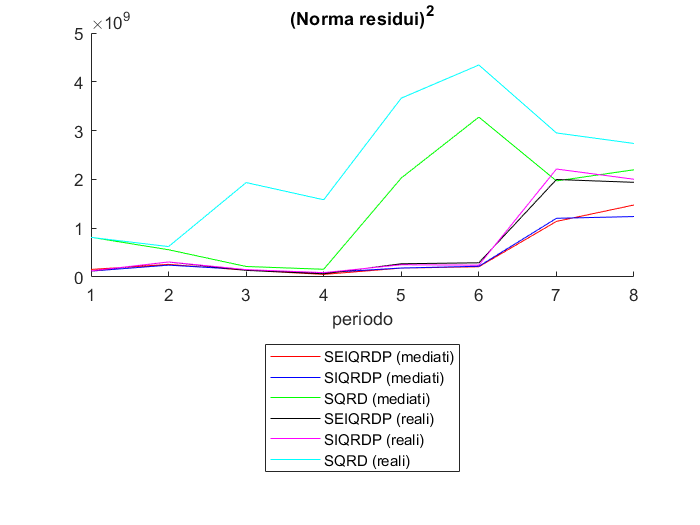

c={'r','b','g','k','m','c'};
figure
hold on
for i=1:6
    semilogy(1:8,err(:,i),c{i})
end
title('(Norma residui)^2')
xlabel('periodo')
leg={'SEIQRDP (mediati)','SIQRDP (mediati)','SQRD (mediati)','SEIQRDP (reali)','SIQRDP (reali)','SQRD (reali)'};
legend(leg{:},'Location','southoutside')
hold off

Per quantificare meglio l'errore, osserviamo ad esempio cosa è successo al Veneto nel periodo 5

format bank
tStart = datetime(2020,10,01);
tEnd = datetime(2020,11,03);
indT = find(time>=tStart & time <=tEnd);
table_erroriMedi_SEIQRDP_onNetwork{5}.('Media |residui| su Q')(1)

ans =         679.59


table_erroriMedi_SIQRDP_onNetwork{5}.('Media |residui| su Q')(1)

ans =         757.79


table_erroriMedi_SQRD_onNetwork{5}.('Media |residui| su Q')(1)

ans =        1992.34


[min(Q(indT,1)) mean(Q(indT,1)) max(Q(indT,1))] 

ans = 1×3
       2907.00      13033.79      36095.00


table_erroriMedi_SEIQRDP_onNetwork{5}.('Media |residui| su Qmedia')(1)

ans =         410.90


table_erroriMedi_SIQRDP_onNetwork{5}.('Media |residui| su Qmedia')(1)

ans =         424.82


table_erroriMedi_SQRD_onNetwork{5}.('Media |residui| su Qmedia')(1)

ans =        1717.76


[min(Qmedia(indT,1)) mean(Qmedia(indT,1)) max(Qmedia(indT,1))]

ans = 1×3
       2982.00      13171.85      36855.00


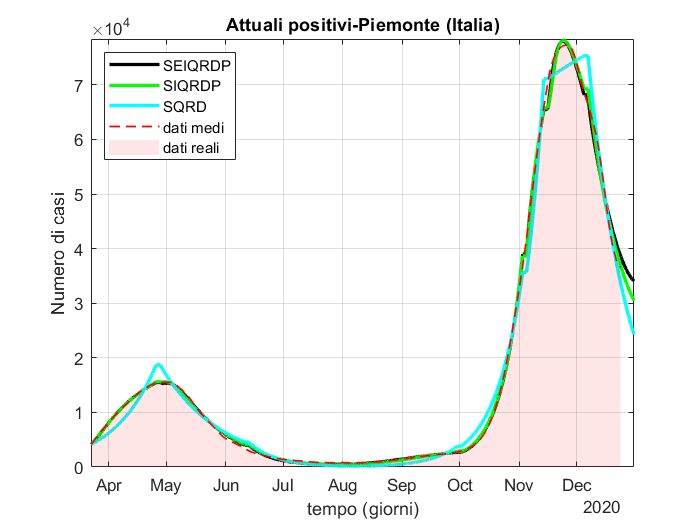

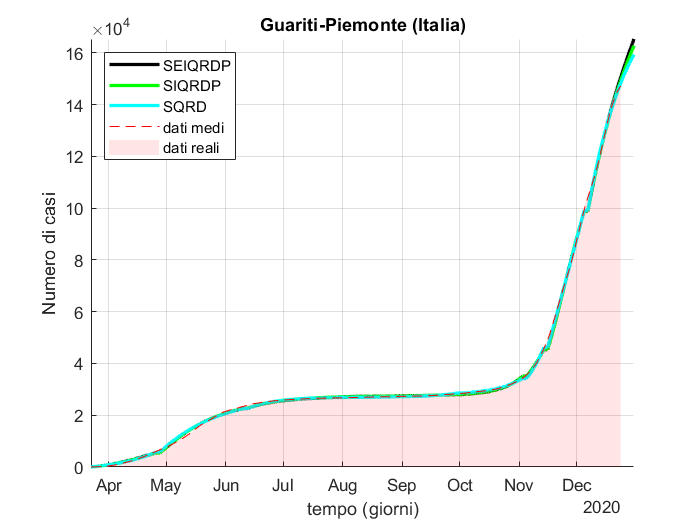

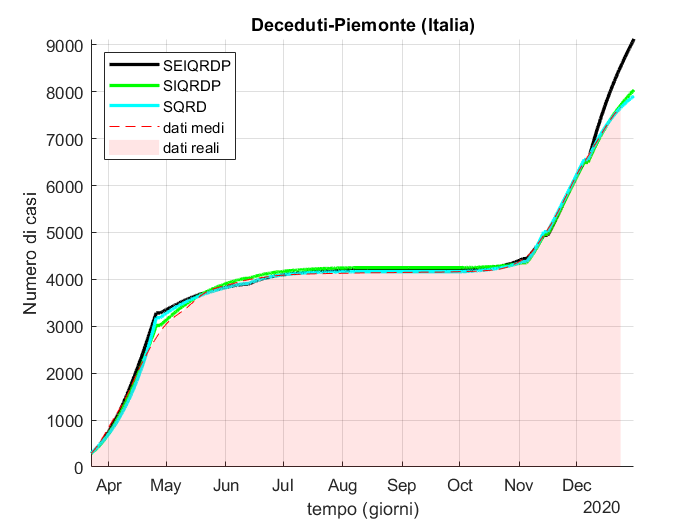

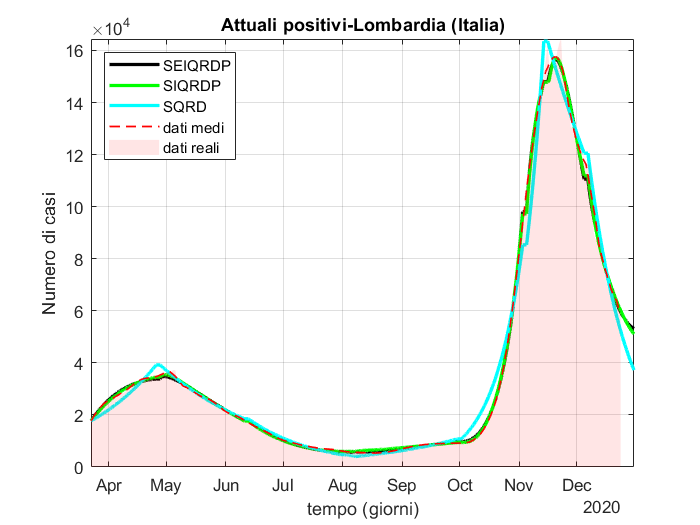

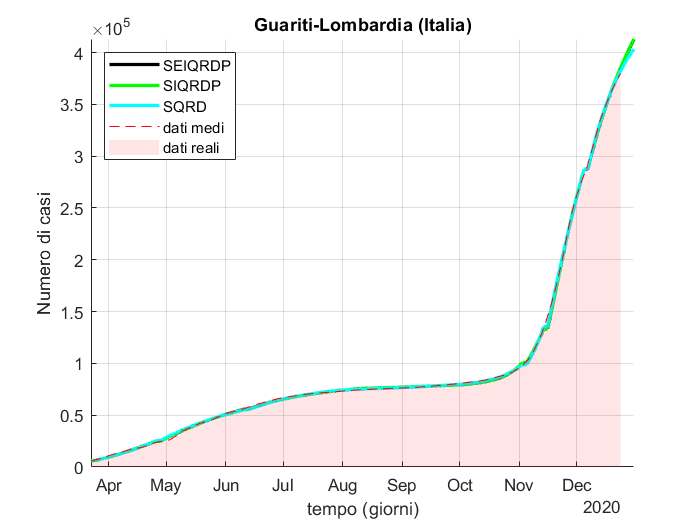

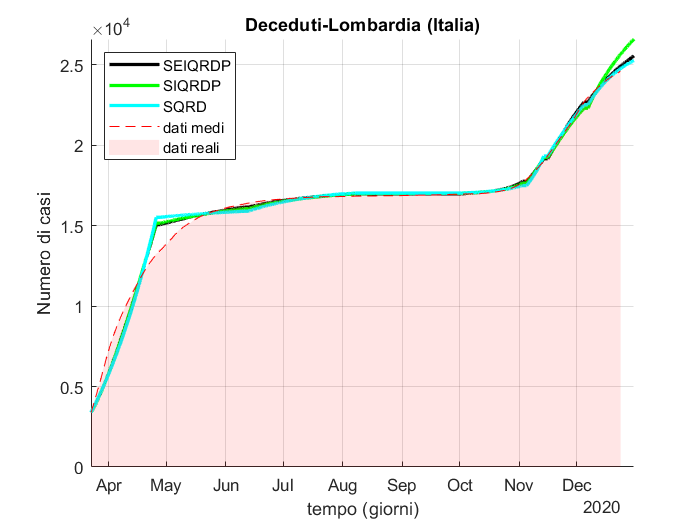

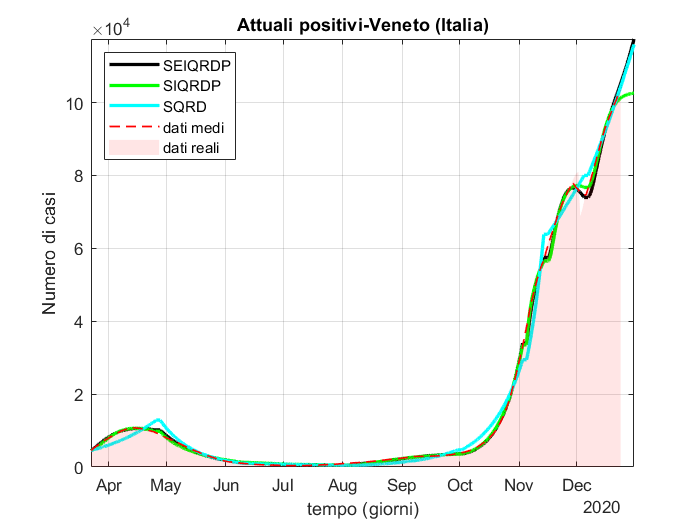

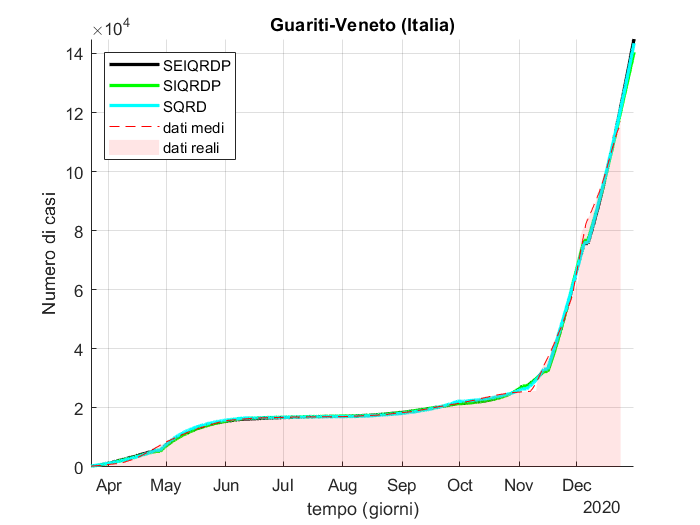


timeFitting=[];
tStart = datetime(2020,03,22);
tEnd = datetime(2020,04,26);
indT = find(time>=tStart & time <=tEnd);
temp=time(indT);
timeFitting=[timeFitting datetime(temp(1), 'Locale', 'en_US'):dt:datetime(temp(end), 'Locale', 'en_US')];

tStart = datetime(2020,04,27);
tEnd = datetime(2020,06,02);
indT = find(time>=tStart & time <=tEnd);
temp=time(indT);
timeFitting=[timeFitting datetime(temp(1), 'Locale', 'en_US'):dt:datetime(temp(end)+datenum(9), 'Locale', 'en_US')];

tStart = datetime(2020,06,12);
tEnd = datetime(2020,07,15);
indT = find(time>=tStart & time <=tEnd);
temp=time(indT);
timeFitting=[timeFitting datetime(temp(1), 'Locale', 'en_US'):dt:datetime(temp(end)+datenum(16), 'Locale', 'en_US')];

tStart = datetime(2020,08,01);
tEnd = datetime(2020,09,15);
indT = find(time>=tStart & time <=tEnd);
temp=time(indT);
timeFitting=[timeFitting datetime(temp(1), 'Locale', 'en_US'):dt:datetime(temp(end)+datenum(15), 'Locale', 'en_US')];

tStart = datetime(2020,10,01);
tEnd = datetime(2020,11,03);
indT = find(time>=tStart & time <=tEnd);
temp=time(indT);
timeFitting=[timeFitting datetime(temp(1), 'Locale', 'en_US'):dt:datetime(temp(end), 'Locale', 'en_US')];

tStart = datetime(2020,11,04);
tEnd = datetime(2020,11,14);
indT = find(time>=tStart & time <=tEnd);
temp=time(indT);
timeFitting=[timeFitting datetime(temp(1), 'Locale', 'en_US'):dt:datetime(temp(end), 'Locale', 'en_US')];

tStart = datetime(2020,11,15);
tEnd = datetime(2020,12,05);
indT = find(time>=tStart & time <=tEnd);
temp=time(indT);
timeFitting=[timeFitting datetime(temp(1), 'Locale', 'en_US'):dt:datetime(temp(end), 'Locale', 'en_US')];

tStart = datetime(2020,12,06);
tEnd = datetime(2020,12,23);
indT = find(time>=tStart & time <=tEnd);
temp=time(indT);
timeFitting=[timeFitting datetime(temp(1), 'Locale', 'en_US'):dt:datetime(temp(end)+datenum(8), 'Locale', 'en_US')];

for indR=1:6
    fitSEIQRDP=zeros(3,length(timeFitting));
    fitSIQRDP=zeros(3,length(timeFitting));
    fitSQRD=zeros(3,length(timeFitting));
    for i=5:7
        count=1;
        for indexPeriod=1:8
            l=length(squeeze(SEIQRDP{indexPeriod}.YM(i,indR,:)));
            fitSEIQRDP(i-4,count:count+l-1)=squeeze(SEIQRDP{indexPeriod}.YM(i,indR,:))';
            fitSIQRDP(i-4,count:count+l-1)=squeeze(SIQRDP{indexPeriod}.YM(i-1,indR,:))';
            fitSQRD(i-4,count:count+l-1)=squeeze(SQRD{indexPeriod}.YM(i-3,indR,:))';
            count=count+l;
        end
    end
    figure
    semilogy(timeFitting,fitSEIQRDP(1,:),'k','LineWidth',2);
    hold on
    semilogy(timeFitting,fitSIQRDP(1,:),'g','LineWidth',2);
    semilogy(timeFitting,fitSQRD(1,:),'c','LineWidth',2);
    set(gca,'ColorOrderIndex',1);
    semilogy(time(periodoAnalisi),Qmedia(periodoAnalisi,indR),'r--','LineWidth',1);
    a=area(time(periodoAnalisi),Q(periodoAnalisi,indR));
    a.FaceAlpha=0.1;
    a.FaceColor='r';
    a.EdgeColor='none';
    % ylim([0,1.1*Npop])
    ylabel('Numero di casi')
    xlabel('tempo (giorni)')
    title(['Attuali positivi-',regioni{indR},' (Italia)']);
    leg = {'SEIQRDP','SIQRDP','SQRD','dati medi','dati reali'};
    legend(leg{:},'location','northwest')
    set(gcf,'color','w')
    grid on
    axis tight
    set(gca,'yscale','lin')
    hold off
    figure
    hold on
    semilogy(timeFitting,fitSEIQRDP(2,:),'k','LineWidth',2);
    semilogy(timeFitting,fitSIQRDP(2,:),'g','LineWidth',2);
    semilogy(timeFitting,fitSQRD(2,:),'c','LineWidth',2);
    set(gca,'ColorOrderIndex',1);
    semilogy(time(periodoAnalisi),Rmedia(periodoAnalisi,indR),'r--');
    a=area(time(periodoAnalisi),R(periodoAnalisi,indR));
    a.FaceAlpha=0.1;
    a.FaceColor='r';
    a.EdgeColor='none';
    % ylim([0,1.1*Npop])
    ylabel('Numero di casi')
    xlabel('tempo (giorni)')
    title(['Guariti-',regioni{indR},' (Italia)']);
    leg = {'SEIQRDP','SIQRDP','SQRD','dati medi','dati reali'};
    legend(leg{:},'location','northwest')
    set(gcf,'color','w')
    grid on
    axis tight
    set(gca,'yscale','lin')
    hold off
    figure
    hold on
    semilogy(timeFitting,fitSEIQRDP(3,:),'k','LineWidth',2);
    semilogy(timeFitting,fitSIQRDP(3,:),'g','LineWidth',2);
    semilogy(timeFitting,fitSQRD(3,:),'c','LineWidth',2);
    set(gca,'ColorOrderIndex',1);
    semilogy(time(periodoAnalisi),Dmedia(periodoAnalisi,indR),'r--');
    a=area(time(periodoAnalisi),D(periodoAnalisi,indR));
    a.FaceAlpha=0.1;
    a.FaceColor='r';
    a.EdgeColor='none';
    % ylim([0,1.1*Npop])
    ylabel('Numero di casi')
    xlabel('tempo (giorni)')
    title(['Deceduti-',regioni{indR},' (Italia)']);
    leg = {'SEIQRDP','SIQRDP','SQRD','dati medi','dati reali'};
    legend(leg{:},'location','northwest')
    set(gcf,'color','w')
    grid on
    axis tight
    set(gca,'yscale','lin')
end

for indR=1:6
    for indexPeriod=1:8
        valmediEQ(indR,indexPeriod)=mean(squeeze(SEIQRDP{indexPeriod}.YM(3,indR,:))'./squeeze(SEIQRDP{indexPeriod}.YM(5,indR,:))');
        valmediIQ(indR,indexPeriod)=mean(squeeze(SEIQRDP{indexPeriod}.YM(4,indR,:))'./squeeze(SEIQRDP{indexPeriod}.YM(5,indR,:))');
        valmediPS(indR,indexPeriod)=mean(squeeze(SEIQRDP{indexPeriod}.YM(2,indR,:))'./squeeze(SEIQRDP{indexPeriod}.YM(1,indR,:))');
    end
end
format short
periodo = {'23-03 / 26-04','27-04 / 11-06','12-06 / 31-07','01-08 / 30-09','01-10 / 03-11','04-11 / 14-11','15-11 / 05-12','06-12 / 31-12'}';
cnames={'Periodo','Piemonte','Lombardia','Veneto','Emilia-Romagna','Marche','Toscana'};
rapportoPS =table(periodo,valmediPS(1,:)',valmediPS(2,:)',valmediPS(3,:)',valmediPS(4,:)',valmediPS(5,:)',valmediPS(6,:)','VariableNames',cnames)

rapportoPS = 8×7 table
         Periodo         Piemonte    Lombardia    Veneto     Emilia-Romagna    Marche     Toscana
    _________________    ________    _________    _______    ______________    _______    _______

    {'23-03 / 26-04'}    0.78879      0.91959      1.8626        1.3844         2.5819     1.2095
    {'27-04 / 11-06'}     30.981       2.6038      18.103       0.83665         69.035     99.431
    {'12-06 / 31-07'}     2.2477       1.9093      2.5627       0.18108           2.76      0.818
    {'01-08 / 30-09'}     2.0071      0.99292      3.5189        0.5866         5.9105     3.0213
    {'01-10 / 03-11'}    0.52057      0.53396      4.3178       0.30978         2.7576      1.643
    {'04-11 / 14-11'}    0.23964      0.69715       

rapportoEQ =table(periodo,valmediEQ(1,:)',valmediEQ(2,:)',valmediEQ(3,:)',valmediEQ(4,:)',valmediEQ(5,:)',valmediEQ(6,:)','VariableNames',cnames)

rapportoEQ = 8×7 table
         Periodo         Piemonte     Lombardia     Veneto      Emilia-Romagna    Marche     Toscana
    _________________    _________    _________    _________    ______________    _______    _______

    {'23-03 / 26-04'}      0.46072     0.57602       0.35922        0.36851       0.46722    0.43121
    {'27-04 / 11-06'}     0.026399     0.18152      0.060664        0.42031       0.27192    0.51718
    {'12-06 / 31-07'}      0.13816    0.023858       0.19476         2.1837        8.1956     7.8368
    {'01-08 / 30-09'}      0.20827    0.058453      0.016349         2.3688        2.8395     3.8601
    {'01-10 / 03-11'}     0.095199     0.21938     0.0090989         1.2785       0.46506    0.64312
    {'04-11 / 14-11'}      0.10

rapportoIQ =table(periodo,valmediIQ(1,:)',valmediIQ(2,:)',valmediIQ(3,:)',valmediIQ(4,:)',valmediIQ(5,:)',valmediIQ(6,:)','VariableNames',cnames)

rapportoIQ = 8×7 table
         Periodo         Piemonte    Lombardia     Veneto     Emilia-Romagna     Marche     Toscana 
    _________________    ________    _________    ________    ______________    ________    ________

    {'23-03 / 26-04'}     0.12511     0.10872     0.093703       0.084364        0.10346     0.12529
    {'27-04 / 11-06'}    0.030402    0.013078     0.031744       0.032558       0.017338    0.087141
    {'12-06 / 31-07'}     0.14512    0.019862      0.18155        0.16542        0.85639      1.4835
    {'01-08 / 30-09'}     0.15213     0.11945     0.070282        0.28951         1.2313      2.9609
    {'01-10 / 03-11'}     0.20989     0.40672      0.11341         1.6061         2.0389      1.4239
    {'04-11 / 14-11'}     0.106

% creazione tabelle
for indexPeriod=1:8
    par(indexPeriod,1,:)=tableSEIQRDP_onNetwork{indexPeriod}.beta;
    par(indexPeriod,2,:)=tableSEIQRDP_onNetwork{indexPeriod}.lambda;
    par(indexPeriod,3,:)=tableSEIQRDP_onNetwork{indexPeriod}.delta;
    par(indexPeriod,4,:)=tableSEIQRDP_onNetwork{indexPeriod}.gammaR;
    par(indexPeriod,5,:)=tableSEIQRDP_onNetwork{indexPeriod}.gammaD;
    par(indexPeriod,6,:)=tableSEIQRDP_onNetwork{indexPeriod}.alpha;
    par(indexPeriod,7,:)=tableSEIQRDP_onNetwork{indexPeriod}.omega;
    par(indexPeriod,8,:)=tableSIQRDP_onNetwork{indexPeriod}.beta;
    par(indexPeriod,9,:)=tableSIQRDP_onNetwork{indexPeriod}.delta;
    par(indexPeriod,10,:)=tableSIQRDP_onNetwork{indexPeriod}.gammaR;
    par(indexPeriod,11,:)=tableSIQRDP_onNetwork{indexPeriod}.gammaD;
    par(indexPeriod,12,:)=tableSIQRDP_onNetwork{indexPeriod}.alpha;
    par(indexPeriod,13,:)=tableSIQRDP_onNetwork{indexPeriod}.omega;
    par(indexPeriod,14,:)=tableSQRD_onNetwork{indexPeriod}.beta;
    par(indexPeriod,15,:)=tableSQRD_onNetwork{indexPeriod}.gammaR;
    par(indexPeriod,16,:)=tableSQRD_onNetwork{indexPeriod}.gammaD;
end

for indexPeriod=2:8
    parE(indexPeriod-1,1)=SEIQRDP_onNetwork{indexPeriod}.parametriM(43);
    parE(indexPeriod-1,2)=SEIQRDP_onNetwork{indexPeriod}.parametriM(44);
    parE(indexPeriod-1,3)=SIQRDP_onNetwork{indexPeriod}.parametriM(37);
    parE(indexPeriod-1,4)=SIQRDP_onNetwork{indexPeriod}.parametriM(38);
    parE(indexPeriod-1,5)=SQRD_onNetwork{indexPeriod}.parametriM(19);
end

Alcune osservazioni sulla conservazione della popolazione finale:

format bank
vett=[sum(SEIQRDP{8}.YM(:,1,end)) sum(SEIQRDP{8}.YM(:,2,end)) sum(SEIQRDP{8}.YM(:,3,end)) sum(SEIQRDP{8}.YM(:,4,end)) sum(SEIQRDP{8}.YM(:,5,end)) sum(SEIQRDP{8}.YM(:,6,end))]

vett = 1×6
    3049620.50    9283902.65    6213908.27    4438898.00    1581397.18    4320273.39


popolazione

popolazione = 1×6
    4311000.00   10028000.00    4879000.00    4464000.00    1513000.00    3693000.00


sum(vett)

ans =    28888000.00


sum(popolazione)

ans =    28888000.00
